%% code for data visual
dirname1 = "/MATLAB Drive/EMGPhysicalActionDataSet/sub*";
dirname2="/MATLAB Drive/EMGPhysicalActionDataSet";

subject = dir(dirname1)

subject = 4×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


L1 = length(subject);
subjectlen = sprintf('Directories Count:%d',L1);
disp(subjectlen);

Directories Count:4


data1=signalDatastore(fullfile(dirname2,'/',subject(1).name,'/','/Aggressive/txt'));
data2=signalDatastore(fullfile(dirname2,'/',subject(1).name,'/','/Normal/txt'));
p1 = endsWith(data1.Files,".mat");
p2 = endsWith(data2.Files,".mat");
sdssig1 = subset(data1,p1);
sdssig2 = subset(data2,p2);
signal=data1.preview

signal =         -245         266        2615         -29       -4000        -549       -4000        4000
        -814         391         -22        -277       -4000        -130       -4000        4000
        -445         257       -3628        -428       -4000          97       -4000        4000
        -844         201       -4000        -498       -4000          62       -4000        4000
       -1996         233       -4000        -552       -4000         109       -4000        4000
       -3300         196       -4000        -538       -4000         185       -1989        4000
       -2838         294       -4000        -505        -918         205        -393        4000
       -1300         355       -4000        -438        3020         118        -542        4000
        -143         378       -1101        -397        4000          24        -538        4000
         717         252         528        -262        4000          17        1084        4000


signa2=data2.preview

signa2 =           62         -21         -11          32         418        -255         508         320
         -52        -637          11          46         293         -84         637         434
          73        -545           8          16         248         128         807         825
          71        -666         -39          95         209         235         807         701
         -29          20         -47         126         199         292         807         377
          53         566         -57          17         237         368         727         145
          44         339         -93        -160         391         376         659        -521
         -85         526         -49        -319         627         274         663        -818
        -190         -35         -30        -319         831         154         628        -858
        -170        -452          -7           4         941         100         555       -1055


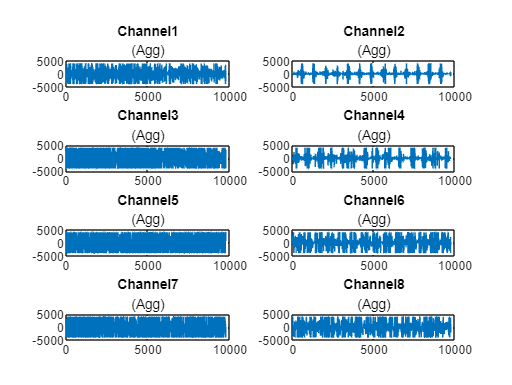

for i = 1:8
    ax(i)= subplot(4,2,i);
    plot(signal(:,i));
    title("Channel"+i,"(Agg)");
end

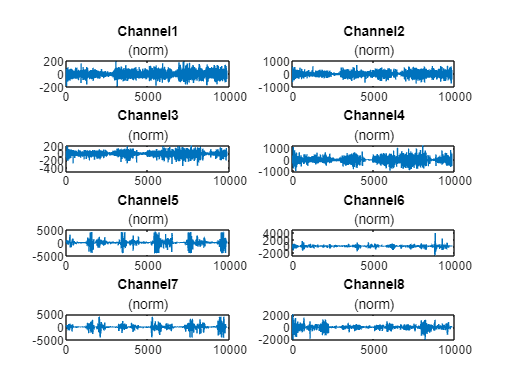

 figure
% linkaxes(ax,"y")
for i = 1:8
    ax2(i)= subplot(4,2,i);
    plot(signa2(:,i));
    title("Channel"+i,"(norm)");
end

 figure
% linkaxes(ax2,"y")
 finaldata=[];
 finaltarget=[];
 

%%Emg feature extraction 
 for j=1:4
      normal= dir(fullfile(dirname2,'/',subject(j).name,'/','/Normal/txt/*.txt'));
      aggressive= dir(fullfile(dirname2,'/',subject(j).name,'/','/Aggressive/txt/*.txt'));
       files=table(normal, aggressive);
       N=length(files.aggressive);
      disp(subject(j).name);
      files = table2array(files);
      
      
% code to convert all text files into matfiles and store in same folder
%    for i=1:N
%       x=files(i).name;
%       Data=importdata(fullfile("C:\Users\VIKAS CHEIIURU\MATLAB Drive\EMGPhysicalActionDataSet\sub1\Normal\txt",'\',files(i).name));
%        [a, b ,c] =fileparts(x);
%        save(b,"Data");
%    end
         vikas1=[];
         vikas2=[];
         targ1=[];
         targ2=[];
          
 
     for i=1:10
        x1 = importdata(fullfile(dirname2,'/',subject(j).name,'/','/Aggressive/txt/','/',files(i,2).name));
        x2 = importdata(fullfile(dirname2,'/',subject(j).name,'/','/Normal/txt/','/',files(i,1).name));
        [R1,C1] = size(x1);
        [R2,C2]= size(x2);
            size_data1 = sprintf('Rows:%d, Cols:%d',R1,C1);
            disp(files(i,2).name);
            disp(size_data1);
%%to plot eight channels of every activity from both aggressive and normal    
%             for cx1 = 1:C1
%                 subplot(4,2,cx1);
%                 plot(x1(:,cx1));
%                 xlabel('index');
%                 ylabel('sEMG');
%                 tl_str = sprintf('Chan.no.:%d',cx1);
%                 title(tl_str);
%             end
%             figure
%             size_data2 = sprintf('Rows:%d, Cols:%d',R2,C2);
%             disp(files(i,1).name);
%             disp(size_data2);
%             for cx2 = 1:C2
%                 subplot(4,2,cx2);
%                 plot(x1(:,cx2));
%                 xlabel('index');
%                 ylabel('sEMG');
%                 tl_str = sprintf('Chan.no.:%d',cx2);
%                 title(tl_str);
%             end
%             figure

           numtrails=15;
          traillen1=floor(R1/numtrails);
          segmlength1=floor(traillen1/3);
          L1=floor(R1/segmlength1);
           traillen2=floor(R2/numtrails);
          segmlength2=floor(traillen2/3);
          L2=floor(R2/segmlength2);
             dummy11=[];
             dummy12=[];
             dummy13=[];
             dummy14=[];
             dummyf11=[];
             dummyf12=[];
             dummyf13=[];
             dummyf14=[];
             data1=[];
             dummy23=[];
             dummy22=[];
             dummy21=[];
             dummy24=[];
             dummyf21=[];
             dummyf22=[];
             dummyf23=[];
             dummyf24=[];
             data2=[];
                for n=1:8
                 [n1 ,n2]  =size(x1(:,n));
                 b1= floor(n1/45);
                  dft=[];
                  for k=0:44
                    ftx1=fft(x1(k*b1+1:(k+1)*b1,n));
                    dft=[dft;ftx1];
                  end
                    dft;
                         
                     sFEm1 = signalTimeFeatureExtractor(FrameSize=b1,FrameOverlapLength=0,Mean=true);
                     mean1=extract(sFEm1,x1(:,n));
                     sFEfm1 = signalTimeFeatureExtractor(FrameSize=b1,FrameOverlapLength=0,Mean=true);
                     fmean1=abs(extract(sFEfm1,dft));
                     sFEfp1 = signalTimeFeatureExtractor(FrameSize=b1,FrameOverlapLength=0,peak=true);
                     fpeak1=abs(extract(sFEfp1,dft));
                    sFEfv1 = signalTimeFeatureExtractor(FrameSize=b1,FrameOverlapLength=0,standardDeviation=true);
                     fvar1=abs(extract(sFEfv1,dft));
                     fvar1=fvar1.^2;
                      sFEv1 = signalTimeFeatureExtractor(FrameSize=b1,FrameOverlapLength=0,StandardDeviation=true);
                      var1=extract(sFEv1,x1(:,n));
%                    
                      var1=var1.^2;
                      sFEp1 = signalTimeFeatureExtractor(FrameSize=b1,FrameOverlapLength=0,peak=true);
                      peak1=extract(sFEp1,x1(:,n));
           
                   sFEmf1 = signalTimeFeatureExtractor(FrameSize=b1,FrameOverlapLength=0,ShapeFactor=true);
                   mf2=extract(sFEmf1,x1(:,n));
                    sFEmff1 = signalTimeFeatureExtractor(FrameSize=b1,FrameOverlapLength=0,ShapeFactor=true);
                   mff2=abs(extract(sFEmff1,dft));
  
                   finalmean1=reshape(mean1 ,[3 L1/3])';
                      dummy11= [dummy11 finalmean1];
                    finalfmean1=reshape(fmean1 ,[3 L1/3])';
                    finalfvar1=reshape(fvar1 ,[3 L1/3])';
                      dummyf11= [dummyf11 finalfmean1];
                      dummyf13= [dummyf13 finalfvar1];
                   finalpeak1=reshape(peak1,[3 L1/3])';
                   finalfpeak1=reshape(fpeak1,[3 L1/3])';
                    dummyf12=[dummyf12 finalpeak1];
                    dummy12= [dummy12 finalpeak1];
                   finalvar1=reshape(var1,[3 L1/3])';
                    dummy13= [ dummy13 finalvar1];
                    finalmf1=reshape(mf2,[3 L1/3])';
                    dummy14= [ dummy14 finalmf1];    
                    finalmff1=reshape(mff2,[3 L1/3])';
                    dummyf14= [ dummyf14 finalmff1];
                       
                end
                 data1=[dummy11 dummy13 dummy12 dummy14 dummyf11 dummyf12 dummyf13 dummyf14];
                 target1=repmat( i, [1,15] )';
                 targ1=[targ1;target1];
                 vikas1=[vikas1; data1];


                for k=1:8
                     [n3 ,n4]  =size(x2(:,n));
                      b2= floor(n3/45);

                      dft2=[];
                  for l1=0:44
                    ftx2=fft(x2(l1*b2+1:(l1+1)*b2,k));
                    dft2=[dft2;ftx2];
                  end
                    dft2;
                        
                     sFEm2 = signalTimeFeatureExtractor(FrameSize=b2,FrameOverlapLength=0,Mean=true);
                     mean2=extract(sFEm2,x2(:,k));
              
                     sFEfm2 = signalTimeFeatureExtractor(FrameSize=b2,FrameOverlapLength=0,Mean=true);
                     fmean2=abs(extract(sFEfm2,dft2));
                     sFEfp2 = signalTimeFeatureExtractor(FrameSize=b2,FrameOverlapLength=0,peak=true);
                     fpeak2=abs(extract(sFEfp2,dft2));
                      sFEfv2 = signalTimeFeatureExtractor(FrameSize=b2,FrameOverlapLength=0,StandardDeviation=true);
                     fvar2=abs(extract(sFEfv2,dft2));
                      fvar2=fvar2.^2;
                     sFEv2 = signalTimeFeatureExtractor(FrameSize=b2,FrameOverlapLength=0,StandardDeviation=true);
                     var2=extract(sFEv2,x2(:,k));
                  
                       [q2 w2] =size(var2);                         
                          var2=var2.^2;
                      sFEp2 = signalTimeFeatureExtractor(FrameSize=b2,FrameOverlapLength=0,peak=true);
                      peak2=extract(sFEp2,x2(:,n));
                       [q3 w3]=size(peak2);

                     finalmf2=reshape(mf2,[3 L2/3])';
                     dummy24= [ dummy24 finalmf2];
                     finalmff2=reshape(mff2,[3 L2/3])';
                      dummyf24= [ dummyf24 finalmff2];
                      finalfvar2=reshape(fvar2 ,[3 L2/3])';
                      dummyf23= [dummyf23 finalfvar2];
                     
                      finalfmean2=reshape(fmean2 ,[3 L2/3])';
                      dummyf21= [dummyf21 finalfmean2];
                      finalfpeak2=reshape(fpeak2 ,[3 L2/3])';
                      dummyf22= [dummyf22 finalfpeak2];
                     finalpeak2=reshape(peak2,[3 L2/3])';
                      dummy22= [dummy22 finalpeak2];
                     finalmean2=reshape(mean2 ,[3 L2/3])';
                     dummy21= [dummy21 finalmean2];
                     finalvar2=reshape(var2,[3 L2/3])';
                     dummy23= [ dummy23 finalvar2];


                end
                data2=[dummy21 dummy23 dummy22 dummy24 dummyf21 dummyf22 dummyf23 dummyf24];
                target2=repmat( 10+i, [1,15] )';
                targ2=[targ2;target2];
                vikas2=[vikas2; data2];

     end

      targetdataset=[targ1;targ2];
      DATA=[vikas1;vikas2];
      finaldata=[finaldata;DATA];
     finaltarget=[finaltarget;targetdataset];

    
end

sub1


Elbowing.txt


Rows:9772, Cols:8


n1 = 9772

n2 = 1

b1 = 217

fmean1 = 1.0e+03 *

    0.2450
    0.2870
    0.1860
    4.0000
    4.0000
    0.3940
    0.2370
    4.0000
    0.1190
    0.7790


fpeak1 = 1.0e+05 *

    0.8623
    1.0750
    1.2049
    0.8772
    1.2050
    0.7964
    1.7426
    0.9427
    1.5799
    0.9143


fvar1 = 1.0e+04 *

    2.3619
    2.7132
    3.2187
    2.5907
    2.6763
    2.3224
    3.0852
    2.4413
    3.3529
    2.6770


var1 = 1.0e+03 *

    1.6031
    1.8352
    2.1753
    1.7788
    1.8356
    1.5758
    2.0938
    1.6794
    2.2664
    1.8173


dummyf12 =         4000        4000        4000
        4000        4000        4000
        4000        4000        4000
        4000        4000        4000
        4000        4000        4000
        4000        4000        4000
        4000        4000        4000
        4000        4000        4000
        4000        4000        4000
        3478        4000        4000


n1 = 9772

n2 = 1

b1 = 217

fmean1 = 1.0e+03 *

    0.2660
    0.4770
    0.3400
    0.0300
    0.2020
    0.3450
    3.0060
    0.5490
    0.2270
    0.3550


fpeak1 = 1.0e+05 *

    0.2009
    0.7918
    1.0422
    0.3342
    0.1234
    0.4344
    0.9408
    0.1276
    0.1934
    0.6956


fvar1 = 1.0e+04 *

    0.3828
    1.0193
    2.5624
    0.7668
    0.3275
    1.3655
    2.0843
    0.3713
    0.4660
    1.7627


var1 = 1.0e+03 *

    0.2602
    0.6919
    1.7385
    0.5164
    0.2212
    0.9267
    1.4295
    0.2543
    0.3166
    1.1919


dummyf12 =         4000        4000        4000         811        1611        4000
        4000        4000        4000        1702         598        4000
        4000        4000        4000        4000         825        1051
        4000        4000        4000        4000        1445        1583
        4000        4000        4000        4000        1114        2241
        4000        4000        4000        4000        3127         786
        4000        4000        4000        3733        4000         657
        4000        4000        4000         591        4000        1529
        4000        4000        4000         719        3396        4000
        3478        4000        4000         733        2800        3940


n1 = 9772

n2 = 1

b1 = 217

fmean1 = 1.0e+03 *

    2.6150
    4.0000
    4.0000
    1.5570
    2.0390
    3.2570
    4.0000
    2.5510
    3.9670
    1.1140


fpeak1 = 1.0e+05 *

    1.6099
    1.9418
    1.1468
    1.3197
    2.2044
    1.6680
    1.3222
    2.0272
    1.5810
    1.8658


fvar1 = 1.0e+04 *

    4.6529
    4.5499
    4.1017
    3.2010
    4.6893
    4.2098
    3.4635
    4.3643
    4.2885
    4.0757


var1 = 1.0e+03 *

    3.1630
    3.0929
    2.7887
    2.1755
    3.1423
    2.8644
    2.3659
    2.9658
    2.9219
    2.7643


dummyf12 =         4000        4000        4000         811        1611        4000        4000        4000        4000
        4000        4000        4000        1702         598        4000        4000        4000        4000
        4000        4000        4000        4000         825        1051        4000        4000        4000
        4000        4000        4000        4000        1445        1583        4000        4000        4000
        4000        4000        4000        4000        1114        2241        4000        4000        4000
        4000        4000        4000        4000        3127         786        4000        4000        4000
        4000        4000        4000        3733        4000         657        4000        4000        4000
        4000        4000        4000         591        4000        1529        4000        4000        4000
        4000        4000        4000         719        3396        4000        4000        4000        4000
        

n1 = 9772

n2 = 1

b1 = 217

fmean1 = 1.0e+03 *

    0.0290
    1.0930
    0.3830
    0.2620
    0.4310
    0.3230
    0.2900
    1.3020
    4.0000
    0.2890


fpeak1 = 1.0e+05 *

    0.6531
    1.1075
    0.2707
    1.1651
    2.5688
    0.4034
    0.4213
    1.3969
    1.8158
    0.2527


fvar1 = 1.0e+04 *

    1.5113
    2.7396
    0.5859
    1.8048
    4.2888
    0.7138
    1.1042
    3.2796
    3.5264
    0.4276


var1 = 1.0e+03 *

    1.0243
    1.8613
    0.3977
    1.2252
    2.9089
    0.4841
    0.7390
    2.2279
    2.4092
    0.2909


dummyf12 =         4000        4000        4000         811        1611        4000        4000        4000        4000        4000        4000        1028
        4000        4000        4000        1702         598        4000        4000        4000        4000        4000        4000        1444
        4000        4000        4000        4000         825        1051        4000        4000        4000        3445        4000        4000
        4000        4000        4000        4000        1445        1583        4000        4000        4000         785        4000        4000
        4000        4000        4000        4000        1114        2241        4000        4000        4000        2147        2248        4000
        4000        4000        4000        4000        3127         786        4000        4000        4000        4000        4000        4000
        4000        4000        4000        3733        4000         657        4000        4000        4000        169

n1 = 9772

n2 = 1

b1 = 217

fmean1 = 1.0e+03 *

    4.0000
    4.0000
    2.9710
    0.0910
    4.0000
    0.1030
    0.6610
    0.9530
    4.0000
    4.0000


fpeak1 = 1.0e+05 *

    3.2878
    2.7467
    3.5878
    2.2417
    2.5386
    2.6126
    2.0321
    2.8187
    2.5475
    2.7041


fvar1 = 1.0e+04 *

    5.1738
    5.1065
    4.6872
    4.5371
    4.7491
    4.9452
    3.6155
    5.2186
    5.2177
    4.2171


var1 = 1.0e+03 *

    3.5127
    3.4768
    3.0878
    3.0795
    3.2264
    3.3000
    2.4395
    3.5312
    3.5477
    2.8312


dummyf12 =         4000        4000        4000         811        1611        4000        4000        4000        4000        4000        4000        1028        4000        4000        4000
        4000        4000        4000        1702         598        4000        4000        4000        4000        4000        4000        1444        4000        4000        4000
        4000        4000        4000        4000         825        1051        4000        4000        4000        3445        4000        4000        4000        4000        4000
        4000        4000        4000        4000        1445        1583        4000        4000        4000         785        4000        4000        4000        4000        4000
        4000        4000        4000        4000        1114        2241        4000        4000        4000        2147        2248        4000        4000        4000        4000
        4000        4000        4000        4000        3127         786        4000

n1 = 9772

n2 = 1

b1 = 217

fmean1 = 1.0e+03 *

    0.5490
    3.6650
    3.6090
    0.6800
    0.0180
    0.8840
    0.1150
    3.4090
    4.0000
    0.2760


fpeak1 = 1.0e+05 *

    1.8414
    1.8118
    1.4201
    2.2487
    1.3555
    0.5862
    1.7539
    1.3546
    1.2488
    1.4635


fvar1 = 1.0e+04 *

    2.8633
    3.1526
    2.2943
    3.5853
    3.0014
    1.5060
    3.4488
    2.8629
    2.8077
    2.3962


var1 = 1.0e+03 *

    1.9246
    2.1512
    1.5714
    2.4314
    2.0369
    1.0241
    2.1966
    1.9530
    1.9214
    1.6131


dummyf12 =         4000        4000        4000         811        1611        4000        4000        4000        4000        4000        4000        1028        4000        4000        4000        4000        4000        4000
        4000        4000        4000        1702         598        4000        4000        4000        4000        4000        4000        1444        4000        4000        4000        4000        4000        4000
        4000        4000        4000        4000         825        1051        4000        4000        4000        3445        4000        4000        4000        4000        4000        4000        4000        4000
        4000        4000        4000        4000        1445        1583        4000        4000        4000         785        4000        4000        4000        4000        4000        4000        4000        4000
        4000        4000        4000        4000        1114        2241        4000        4000        4000        2147 

n1 = 9772

n2 = 1

b1 = 217

fmean1 = 1.0e+03 *

    4.0000
    4.0000
    3.0860
    4.0000
    4.0000
    4.0000
    4.0000
    1.1610
    4.0000
    2.4060


fpeak1 = 1.0e+05 *

    3.0900
    2.9074
    3.3558
    2.7355
    3.0665
    3.1960
    4.0014
    3.2253
    2.1108
    2.9344


fvar1 = 1.0e+04 *

    5.0800
    4.4398
    5.2715
    4.7651
    5.0619
    4.7102
    5.0893
    5.0450
    3.9792
    4.9406


var1 = 1.0e+03 *

    3.4211
    2.9955
    3.5759
    3.1998
    3.3984
    3.2088
    3.4039
    3.3843
    2.7149
    3.3574


dummyf12 =         4000        4000        4000         811        1611        4000        4000        4000        4000        4000        4000        1028        4000        4000        4000        4000        4000        4000        4000        4000        4000
        4000        4000        4000        1702         598        4000        4000        4000        4000        4000        4000        1444        4000        4000        4000        4000        4000        4000        4000        4000        4000
        4000        4000        4000        4000         825        1051        4000        4000        4000        3445        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
        4000        4000        4000        4000        1445        1583        4000        4000        4000         785        4000        4000        4000        4000        4000        4000        4000        4000        4000  

n1 = 9772

n2 = 1

b1 = 217

fmean1 = 1.0e+03 *

    4.0000
    1.8990
    3.9790
    0.8920
    0.1120
    2.4620
    4.0000
    1.1030
    4.0000
    1.3630


fpeak1 = 1.0e+05 *

    2.2743
    2.2353
    2.4734
    1.4794
    1.5867
    2.4656
    2.9295
    1.5281
    2.4086
    1.5811


fvar1 = 1.0e+04 *

    2.9707
    4.1960
    4.0699
    2.6876
    2.6408
    3.8053
    3.9736
    2.3108
    3.7132
    3.3539


var1 = 1.0e+03 *

    2.0304
    2.8469
    2.7583
    1.8217
    1.7882
    2.5448
    2.7106
    1.5704
    2.5349
    2.2765


dummyf12 =         4000        4000        4000         811        1611        4000        4000        4000        4000        4000        4000        1028        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
        4000        4000        4000        1702         598        4000        4000        4000        4000        4000        4000        1444        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
        4000        4000        4000        4000         825        1051        4000        4000        4000        3445        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
        4000        4000        4000        4000        1445        1583        4000        4000        4000         785  

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

Frontkicking.txt


Rows:9811, Cols:8


n1 = 9811

n2 = 1

b1 = 218

fmean1 =   325.0000
  167.0000
  134.0000
   69.0000
  345.0000
    2.0000
  275.0000
  473.0000
  639.0000
    4.0000


fpeak1 = 1.0e+05 *

    0.4565
    0.2253
    0.2650
    0.1771
    0.3479
    0.2081
    0.6090
    0.2182
    0.2917
    0.3710


fvar1 = 1.0e+04 *

    1.0820
    0.6059
    0.6952
    0.5348
    0.8430
    0.5478
    1.6604
    0.4994
    0.6927
    0.9368


var1 = 1.0e+03 *

    0.7331
    0.4105
    0.4704
    0.3621
    0.5712
    0.3710
    1.1246
    0.3366
    0.4711
    0.6345


dummyf12 =         2471        1735        1767
        1384        2085        1325
        4000        1158        1628
        2093        1528        2536
        1455        1124         889
         518        1352        2772
        1572        2549        1038
         971        1948        1479
        1130         477         850
         635        3200         571


n1 = 9811

n2 = 1

b1 = 218

fmean1 = 1.0e+03 *

    0.1080
    0.2840
    0.2180
    1.2530
    1.5750
    0.5000
    0.2420
    0.1430
    0.0960
    0.4770


fpeak1 = 1.0e+04 *

    1.6459
    1.5790
    3.2178
    4.8242
    4.4065
    2.6171
    3.1532
    2.4433
    5.0127
    9.4065


fvar1 = 45×1
1.0e+04 *

    0.3010
    0.4273
    0.7953
    1.3455
    1.3006
    0.7375
    0.7845
    0.6557
    1.2716
    1.6988


var1 = 45×1
1.0e+03 *

    0.2030
    0.2900
    0.5389
    0.9152
    0.8874
    0.5006
    0.5314
    0.4440
    0.8612
    1.1504


dummyf12 = 15×6
        2471        1735        1767         521         995        1813
        1384        2085        1325        3343        4000        2045
        4000        1158        1628        2039        1475        3815
        2093        1528        2536        4000        1281        1871
        1455        1124         889         882        1367        4000
         518        1352        2772        1132        1578         990
        1572        2549        1038        1143        1285        2406
         971        1948        1479        4000        1285         567
        1130         477         850         800        4000        1513
         635        3200         571        2033         632         681


n1 = 9811

n2 = 1

b1 = 218

fmean1 = 45×1
1.0e+03 *

    0.5330
    0.2070
    0.0850
    1.0310
    0.0160
    0.0700
    0.3070
    0.8400
    0.9080
    2.3030


fpeak1 = 45×1
1.0e+05 *

    1.3089
    0.3799
    1.2188
    0.8017
    0.5727
    0.2005
    0.3134
    0.4227
    0.5685
    1.0119


fvar1 = 45×1
1.0e+04 *

    2.9497
    0.8961
    2.2335
    2.2000
    1.3166
    0.5919
    0.8639
    1.1911
    1.2732
    2.3026


var1 = 45×1
1.0e+03 *

    1.9980
    0.6070
    1.5126
    1.4915
    0.8913
    0.4008
    0.5854
    0.8087
    0.8635
    1.5673


dummyf12 = 15×9
        2471        1735        1767         521         995        1813        4000        2667        4000
        1384        2085        1325        3343        4000        2045        4000        4000        1568
        4000        1158        1628        2039        1475        3815        1900        2819        3628
        2093        1528        2536        4000        1281        1871        4000        1703        3767
        1455        1124         889         882        1367        4000        4000        4000        4000
         518        1352        2772        1132        1578         990        3295        2240        4000
        1572        2549        1038        1143        1285        2406        2864        4000        4000
         971        1948        1479        4000        1285         567        1550        1518        4000
        1130         477         850         800        4000        1513        4000        4000        4000
   

n1 = 9811

n2 = 1

b1 = 218

fmean1 = 45×1
1.0e+03 *

    0.2100
    0.2480
    0.0220
    0.0660
    0.6140
    0.2280
    0.4670
    3.9340
    2.2700
    0.7840


fpeak1 = 45×1
1.0e+05 *

    0.2637
    0.9321
    0.4364
    0.7267
    0.2686
    0.7579
    0.7588
    0.6021
    0.6891
    0.4641


fvar1 = 45×1
1.0e+04 *

    0.7209
    2.2278
    1.1333
    1.5226
    0.7656
    2.1116
    2.1100
    2.1197
    2.3677
    0.9737


var1 = 45×1
1.0e+03 *

    0.4884
    1.5086
    0.7671
    1.0312
    0.5189
    1.4301
    1.4289
    1.4603
    1.6105
    0.6608


dummyf12 = 15×12
        2471        1735        1767         521         995        1813        4000        2667        4000        2135        4000        3006
        1384        2085        1325        3343        4000        2045        4000        4000        1568        4000        1819        4000
        4000        1158        1628        2039        1475        3815        1900        2819        3628        4000        4000        4000
        2093        1528        2536        4000        1281        1871        4000        1703        3767        3301        2460        2446
        1455        1124         889         882        1367        4000        4000        4000        4000        4000        3185         790
         518        1352        2772        1132        1578         990        3295        2240        4000        1614        2065        1288
        1572        2549        1038        1143        1285        2406        2864        4000        4000     

n1 = 9811

n2 = 1

b1 = 218

fmean1 = 45×1
1.0e+03 *

    3.5540
    4.0000
    4.0000
    4.0000
    4.0000
    4.0000
    4.0000
    4.0000
    0.7070
    2.6150


fpeak1 = 45×1
1.0e+05 *

    2.4033
    4.0225
    2.1783
    2.7651
    3.0924
    2.3739
    3.6005
    2.7759
    1.8450
    3.0204


fvar1 = 45×1
1.0e+04 *

    5.5026
    5.4050
    4.2067
    5.5200
    5.5075
    4.4244
    5.6850
    4.9294
    3.6956
    5.4829


var1 = 45×1
1.0e+03 *

    3.6795
    3.6557
    2.8619
    3.7326
    3.7071
    2.9944
    3.8477
    3.3077
    2.4962
    3.6554


dummyf12 = 15×15
        2471        1735        1767         521         995        1813        4000        2667        4000        2135        4000        3006        4000        4000        4000
        1384        2085        1325        3343        4000        2045        4000        4000        1568        4000        1819        4000        4000        4000        4000
        4000        1158        1628        2039        1475        3815        1900        2819        3628        4000        4000        4000        4000        4000        4000
        2093        1528        2536        4000        1281        1871        4000        1703        3767        3301        2460        2446        4000        4000        4000
        1455        1124         889         882        1367        4000        4000        4000        4000        4000        3185         790        4000        4000        4000
         518        1352        2772        1132        1578         990      

n1 = 9811

n2 = 1

b1 = 218

fmean1 = 45×1
1.0e+03 *

    0.5610
    4.0000
    3.3490
    1.5150
    4.0000
    0.8670
    0.1040
    4.0000
    1.9160
    0.0660


fpeak1 = 45×1
1.0e+05 *

    2.6001
    3.1828
    2.8152
    2.7599
    2.8163
    1.1363
    2.6148
    2.9542
    2.0963
    2.2104


fvar1 = 45×1
1.0e+04 *

    4.9571
    5.0230
    4.6254
    4.9494
    4.3152
    2.6459
    5.4517
    5.0135
    4.6058
    4.0346


var1 = 45×1
1.0e+03 *

    3.3491
    3.4011
    3.1325
    3.3015
    2.8063
    1.7903
    3.6438
    3.4036
    3.0923
    2.6868


dummyf12 = 15×18
        2471        1735        1767         521         995        1813        4000        2667        4000        2135        4000        3006        4000        4000        4000        4000        4000        4000
        1384        2085        1325        3343        4000        2045        4000        4000        1568        4000        1819        4000        4000        4000        4000        4000        4000        4000
        4000        1158        1628        2039        1475        3815        1900        2819        3628        4000        4000        4000        4000        4000        4000        4000        4000        4000
        2093        1528        2536        4000        1281        1871        4000        1703        3767        3301        2460        2446        4000        4000        4000        4000        4000        4000
        1455        1124         889         882        1367        4000        4000        4000        4000       

n1 = 9811

n2 = 1

b1 = 218

fmean1 = 45×1
1.0e+03 *

    4.0000
    4.0000
    4.0000
    4.0000
    4.0000
    4.0000
    4.0000
    4.0000
    4.0000
    4.0000


fpeak1 = 45×1
1.0e+05 *

    3.0107
    2.8279
    4.0649
    3.9336
    2.6333
    3.8815
    2.9538
    2.8959
    2.3117
    2.6864


fvar1 = 45×1
1.0e+04 *

    5.0983
    5.4383
    5.1027
    5.4136
    5.1607
    4.7989
    5.3396
    5.0354
    4.0479
    5.5759


var1 = 45×1
1.0e+03 *

    3.4630
    3.6497
    3.4557
    3.6743
    3.5057
    3.2380
    3.6246
    3.3596
    2.7550
    3.7370


dummyf12 = 15×21
        2471        1735        1767         521         995        1813        4000        2667        4000        2135        4000        3006        4000        4000        4000        4000        4000        4000        4000        4000        4000
        1384        2085        1325        3343        4000        2045        4000        4000        1568        4000        1819        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
        4000        1158        1628        2039        1475        3815        1900        2819        3628        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
        2093        1528        2536        4000        1281        1871        4000        1703        3767        3301        2460        2446        4000        4000        4000        4000        4000        4000        

n1 = 9811

n2 = 1

b1 = 218

fmean1 = 45×1
1.0e+03 *

    2.3570
    2.2160
    3.5860
    1.7830
    4.0000
    4.0000
    4.0000
    4.0000
    4.0000
    4.0000


fpeak1 = 45×1
1.0e+05 *

    2.4033
    2.4738
    1.8456
    3.4630
    3.1280
    2.3109
    1.8044
    4.6411
    2.0733
    3.4657


fvar1 = 45×1
1.0e+04 *

    3.9279
    4.1133
    3.4039
    5.5215
    5.2192
    4.3362
    3.7177
    5.4258
    3.9779
    5.0339


var1 = 45×1
1.0e+03 *

    2.6215
    2.7194
    2.3182
    3.7411
    3.4898
    2.9486
    2.3928
    3.6727
    2.6913
    3.4199


dummyf12 = 15×24
        2471        1735        1767         521         995        1813        4000        2667        4000        2135        4000        3006        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
        1384        2085        1325        3343        4000        2045        4000        4000        1568        4000        1819        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
        4000        1158        1628        2039        1475        3815        1900        2819        3628        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
        2093        1528        2536        4000        1281        1871        4000        1703        3767        

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

Hamering.txt


Rows:10000, Cols:8


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.6340
    4.0000
    0.1880
    0.1450
    1.5070
    0.4770
    0.2770
    1.5390
    0.4820
    0.9770


fpeak1 = 45×1
1.0e+05 *

    1.2785
    1.7964
    1.5165
    0.9032
    0.9430
    0.7021
    1.4639
    0.6934
    0.4542
    1.3153


fvar1 = 45×1
1.0e+04 *

    3.4368
    3.5000
    3.0747
    2.8090
    2.8742
    1.7782
    3.4031
    1.7183
    1.4824
    2.8935


var1 = 45×1
1.0e+03 *

    2.2996
    2.3223
    2.0566
    1.8852
    1.9158
    1.1900
    2.2831
    1.1573
    0.9935
    1.9403


dummyf12 = 15×3
        4000        4000        4000
        4000        4000        4000
        4000        3999        4000
        4000        3180        4000
        4000        4000        4000
        4000        4000        4000
        4000        4000        4000
        4000        4000        4000
        4000        4000        4000
        4000        3697        4000


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.5720
    4.0000
    0.7650
    0.1550
    0.3540
    0.1060
    0.6680
    0.1930
    0.4010
    0.3380


fpeak1 = 45×1
1.0e+05 *

    0.9680
    2.1125
    0.9130
    0.1798
    1.2718
    0.9571
    0.4793
    0.4034
    0.8898
    0.3140


fvar1 = 45×1
1.0e+04 *

    2.3796
    3.6069
    2.2660
    0.4245
    3.0374
    2.3961
    0.9413
    0.9246
    2.3334
    0.7016


var1 = 45×1
1.0e+03 *

    1.5970
    2.4082
    1.5216
    0.2838
    2.0199
    1.6080
    0.6333
    0.6206
    1.5662
    0.4705


dummyf12 = 15×6
        4000        4000        4000        4000        4000        4000
        4000        4000        4000         946        4000        4000
        4000        3999        4000        2419        2081        4000
        4000        3180        4000        1988        1624        4000
        4000        4000        4000        4000        1204        4000
        4000        4000        4000        1583        3178        4000
        4000        4000        4000         771        4000        4000
        4000        4000        4000        1594        4000        4000
        4000        4000        4000         985        4000        4000
        4000        3697        4000        1388        2860        4000


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    2.0180
    4.0000
    4.0000
    2.4540
    0.0020
    0.8580
    2.7330
    0.1250
    0.4880
    4.0000


fpeak1 = 45×1
1.0e+05 *

    1.6609
    3.0184
    1.7812
    0.6945
    1.5931
    1.7621
    0.6857
    1.5567
    1.7370
    0.4424


fvar1 = 45×1
1.0e+04 *

    3.4786
    4.6128
    4.5483
    1.5259
    4.1033
    4.8305
    1.6592
    3.5291
    4.1588
    1.1249


var1 = 45×1
1.0e+03 *

    2.3335
    3.1070
    3.0636
    1.0355
    2.7526
    3.2420
    1.1213
    2.3671
    2.7793
    0.7999


dummyf12 = 15×9
        4000        4000        4000        4000        4000        4000        4000        4000        4000
        4000        4000        4000         946        4000        4000        3462        4000        4000
        4000        3999        4000        2419        2081        4000        4000        4000        4000
        4000        3180        4000        1988        1624        4000        4000        4000        4000
        4000        4000        4000        4000        1204        4000        4000        4000        4000
        4000        4000        4000        1583        3178        4000        3119        4000        4000
        4000        4000        4000         771        4000        4000        2578        4000        4000
        4000        4000        4000        1594        4000        4000        4000        4000        4000
        4000        4000        4000         985        4000        4000        1619        4000        4000
   

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.8210
    4.0000
    4.0000
    0.0160
    1.6950
    0.3910
    1.8820
    4.0000
    0.3240
    0.3290


fpeak1 = 45×1
1.0e+05 *

    1.6366
    2.6003
    1.0381
    1.2359
    1.8342
    0.6951
    1.4556
    1.2001
    0.2910
    1.1829


fvar1 = 45×1
1.0e+04 *

    3.8953
    4.3452
    1.9883
    3.3681
    3.3772
    1.2551
    3.0553
    2.8882
    0.7326
    2.3677


var1 = 45×1
1.0e+03 *

    2.6108
    2.9243
    1.3395
    2.2572
    2.2560
    0.8332
    2.0475
    1.9568
    0.4894
    1.5883


dummyf12 = 15×12
        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
        4000        4000        4000         946        4000        4000        3462        4000        4000        4000        4000        3174
        4000        3999        4000        2419        2081        4000        4000        4000        4000        4000        4000        1696
        4000        3180        4000        1988        1624        4000        4000        4000        4000        4000        4000        2081
        4000        4000        4000        4000        1204        4000        4000        4000        4000        4000        4000        4000
        4000        4000        4000        1583        3178        4000        3119        4000        4000        4000        4000        1500
        4000        4000        4000         771        4000        4000        2578        4000        4000     

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.1480
    4.0000
    3.0370
    1.3520
    3.8090
    1.2870
    1.9640
    4.0000
    2.7060
    3.5930


fpeak1 = 45×1
1.0e+05 *

    2.5638
    4.2215
    2.3121
    2.2171
    2.8530
    1.1311
    3.1818
    2.3247
    2.4060
    2.0072


fvar1 = 45×1
1.0e+04 *

    4.2484
    5.0550
    2.9672
    3.9396
    4.6244
    2.6347
    4.2235
    4.1591
    3.3622
    3.4020


var1 = 45×1
1.0e+03 *

    2.8372
    3.3606
    1.9794
    2.6389
    3.0422
    1.7688
    2.8372
    2.8008
    2.2639
    2.2956


dummyf12 = 15×15
        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
        4000        4000        4000         946        4000        4000        3462        4000        4000        4000        4000        3174        4000        4000        4000
        4000        3999        4000        2419        2081        4000        4000        4000        4000        4000        4000        1696        4000        4000        4000
        4000        3180        4000        1988        1624        4000        4000        4000        4000        4000        4000        2081        4000        4000        4000
        4000        4000        4000        4000        1204        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
        4000        4000        4000        1583        3178        4000      

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    4.0000
    4.0000
    2.4210
    4.0000
    0.3260
    0.5490
    0.0420
    1.9930
    0.6800
    0.3990


fpeak1 = 45×1
1.0e+05 *

    2.2567
    2.0056
    2.2728
    1.4329
    2.1930
    0.7954
    0.9852
    2.1838
    1.1955
    2.2017


fvar1 = 45×1
1.0e+04 *

    3.8580
    3.4758
    4.2404
    2.6274
    3.6449
    1.7335
    1.7168
    3.3214
    2.4923
    3.5782


var1 = 45×1
1.0e+03 *

    2.5847
    2.3125
    2.8504
    1.7667
    2.4351
    1.1639
    1.1491
    2.2264
    1.6624
    2.3958


dummyf12 = 15×18
        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
        4000        4000        4000         946        4000        4000        3462        4000        4000        4000        4000        3174        4000        4000        4000        4000        4000        4000
        4000        3999        4000        2419        2081        4000        4000        4000        4000        4000        4000        1696        4000        4000        4000        2705        4000        4000
        4000        3180        4000        1988        1624        4000        4000        4000        4000        4000        4000        2081        4000        4000        4000        4000        4000        4000
        4000        4000        4000        4000        1204        4000        4000        4000        4000       

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    4.0000
    4.0000
    4.0000
    4.0000
    2.7110
    0.3630
    1.2800
    0.1070
    1.0270
    1.7350


fpeak1 = 45×1
1.0e+05 *

    1.6204
    2.5960
    3.3978
    1.4521
    1.1763
    1.8737
    2.0755
    1.2252
    1.3343
    1.2500


fvar1 = 45×1
1.0e+04 *

    3.1451
    4.4101
    4.3679
    3.2827
    2.9039
    2.5267
    3.3665
    2.3121
    2.4748
    2.4864


var1 = 45×1
1.0e+03 *

    2.1069
    2.9579
    2.9427
    2.2189
    1.9529
    1.6943
    2.2610
    1.5375
    1.6528
    1.6574


dummyf12 = 15×21
        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
        4000        4000        4000         946        4000        4000        3462        4000        4000        4000        4000        3174        4000        4000        4000        4000        4000        4000        4000        4000        4000
        4000        3999        4000        2419        2081        4000        4000        4000        4000        4000        4000        1696        4000        4000        4000        2705        4000        4000        4000        4000        4000
        4000        3180        4000        1988        1624        4000        4000        4000        4000        4000        4000        2081        4000        4000        4000        4000        4000        4000        

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    1.1980
    4.0000
    0.0330
    0.3620
    0.1820
    0.3200
    0.5800
    0.8820
    0.0660
    0.5040


fpeak1 = 45×1
1.0e+05 *

    1.1829
    1.7867
    0.7519
    0.8059
    1.7106
    0.6369
    0.2898
    1.1594
    0.5334
    0.2667


fvar1 = 45×1
1.0e+04 *

    2.7376
    2.8253
    1.9335
    1.1636
    3.0838
    1.8080
    0.5107
    1.8367
    1.4459
    0.4545


var1 = 45×1
1.0e+03 *

    1.8325
    1.9081
    1.2974
    0.7812
    2.0556
    1.2136
    0.3425
    1.2341
    0.9689
    0.3054


dummyf12 = 15×24
        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
        4000        4000        4000         946        4000        4000        3462        4000        4000        4000        4000        3174        4000        4000        4000        4000        4000        4000        4000        4000        4000        2350        4000        3803
        4000        3999        4000        2419        2081        4000        4000        4000        4000        4000        4000        1696        4000        4000        4000        2705        4000        4000        4000        4000        4000        1070        3997        2616
        4000        3180        4000        1988        1624        4000        4000        4000        4000        

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

Headering.txt


Rows:10000, Cols:8


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
   52.0000
  175.0000
  187.0000
   85.0000
  110.0000
   77.0000
   67.0000
   88.0000
  284.0000
   60.0000


fpeak1 = 45×1
1.0e+04 *

    0.4309
    1.3028
    1.5824
    0.2350
    0.7996
    0.4496
    2.1522
    1.8987
    0.6619
    1.2073


fvar1 = 45×1
1.0e+03 *

    1.1182
    2.8668
    2.9150
    0.6799
    2.0390
    0.9824
    3.8182
    4.1635
    1.6365
    2.6275


var1 = 45×1
   74.2340
  192.7284
  195.6533
   44.7493
  136.7937
   65.3220
  256.2116
  279.2109
  111.1227
  176.1649


dummyf12 = 15×3
   216   450   547
   250   501   251
   973   779   477
   848   169   485
   714   820   295
   204   155   595
   779   625   323
   380   613   580
   526   577   838
   248   652   696


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
   95.0000
   47.0000
   25.0000
   18.0000
  117.0000
   10.0000
    1.0000
   46.0000
   83.0000
  215.0000


fpeak1 = 45×1
1.0e+04 *

    0.3174
    0.3850
    0.2000
    0.6664
    1.4034
    1.0545
    0.2774
    0.4111
    1.5344
    1.1114


fvar1 = 45×1
1.0e+04 *

    0.0879
    0.0788
    0.0499
    0.1859
    0.2700
    0.3278
    0.0658
    0.0908
    0.2640
    0.2809


var1 = 45×1
   59.3510
   52.9614
   33.3360
  124.6762
  181.2625
  220.0254
   44.0263
   60.9849
  177.2019
  189.0650


dummyf12 = 15×6
         216         450         547         203         237          89
         250         501         251         499         568        1249
         973         779         477         130         217         609
         848         169         485         812        1115         363
         714         820         295         133         100         797
         204         155         595        1285        1025         138
         779         625         323         181         135         622
         380         613         580        1198         894          92
         526         577         838         120        3867        2241
         248         652         696        1718         816         196


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
  129.0000
   38.0000
  324.0000
  152.0000
   40.0000
   77.0000
   49.0000
   49.0000
   93.0000
  221.0000


fpeak1 = 45×1
1.0e+04 *

    0.2600
    1.1304
    0.9228
    1.4105
    2.4487
    0.2732
    0.9786
    2.0067
    1.5673
    2.1059


fvar1 = 45×1
1.0e+04 *

    0.0888
    0.2680
    0.2518
    0.4089
    0.4836
    0.0829
    0.2100
    0.4021
    0.3504
    0.5887


var1 = 45×1
   59.5985
  179.6648
  170.3745
  274.6141
  324.4118
   55.1725
  140.9531
  269.6673
  234.7407
  395.2963


dummyf12 = 15×9
         216         450         547         203         237          89         234         480         572
         250         501         251         499         568        1249        1127        1016         185
         973         779         477         130         217         609         541         903         711
         848         169         485         812        1115         363        1485        1119         501
         714         820         295         133         100         797         458         255        1191
         204         155         595        1285        1025         138        1473         858         671
         779         625         323         181         135         622         620         637        1541
         380         613         580        1198         894          92        1073         464        1021
         526         577         838         120        3867        2241         418        2126        2210
   

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
  515.0000
   47.0000
   31.0000
  111.0000
   55.0000
   14.0000
   97.0000
   30.0000
   93.0000
   40.0000


fpeak1 = 45×1
1.0e+05 *

    0.0957
    0.0461
    0.0846
    0.0449
    0.0731
    0.0625
    0.0394
    0.0510
    0.0652
    0.0665


fvar1 = 45×1
1.0e+04 *

    0.3438
    0.1225
    0.2402
    0.1343
    0.2154
    0.1857
    0.0989
    0.1033
    0.1746
    0.1532


var1 = 45×1
  233.2161
   80.6326
  160.9305
   88.9186
  144.2995
  123.9000
   64.4981
   67.9679
  116.2109
   99.4644


dummyf12 = 15×12
         216         450         547         203         237          89         234         480         572        1114         428         863
         250         501         251         499         568        1249        1127        1016         185         424         745         449
         973         779         477         130         217         609         541         903         711         236         258         431
         848         169         485         812        1115         363        1485        1119         501         350         458         458
         714         820         295         133         100         797         458         255        1191         212         718        1340
         204         155         595        1285        1025         138        1473         858         671         308        1628        1281
         779         625         323         181         135         622         620         637        1541     

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.0220
    0.5810
    0.9280
    1.2460
    1.7340
    4.0000
    0.8410
    0.7070
    4.0000
    2.1170


fpeak1 = 45×1
1.0e+05 *

    1.9182
    1.7143
    0.9190
    2.0855
    1.6557
    2.7711
    2.3277
    0.7738
    0.7365
    2.5499


fvar1 = 45×1
1.0e+04 *

    3.0522
    2.5231
    1.4597
    3.0667
    3.2027
    4.3089
    3.9838
    2.1563
    2.2072
    4.0329


var1 = 45×1
1.0e+03 *

    2.0381
    1.6937
    0.9673
    2.0584
    2.1491
    2.8461
    2.6720
    1.4398
    1.4994
    2.6798


dummyf12 = 15×15
         216         450         547         203         237          89         234         480         572        1114         428         863        4000        4000        3559
         250         501         251         499         568        1249        1127        1016         185         424         745         449        4000        4000        4000
         973         779         477         130         217         609         541         903         711         236         258         431        4000        4000        4000
         848         169         485         812        1115         363        1485        1119         501         350         458         458        4000        4000        4000
         714         820         295         133         100         797         458         255        1191         212         718        1340        4000        3998        4000
         204         155         595        1285        1025         138      

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    1.5230
    0.4400
    0.3030
    0.1020
    2.0290
    0.3030
    0.0130
    0.5890
    0.4740
    0.3110


fpeak1 = 45×1
1.0e+05 *

    0.9152
    0.1347
    0.0861
    0.3780
    0.5783
    0.4566
    0.1469
    0.2822
    0.4485
    0.4149


fvar1 = 45×1
1.0e+04 *

    1.9794
    0.2402
    0.2512
    1.0443
    1.4136
    1.1489
    0.2778
    0.6940
    0.6351
    0.8399


var1 = 45×1
1.0e+03 *

    1.3315
    0.1639
    0.1669
    0.7002
    0.9584
    0.7712
    0.1798
    0.4666
    0.4274
    0.5634


dummyf12 = 15×18
         216         450         547         203         237          89         234         480         572        1114         428         863        4000        4000        3559        4000         862         743
         250         501         251         499         568        1249        1127        1016         185         424         745         449        4000        4000        4000        3051        3775        3039
         973         779         477         130         217         609         541         903         711         236         258         431        4000        4000        4000         579        2366        1490
         848         169         485         812        1115         363        1485        1119         501         350         458         458        4000        4000        4000        2965        3166        4000
         714         820         295         133         100         797         458         255        1191       

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.2600
    2.7070
    0.9670
    0.5750
    2.0610
    1.1360
    1.0330
    0.4310
    1.3320
    0.2650


fpeak1 = 45×1
1.0e+05 *

    0.8017
    0.4894
    0.4475
    1.7078
    2.6970
    1.1142
    1.2491
    0.5344
    1.9760
    2.1283


fvar1 = 45×1
1.0e+04 *

    2.1971
    1.4158
    1.2814
    3.1277
    4.0759
    1.8007
    2.1590
    1.6652
    2.9008
    2.8295


var1 = 45×1
1.0e+03 *

    1.4736
    0.9639
    0.8623
    2.0572
    2.6968
    1.1677
    1.4501
    1.1180
    1.9471
    1.8758


dummyf12 = 15×21
         216         450         547         203         237          89         234         480         572        1114         428         863        4000        4000        3559        4000         862         743        4000        3062        2568
         250         501         251         499         568        1249        1127        1016         185         424         745         449        4000        4000        4000        3051        3775        3039        4000        4000        4000
         973         779         477         130         217         609         541         903         711         236         258         431        4000        4000        4000         579        2366        1490        3838        3326        4000
         848         169         485         812        1115         363        1485        1119         501         350         458         458        4000        4000        4000        2965        3166        4000        

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
  526.0000
  340.0000
  373.0000
   14.0000
  205.0000
   54.0000
  997.0000
   65.0000
   19.0000
   97.0000


fpeak1 = 45×1
1.0e+05 *

    0.4132
    0.2780
    0.2677
    0.6725
    1.1682
    0.8404
    0.1639
    0.1646
    0.2049
    0.7324


fvar1 = 45×1
1.0e+04 *

    0.9351
    0.4752
    0.3702
    1.0887
    2.0447
    1.5113
    0.3116
    0.2232
    0.4198
    1.7664


var1 = 45×1
1.0e+03 *

    0.6259
    0.3196
    0.2462
    0.6993
    1.3693
    1.0139
    0.2196
    0.1490
    0.2792
    1.1849


dummyf12 = 15×24
         216         450         547         203         237          89         234         480         572        1114         428         863        4000        4000        3559        4000         862         743        4000        3062        2568        2097        1720         738
         250         501         251         499         568        1249        1127        1016         185         424         745         449        4000        4000        4000        3051        3775        3039        4000        4000        4000        2249        4000        4000
         973         779         477         130         217         609         541         903         711         236         258         431        4000        4000        4000         579        2366        1490        3838        3326        4000        1339         377         858
         848         169         485         812        1115         363        1485        1119         501        

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

Kneeing.txt


Rows:10000, Cols:8


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.2690
    0.9660
    1.2460
    1.2090
    0.4480
    0.0930
    0.0040
    0.5610
    0.7900
    0.1930


fpeak1 = 45×1
1.0e+05 *

    0.3098
    0.3999
    1.1286
    0.7913
    0.1583
    0.1012
    0.1325
    0.9443
    0.2851
    0.1490


fvar1 = 45×1
1.0e+04 *

    0.8162
    0.9581
    1.8141
    2.0117
    0.4901
    0.3070
    0.3448
    2.0875
    0.9055
    0.4436


var1 = 45×1
1.0e+03 *

    0.5461
    0.6414
    1.2203
    1.3525
    0.3297
    0.2061
    0.2312
    1.4015
    0.6101
    0.2977


dummyf12 = 15×3
        2862        2421        4000
        4000        1702         577
         753        4000        2862
        1482        2676        4000
        4000        1528        1384
         725        4000        4000
        2471        2208        4000
        1687        4000        2601
        1637        1486        4000
        3622        1581         739


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
  461.0000
  287.0000
  124.0000
  217.0000
   18.0000
  830.0000
  187.0000
  428.0000
  155.0000
   46.0000


fpeak1 = 45×1
1.0e+05 *

    0.4446
    0.1670
    0.1455
    0.1091
    0.6891
    0.2549
    0.2260
    0.1220
    0.6049
    1.0839


fvar1 = 45×1
1.0e+04 *

    0.9845
    0.5018
    0.4115
    0.2403
    1.5791
    0.7264
    0.6088
    0.2927
    1.3988
    2.1306


var1 = 45×1
1.0e+03 *

    0.6611
    0.3368
    0.2761
    0.1619
    1.0598
    0.4898
    0.4087
    0.1985
    0.9387
    1.4294


dummyf12 = 15×6
        2862        2421        4000        2723        1133        1481
        4000        1702         577         648        3441        1415
         753        4000        2862        1855         667        3607
        1482        2676        4000        4000        4000         774
        4000        1528        1384         822        3654        4000
         725        4000        4000        1323        1387         635
        2471        2208        4000         705        2057        4000
        1687        4000        2601        2234         579         542
        1637        1486        4000        4000        1516        2228
        3622        1581         739        2660        1256        4000


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.2000
    0.3970
    0.0170
    0.1200
    0.3890
    0.2950
    1.6910
    0.0210
    0.2150
    2.2660


fpeak1 = 45×1
1.0e+05 *

    0.5164
    0.2921
    0.1848
    0.3088
    0.1932
    0.7490
    0.1751
    0.6177
    0.8586
    1.9360


fvar1 = 45×1
1.0e+04 *

    1.2303
    0.6787
    0.4766
    0.8691
    0.5963
    1.8207
    0.4994
    1.1758
    1.9212
    3.5407


var1 = 45×1
1.0e+03 *

    0.8258
    0.4563
    0.3199
    0.5833
    0.4007
    1.2221
    0.3532
    0.7891
    1.2893
    2.3809


dummyf12 = 15×9
        2862        2421        4000        2723        1133        1481        4000        1639        1127
        4000        1702         577         648        3441        1415        2306        2030        3746
         753        4000        2862        1855         667        3607        1691        2631        4000
        1482        2676        4000        4000        4000         774        4000        1931        4000
        4000        1528        1384         822        3654        4000        2513        4000        4000
         725        4000        4000        1323        1387         635        4000        1436        2018
        2471        2208        4000         705        2057        4000        2746        2412        4000
        1687        4000        2601        2234         579         542         418        4000        2513
        1637        1486        4000        4000        1516        2228        4000        3307         746
   

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.4820
    0.4580
    0.8510
    0.4430
    1.0230
    0.2360
    0.4960
    0.0480
    0.4690
    0.0780


fpeak1 = 45×1
1.0e+05 *

    0.1398
    0.3532
    0.8509
    0.3159
    0.5552
    0.2584
    0.4338
    0.6392
    0.2895
    0.1693


fvar1 = 45×1
1.0e+04 *

    0.3539
    1.1515
    2.0082
    0.9808
    1.2774
    0.6973
    0.9505
    1.6052
    0.7403
    0.3839


var1 = 45×1
1.0e+03 *

    0.2383
    0.7734
    1.3488
    0.6590
    0.8596
    0.4681
    0.6381
    1.0771
    0.4963
    0.2567


dummyf12 = 15×12
        2862        2421        4000        2723        1133        1481        4000        1639        1127         841        4000        4000
        4000        1702         577         648        3441        1415        2306        2030        3746        3571        4000        2680
         753        4000        2862        1855         667        3607        1691        2631        4000        1695        3821        1862
        1482        2676        4000        4000        4000         774        4000        1931        4000         902        4000        3754
        4000        1528        1384         822        3654        4000        2513        4000        4000        4000        3376        2231
         725        4000        4000        1323        1387         635        4000        1436        2018        3294        3250        4000
        2471        2208        4000         705        2057        4000        2746        2412        4000     

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    4.0000
    4.0000
    4.0000
    4.0000
    4.0000
    3.7180
    4.0000
    1.6540
    4.0000
    4.0000


fpeak1 = 45×1
1.0e+05 *

    2.6974
    2.8942
    3.4752
    2.3326
    3.4380
    2.9274
    4.0758
    2.2295
    3.2941
    3.4416


fvar1 = 45×1
1.0e+04 *

    5.1883
    4.8785
    5.6873
    5.4343
    4.9768
    5.3575
    5.4149
    5.0467
    5.6652
    5.3358


var1 = 45×1
1.0e+03 *

    3.4885
    3.2846
    3.8265
    3.6368
    3.3438
    3.5730
    3.6428
    3.2607
    3.8116
    3.5481


dummyf12 = 15×15
        2862        2421        4000        2723        1133        1481        4000        1639        1127         841        4000        4000        4000        4000        4000
        4000        1702         577         648        3441        1415        2306        2030        3746        3571        4000        2680        4000        4000        4000
         753        4000        2862        1855         667        3607        1691        2631        4000        1695        3821        1862        4000        4000        4000
        1482        2676        4000        4000        4000         774        4000        1931        4000         902        4000        3754        4000        4000        4000
        4000        1528        1384         822        3654        4000        2513        4000        4000        4000        3376        2231        4000        4000        4000
         725        4000        4000        1323        1387         635      

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    4.0000
    4.0000
    0.9680
    2.2950
    0.2640
    2.3770
    4.0000
    3.9900
    4.0000
    3.7510


fpeak1 = 45×1
1.0e+05 *

    3.1543
    3.8612
    2.8119
    2.5876
    2.5245
    2.8093
    3.3940
    2.0642
    2.3512
    1.8364


fvar1 = 45×1
1.0e+04 *

    5.4301
    4.7757
    4.1135
    5.2035
    4.6522
    4.9288
    5.2365
    3.8479
    5.4414
    4.5239


var1 = 45×1
1.0e+03 *

    3.6504
    3.2165
    2.7615
    3.4957
    3.1156
    3.3057
    3.5230
    2.5911
    3.6601
    3.0358


dummyf12 = 15×18
        2862        2421        4000        2723        1133        1481        4000        1639        1127         841        4000        4000        4000        4000        4000        4000        4000        4000
        4000        1702         577         648        3441        1415        2306        2030        3746        3571        4000        2680        4000        4000        4000        4000        4000        4000
         753        4000        2862        1855         667        3607        1691        2631        4000        1695        3821        1862        4000        4000        4000        4000        4000        4000
        1482        2676        4000        4000        4000         774        4000        1931        4000         902        4000        3754        4000        4000        4000        4000        4000        4000
        4000        1528        1384         822        3654        4000        2513        4000        4000       

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    4.0000
    1.7880
    2.9390
    4.0000
    4.0000
    4.0000
    4.0000
    0.8660
    1.6700
    1.0060


fpeak1 = 45×1
1.0e+05 *

    2.2347
    3.6603
    4.5379
    3.3668
    2.6721
    3.6120
    2.8199
    3.3198
    4.2193
    3.3891


fvar1 = 45×1
1.0e+04 *

    5.3707
    4.5656
    5.6874
    5.8150
    4.4912
    5.5193
    4.4310
    4.9478
    5.5540
    5.4805


var1 = 45×1
1.0e+03 *

    3.6002
    3.0358
    3.8100
    3.8660
    3.0086
    3.7074
    2.9707
    3.3034
    3.7293
    3.6702


dummyf12 = 15×21
        2862        2421        4000        2723        1133        1481        4000        1639        1127         841        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
        4000        1702         577         648        3441        1415        2306        2030        3746        3571        4000        2680        4000        4000        4000        4000        4000        4000        4000        4000        4000
         753        4000        2862        1855         667        3607        1691        2631        4000        1695        3821        1862        4000        4000        4000        4000        4000        4000        4000        4000        4000
        1482        2676        4000        4000        4000         774        4000        1931        4000         902        4000        3754        4000        4000        4000        4000        4000        4000        

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    4.0000
    0.8540
    4.0000
    0.3620
    4.0000
    4.0000
    4.0000
    1.1490
    4.0000
    1.9810


fpeak1 = 45×1
1.0e+05 *

    2.4118
    3.0006
    2.1136
    3.2130
    4.5977
    2.8347
    2.3317
    1.8173
    3.9736
    3.2735


fvar1 = 45×1
1.0e+04 *

    4.9606
    4.1268
    4.4021
    5.3949
    5.3915
    5.4993
    4.5271
    3.7325
    5.4290
    5.7733


var1 = 45×1
1.0e+03 *

    3.3327
    2.7457
    2.9636
    3.6084
    3.5386
    3.6933
    3.0490
    2.5048
    3.6418
    3.8536


dummyf12 = 15×24
        2862        2421        4000        2723        1133        1481        4000        1639        1127         841        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
        4000        1702         577         648        3441        1415        2306        2030        3746        3571        4000        2680        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
         753        4000        2862        1855         667        3607        1691        2631        4000        1695        3821        1862        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
        1482        2676        4000        4000        4000         774        4000        1931        4000        

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

Pulling.txt


Rows:9659, Cols:8


n1 = 9659

n2 = 1

b1 = 214

fmean1 = 45×1
1.0e+03 *

    1.0450
    4.0000
    4.0000
    0.0460
    0.4440
    1.0450
    4.0000
    4.0000
    0.0200
    0.6100


fpeak1 = 45×1
1.0e+05 *

    2.5486
    2.7234
    2.3309
    1.1550
    0.7671
    2.1748
    2.6805
    1.9412
    0.5396
    0.4704


fvar1 = 45×1
1.0e+04 *

    4.8859
    4.8811
    3.5592
    1.7788
    1.8166
    4.3759
    4.7271
    3.7010
    1.5562
    1.2272


var1 = 45×1
1.0e+03 *

    3.3317
    3.3475
    2.4301
    1.2158
    1.2420
    2.9910
    3.2254
    2.5418
    1.0638
    0.8393


dummyf12 = 15×3
        4000        4000        4000
        3489        4000        4000
        4000        4000        2879
        2838        4000        4000
        4000        4000        1929
        4000        4000        4000
        4000        4000        4000
        4000        4000        4000
        2353        1291        4000
        4000        4000        2739


n1 = 9659

n2 = 1

b1 = 214

fmean1 = 45×1
1.0e+03 *

    0.9870
    1.7130
    0.9010
    0.0640
    0.1290
    0.4050
    0.8140
    1.1650
    1.1550
    0.0910


fpeak1 = 45×1
1.0e+05 *

    0.6490
    0.7772
    1.3134
    0.2115
    0.1762
    0.6479
    0.7859
    0.6664
    0.2542
    0.1433


fvar1 = 45×1
1.0e+04 *

    1.5436
    1.5860
    2.4911
    0.3052
    0.4130
    1.5285
    1.2658
    1.5888
    0.6158
    0.3165


var1 = 45×1
1.0e+03 *

    1.0566
    1.0904
    1.7040
    0.2086
    0.2823
    1.0450
    0.8669
    1.0889
    0.4281
    0.2159


dummyf12 = 15×6
        4000        4000        4000        2942        3800        4000
        3489        4000        4000         664         882        3864
        4000        4000        2879        2294        4000        1720
        2838        4000        4000         793        2619        2721
        4000        4000        1929        1972        3051         707
        4000        4000        4000        1219        4000        1841
        4000        4000        4000        1974        2745        1077
        4000        4000        4000        1700        4000        2819
        2353        1291        4000         744        1702        2954
        4000        4000        2739        2725        3459         713


n1 = 9659

n2 = 1

b1 = 214

fmean1 = 45×1
1.0e+03 *

    4.0000
    1.8720
    4.0000
    0.5230
    0.3150
    3.4080
    3.4200
    4.0000
    0.8980
    0.9540


fpeak1 = 45×1
1.0e+05 *

    2.2010
    2.5079
    1.8485
    0.8331
    1.5975
    1.8983
    3.1071
    1.4833
    0.6802
    0.5571


fvar1 = 45×1
1.0e+04 *

    4.7284
    5.2149
    3.8693
    2.2108
    2.9492
    4.5020
    4.8919
    3.5623
    2.1183
    1.1306


var1 = 45×1
1.0e+03 *

    3.2370
    3.5644
    2.6585
    1.5117
    2.0160
    3.0863
    3.3426
    2.4443
    1.4492
    0.7752


dummyf12 = 15×9
        4000        4000        4000        2942        3800        4000        4000        4000        4000
        3489        4000        4000         664         882        3864        4000        4000        4000
        4000        4000        2879        2294        4000        1720        4000        4000        4000
        2838        4000        4000         793        2619        2721        3706        4000        4000
        4000        4000        1929        1972        3051         707        4000        2057        4000
        4000        4000        4000        1219        4000        1841        4000        4000        4000
        4000        4000        4000        1974        2745        1077        4000        3914        4000
        4000        4000        4000        1700        4000        2819        4000        4000        4000
        2353        1291        4000         744        1702        2954        4000        2680        4000
   

n1 = 9659

n2 = 1

b1 = 214

fmean1 = 45×1
1.0e+03 *

    0.8900
    0.6340
    2.1350
    0.5510
    0.2260
    2.0220
    0.8740
    0.8530
    0.1580
    0.5240


fpeak1 = 45×1
1.0e+05 *

    0.7776
    0.7400
    1.1404
    0.2818
    0.4186
    0.5213
    0.8595
    0.9564
    0.5840
    0.1773


fvar1 = 45×1
1.0e+04 *

    2.1074
    1.6003
    2.6787
    0.6744
    1.0511
    1.5390
    1.6992
    2.1809
    1.2492
    0.4392


var1 = 45×1
1.0e+03 *

    1.4405
    1.0921
    1.8340
    0.4583
    0.7170
    1.0599
    1.1631
    1.4908
    0.8527
    0.3023


dummyf12 = 15×12
        4000        4000        4000        2942        3800        4000        4000        4000        4000        4000        3038        4000
        3489        4000        4000         664         882        3864        4000        4000        4000        1371        3311        4000
        4000        4000        2879        2294        4000        1720        4000        4000        4000        4000        4000        3812
        2838        4000        4000         793        2619        2721        3706        4000        4000        1027        4000        4000
        4000        4000        1929        1972        3051         707        4000        2057        4000        1941        3827        1175
        4000        4000        4000        1219        4000        1841        4000        4000        4000        3482        4000        2181
        4000        4000        4000        1974        2745        1077        4000        3914        4000     

n1 = 9659

n2 = 1

b1 = 214

fmean1 = 45×1
1.0e+03 *

    2.5810
    1.3440
    0.3510
    3.7530
    0.5540
    0.2560
    0.7870
    0.4490
    2.1750
    4.0000


fpeak1 = 45×1
1.0e+05 *

    1.8378
    0.3983
    1.0076
    2.2665
    1.8038
    1.5703
    1.1009
    2.4504
    1.7944
    3.0668


fvar1 = 45×1
1.0e+04 *

    3.8293
    0.8608
    2.4644
    4.1486
    2.9280
    2.4462
    1.9077
    3.3609
    3.8879
    4.6668


var1 = 45×1
1.0e+03 *

    2.6236
    0.5949
    1.6833
    2.8296
    1.9854
    1.6611
    1.3051
    2.2948
    2.6177
    3.1736


dummyf12 = 15×15
        4000        4000        4000        2942        3800        4000        4000        4000        4000        4000        3038        4000        4000        1854        4000
        3489        4000        4000         664         882        3864        4000        4000        4000        1371        3311        4000        4000        4000        4000
        4000        4000        2879        2294        4000        1720        4000        4000        4000        4000        4000        3812        4000        4000        4000
        2838        4000        4000         793        2619        2721        3706        4000        4000        1027        4000        4000        4000        4000        4000
        4000        4000        1929        1972        3051         707        4000        2057        4000        1941        3827        1175        4000        4000        4000
        4000        4000        4000        1219        4000        1841      

n1 = 9659

n2 = 1

b1 = 214

fmean1 = 45×1
1.0e+03 *

    4.0000
    1.0490
    1.7590
    0.9230
    0.3370
    1.6820
    0.0460
    4.0000
    3.8490
    4.0000


fpeak1 = 45×1
1.0e+05 *

    2.5838
    0.9441
    1.0214
    2.5595
    1.8394
    1.1941
    2.2636
    1.5397
    1.5764
    1.6245


fvar1 = 45×1
1.0e+04 *

    3.9879
    2.2065
    2.0077
    4.4541
    4.0147
    2.9826
    3.4168
    3.1355
    3.1425
    3.6214


var1 = 45×1
1.0e+03 *

    2.7225
    1.5100
    1.3769
    3.0128
    2.7424
    2.0411
    2.3332
    2.1400
    2.1633
    2.4789


dummyf12 = 15×18
        4000        4000        4000        2942        3800        4000        4000        4000        4000        4000        3038        4000        4000        1854        4000        4000        4000        4000
        3489        4000        4000         664         882        3864        4000        4000        4000        1371        3311        4000        4000        4000        4000        4000        4000        4000
        4000        4000        2879        2294        4000        1720        4000        4000        4000        4000        4000        3812        4000        4000        4000        4000        4000        4000
        2838        4000        4000         793        2619        2721        3706        4000        4000        1027        4000        4000        4000        4000        4000        4000        4000        4000
        4000        4000        1929        1972        3051         707        4000        2057        4000       

n1 = 9659

n2 = 1

b1 = 214

fmean1 = 45×1
1.0e+03 *

    1.0710
    0.3420
    0.2260
    4.0000
    0.0440
    0.1850
    0.0540
    0.3910
    1.7900
    1.8410


fpeak1 = 45×1
1.0e+05 *

    1.4742
    0.4755
    2.2694
    1.5079
    0.8144
    1.1027
    0.3063
    0.4396
    1.0048
    2.1711


fvar1 = 45×1
1.0e+04 *

    2.4950
    1.0919
    3.3582
    3.2967
    2.0655
    1.9231
    0.6307
    1.2405
    1.7455
    3.3133


var1 = 45×1
1.0e+03 *

    1.7063
    0.7455
    2.2888
    2.2598
    1.4062
    1.3096
    0.4275
    0.8452
    1.1969
    2.2582


dummyf12 = 15×21
        4000        4000        4000        2942        3800        4000        4000        4000        4000        4000        3038        4000        4000        1854        4000        4000        4000        4000        4000        2972        4000
        3489        4000        4000         664         882        3864        4000        4000        4000        1371        3311        4000        4000        4000        4000        4000        4000        4000        4000        4000        3472
        4000        4000        2879        2294        4000        1720        4000        4000        4000        4000        4000        3812        4000        4000        4000        4000        4000        4000         946        4000        4000
        2838        4000        4000         793        2619        2721        3706        4000        4000        1027        4000        4000        4000        4000        4000        4000        4000        4000        

n1 = 9659

n2 = 1

b1 = 214

fmean1 = 45×1
1.0e+03 *

    1.0110
    1.0590
    1.2080
    1.2720
    4.0000
    1.5340
    1.7530
    0.1650
    0.5790
    0.8830


fpeak1 = 45×1
1.0e+05 *

    0.7585
    2.3916
    0.8663
    1.3950
    2.8639
    1.2177
    1.4039
    1.3988
    0.3407
    2.0647


fvar1 = 45×1
1.0e+04 *

    1.8700
    3.6350
    2.0883
    2.4956
    5.2288
    2.2552
    3.1952
    2.6708
    0.6591
    2.2124


var1 = 45×1
1.0e+03 *

    1.2783
    2.4859
    1.4295
    1.6959
    3.5848
    1.5412
    2.1829
    1.8143
    0.4507
    1.5135


dummyf12 = 15×24
        4000        4000        4000        2942        3800        4000        4000        4000        4000        4000        3038        4000        4000        1854        4000        4000        4000        4000        4000        2972        4000        4000        4000        4000
        3489        4000        4000         664         882        3864        4000        4000        4000        1371        3311        4000        4000        4000        4000        4000        4000        4000        4000        4000        3472        4000        4000        4000
        4000        4000        2879        2294        4000        1720        4000        4000        4000        4000        4000        3812        4000        4000        4000        4000        4000        4000         946        4000        4000        4000        4000        1410
        2838        4000        4000         793        2619        2721        3706        4000        4000        

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

Punching.txt


Rows:9637, Cols:8


n1 = 9637

n2 = 1

b1 = 214

fmean1 = 45×1
1.0e+03 *

    0.1390
    0.7330
    1.1290
    1.2120
    0.6130
    0.0870
    0.7900
    2.5670
    4.0000
    4.0000


fpeak1 = 45×1
1.0e+05 *

    1.3312
    1.3289
    0.6150
    0.9186
    0.4291
    0.8296
    0.4177
    1.5031
    0.8316
    1.4022


fvar1 = 45×1
1.0e+04 *

    2.5259
    2.7683
    1.2130
    2.6101
    1.1076
    2.5632
    1.2619
    3.2912
    2.0495
    3.2019


var1 = 45×1
1.0e+03 *

    1.7267
    1.8877
    0.8324
    1.7843
    0.7539
    1.7472
    0.8641
    2.2566
    1.4235
    2.2051


dummyf12 = 15×3
        4000        4000        2052
        4000        3200        4000
        2987        4000        4000
        4000        4000        2549
        4000        4000        4000
        4000        3806        4000
        4000        4000        4000
        2028        4000        4000
        4000        4000        4000
        4000        4000        4000


n1 = 9637

n2 = 1

b1 = 214

fmean1 = 45×1
1.0e+03 *

    0.3100
    0.6810
    0.0810
    0.0850
    0.0140
    2.9850
    0.0670
    0.3840
    0.0130
    0.4800


fpeak1 = 45×1
1.0e+05 *

    0.6689
    0.9768
    0.1347
    0.1211
    0.9115
    0.2378
    0.0910
    0.1541
    0.7474
    0.2329


fvar1 = 45×1
1.0e+04 *

    1.6272
    2.1718
    0.2959
    0.3723
    1.9287
    0.7497
    0.2923
    0.3509
    2.1579
    0.5024


var1 = 45×1
1.0e+03 *

    1.1110
    1.4845
    0.2015
    0.2542
    1.3184
    0.5510
    0.1982
    0.2408
    1.4751
    0.3449


dummyf12 = 15×6
        4000        4000        2052        4000        4000         681
        4000        3200        4000        1011        4000        2985
        2987        4000        4000         645         786        4000
        4000        4000        2549        1323        1275        4000
        4000        4000        4000        1358         556        1057
        4000        3806        4000        4000         671         941
        4000        4000        4000        4000         998         917
        2028        4000        4000        4000        4000        1648
        4000        4000        4000        4000        4000        3649
        4000        4000        4000        1880        4000        4000


n1 = 9637

n2 = 1

b1 = 214

fmean1 = 45×1
1.0e+03 *

    4.0000
    4.0000
    0.9060
    0.1500
    4.0000
    1.3140
    0.0620
    1.1500
    2.5510
    2.4600


fpeak1 = 45×1
1.0e+05 *

    1.4572
    1.3809
    0.3538
    2.0643
    1.3755
    1.1373
    0.4695
    1.6194
    1.3689
    0.8558


fvar1 = 45×1
1.0e+04 *

    2.8257
    3.4927
    0.8729
    3.4306
    3.2118
    2.7818
    1.2698
    3.1097
    3.4534
    2.3726


var1 = 45×1
1.0e+03 *

    1.9503
    2.4017
    0.5995
    2.3428
    2.2125
    1.9025
    0.8677
    2.1259
    2.3658
    1.6306


dummyf12 = 15×9
        4000        4000        2052        4000        4000         681        4000        4000        2680
        4000        3200        4000        1011        4000        2985        4000        4000        4000
        2987        4000        4000         645         786        4000        2929        4000        4000
        4000        4000        2549        1323        1275        4000        4000        4000        4000
        4000        4000        4000        1358         556        1057        4000        4000        4000
        4000        3806        4000        4000         671         941        4000        2904        4000
        4000        4000        4000        4000         998         917        4000        4000        3301
        2028        4000        4000        4000        4000        1648        4000        4000        4000
        4000        4000        4000        4000        4000        3649        4000        4000        1748
   

n1 = 9637

n2 = 1

b1 = 214

fmean1 = 45×1
1.0e+03 *

    0.1140
    0.1000
    1.4350
    1.5010
    0.1950
    0.0990
    0.1970
    0.4140
    0.1210
    0.0380


fpeak1 = 45×1
1.0e+05 *

    0.4205
    0.7674
    1.2190
    0.4914
    0.8077
    0.1108
    1.6711
    0.4091
    0.7378
    1.1611


fvar1 = 45×1
1.0e+04 *

    0.8063
    1.4623
    2.8954
    1.5440
    1.6362
    0.2964
    3.6474
    0.7284
    1.4385
    2.6165


var1 = 45×1
1.0e+03 *

    0.5505
    0.9996
    1.9814
    1.0604
    1.1185
    0.2017
    2.4902
    0.4976
    0.9832
    1.7880


dummyf12 = 15×12
        4000        4000        2052        4000        4000         681        4000        4000        2680        3064        3715        4000
        4000        3200        4000        1011        4000        2985        4000        4000        4000        4000        4000         614
        2987        4000        4000         645         786        4000        2929        4000        4000        4000        1423        3515
        4000        4000        2549        1323        1275        4000        4000        4000        4000        4000        4000        4000
        4000        4000        4000        1358         556        1057        4000        4000        4000        2647        4000        4000
        4000        3806        4000        4000         671         941        4000        2904        4000         654        4000        4000
        4000        4000        4000        4000         998         917        4000        4000        3301     

n1 = 9637

n2 = 1

b1 = 214

fmean1 = 45×1
1.0e+03 *

    1.8240
    4.0000
    0.6190
    1.1700
    0.4340
    0.2780
    0.9820
    4.0000
    2.2550
    2.2550


fpeak1 = 45×1
1.0e+05 *

    2.1540
    1.9548
    2.1336
    2.5164
    1.3919
    2.0232
    3.1310
    2.6343
    1.5859
    1.2730


fvar1 = 45×1
1.0e+04 *

    3.9481
    3.6665
    3.4336
    3.8698
    2.8463
    3.1059
    4.1083
    4.6080
    3.4689
    2.7956


var1 = 45×1
1.0e+03 *

    2.6954
    2.4704
    2.1242
    2.6459
    1.9439
    2.0930
    2.7857
    3.1599
    2.3613
    1.9171


dummyf12 = 15×15
        4000        4000        2052        4000        4000         681        4000        4000        2680        3064        3715        4000        4000        4000        4000
        4000        3200        4000        1011        4000        2985        4000        4000        4000        4000        4000         614        4000        4000        4000
        2987        4000        4000         645         786        4000        2929        4000        4000        4000        1423        3515        4000        4000        4000
        4000        4000        2549        1323        1275        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
        4000        4000        4000        1358         556        1057        4000        4000        4000        2647        4000        4000        4000        4000        4000
        4000        3806        4000        4000         671         941      

n1 = 9637

n2 = 1

b1 = 214

fmean1 = 45×1
1.0e+03 *

    1.1710
    0.2280
    1.6450
    1.6130
    0.0640
    0.9620
    0.0320
    0.2250
    0.2020
    0.2020


fpeak1 = 45×1
1.0e+05 *

    1.2378
    0.6017
    1.2842
    1.1059
    0.2501
    1.0747
    1.3078
    0.3873
    0.4436
    2.2618


fvar1 = 45×1
1.0e+04 *

    1.8568
    1.1769
    2.9933
    1.9654
    0.4812
    2.2768
    2.3875
    1.0817
    1.0031
    3.6112


var1 = 45×1
1.0e+03 *

    1.2682
    0.7940
    2.0467
    1.3474
    0.3288
    1.5560
    1.6233
    0.7388
    0.6721
    2.4682


dummyf12 = 15×18
        4000        4000        2052        4000        4000         681        4000        4000        2680        3064        3715        4000        4000        4000        4000        3995        1888        4000
        4000        3200        4000        1011        4000        2985        4000        4000        4000        4000        4000         614        4000        4000        4000        4000        1755        4000
        2987        4000        4000         645         786        4000        2929        4000        4000        4000        1423        3515        4000        4000        4000        4000        4000        2422
        4000        4000        2549        1323        1275        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        2481
        4000        4000        4000        1358         556        1057        4000        4000        4000       

n1 = 9637

n2 = 1

b1 = 214

fmean1 = 45×1
1.0e+03 *

    4.0000
    0.7800
    2.0970
    2.6790
    0.0320
    1.5270
    3.0640
    4.0000
    0.7150
    0.1570


fpeak1 = 45×1
1.0e+05 *

    3.1015
    1.2777
    1.2941
    2.3930
    2.1570
    1.6261
    2.0540
    2.7310
    1.0463
    1.1014


fvar1 = 45×1
1.0e+04 *

    4.3125
    2.1290
    2.2776
    4.0158
    3.4929
    2.3539
    3.0224
    3.9103
    2.1825
    1.8359


var1 = 45×1
1.0e+03 *

    2.8702
    1.4059
    1.5622
    2.7418
    2.3863
    1.5889
    2.0767
    2.6820
    1.4927
    1.2539


dummyf12 = 15×21
        4000        4000        2052        4000        4000         681        4000        4000        2680        3064        3715        4000        4000        4000        4000        3995        1888        4000        4000        3528        4000
        4000        3200        4000        1011        4000        2985        4000        4000        4000        4000        4000         614        4000        4000        4000        4000        1755        4000        4000        4000        3652
        2987        4000        4000         645         786        4000        2929        4000        4000        4000        1423        3515        4000        4000        4000        4000        4000        2422        4000        4000        4000
        4000        4000        2549        1323        1275        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        2481        

n1 = 9637

n2 = 1

b1 = 214

fmean1 = 45×1
1.0e+03 *

    1.5330
    1.5330
    0.3730
    0.0460
    0.0780
    2.2050
    0.0760
    0.1860
    0.4910
    0.5830


fpeak1 = 45×1
1.0e+05 *

    1.5046
    3.2255
    0.2906
    0.8405
    0.8791
    0.6075
    0.2284
    0.5112
    0.9209
    0.4524


fvar1 = 45×1
1.0e+04 *

    1.9415
    3.7687
    0.4859
    1.1715
    1.9314
    1.4230
    0.3432
    0.7667
    2.1924
    0.7093


var1 = 45×1
1.0e+03 *

    1.3302
    2.5759
    0.3168
    0.7953
    1.3139
    0.9844
    0.2340
    0.5197
    1.4989
    0.4865


dummyf12 = 15×24
        4000        4000        2052        4000        4000         681        4000        4000        2680        3064        3715        4000        4000        4000        4000        3995        1888        4000        4000        3528        4000        3864        4000         760
        4000        3200        4000        1011        4000        2985        4000        4000        4000        4000        4000         614        4000        4000        4000        4000        1755        4000        4000        4000        3652        2324        4000        3397
        2987        4000        4000         645         786        4000        2929        4000        4000        4000        1423        3515        4000        4000        4000        4000        4000        2422        4000        4000        4000         679        1110        4000
        4000        4000        2549        1323        1275        4000        4000        4000        4000        

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

Pushing.txt


Rows:9676, Cols:8


n1 = 9676

n2 = 1

b1 = 215

fmean1 = 45×1
1.0e+03 *

    4.0000
    0.3710
    0.1340
    0.2330
    0.0100
    0.7790
    0.6370
    0.1200
    0.1390
    1.8160


fpeak1 = 45×1
1.0e+05 *

    1.3122
    0.3893
    0.5636
    0.8791
    1.7065
    0.7866
    1.0233
    0.4303
    1.4892
    0.4565


fvar1 = 45×1
1.0e+04 *

    3.0118
    0.9877
    1.2722
    2.1698
    3.7558
    2.0482
    2.0608
    1.1836
    2.8085
    1.2216


var1 = 45×1
1.0e+03 *

    2.0713
    0.6738
    0.8676
    1.4674
    2.5614
    1.3973
    1.4054
    0.8068
    1.9141
    0.8423


dummyf12 = 15×3
        4000        3180        3685
        4000        4000        4000
        4000        3886        4000
        2471        4000        2678
        4000        4000        4000
        2987        4000        4000
        4000        4000        2601
        4000        4000        4000
        4000        2483        4000
        4000        4000        4000


n1 = 9676

n2 = 1

b1 = 215

fmean1 = 45×1
1.0e+03 *

    1.1360
    0.0930
    0.1420
    0.2280
    1.0120
    0.4080
    0.3350
    0.6040
    1.5090
    0.0920


fpeak1 = 45×1
1.0e+05 *

    0.2594
    0.0677
    0.5735
    1.7630
    0.5457
    0.2017
    0.1870
    1.9233
    0.7521
    0.1688


fvar1 = 45×1
1.0e+04 *

    0.6328
    0.1719
    1.8744
    3.7395
    1.1814
    0.4684
    0.4509
    3.9046
    1.7605
    0.4679


var1 = 45×1
1.0e+03 *

    0.4383
    0.1171
    1.2746
    2.5356
    0.8086
    0.3205
    0.3084
    2.6607
    1.2044
    0.3185


dummyf12 = 15×6
        4000        3180        3685        2330         355        4000
        4000        4000        4000        4000        3274         907
        4000        3886        4000        1546        4000        4000
        2471        4000        2678         995         752        4000
        4000        4000        4000        4000        1384         799
        2987        4000        4000        4000        4000        4000
        4000        4000        2601         895        1880        4000
        4000        4000        4000        4000         917         651
        4000        2483        4000        4000        4000        1128
        4000        4000        4000         440        4000        4000


n1 = 9676

n2 = 1

b1 = 215

fmean1 = 45×1
1.0e+03 *

    0.8550
    2.1520
    0.7020
    0.0910
    0.1640
    0.7360
    1.7870
    3.4720
    0.0740
    0.3280


fpeak1 = 45×1
1.0e+05 *

    1.3198
    0.8596
    0.9050
    1.3966
    1.2080
    1.0008
    1.6420
    1.1524
    1.3974
    0.6532


fvar1 = 45×1
1.0e+04 *

    3.1587
    2.0100
    2.5576
    2.9035
    3.2153
    2.4449
    3.3114
    2.7852
    2.6327
    1.9703


var1 = 45×1
1.0e+03 *

    2.1544
    1.3783
    1.7439
    1.9660
    2.1903
    1.6675
    2.2605
    1.9008
    1.7953
    1.3425


dummyf12 = 15×9
        4000        3180        3685        2330         355        4000        4000        4000        4000
        4000        4000        4000        4000        3274         907        4000        4000        4000
        4000        3886        4000        1546        4000        4000        4000        4000        4000
        2471        4000        2678         995         752        4000        4000        4000        4000
        4000        4000        4000        4000        1384         799        4000        4000        4000
        2987        4000        4000        4000        4000        4000        4000        4000        4000
        4000        4000        2601         895        1880        4000        4000        4000        2672
        4000        4000        4000        4000         917         651        4000        4000        4000
        4000        2483        4000        4000        4000        1128        4000        4000        4000
   

n1 = 9676

n2 = 1

b1 = 215

fmean1 = 45×1
1.0e+03 *

    0.6630
    0.4760
    0.2950
    3.1670
    0.1970
    0.0300
    0.0790
    4.0000
    1.6950
    0.9300


fpeak1 = 45×1
1.0e+05 *

    0.4245
    0.1246
    0.9608
    1.9478
    0.5482
    0.2501
    0.4515
    1.8884
    0.5369
    0.2533


fvar1 = 45×1
1.0e+04 *

    0.8716
    0.3775
    2.6955
    3.8873
    1.3439
    0.7163
    1.2832
    3.8788
    1.6827
    0.7090


var1 = 45×1
1.0e+03 *

    0.5956
    0.2595
    1.8376
    2.6417
    0.9161
    0.4882
    0.8751
    2.6585
    1.1497
    0.4870


dummyf12 = 15×12
        4000        3180        3685        2330         355        4000        4000        4000        4000        2680        1119        4000
        4000        4000        4000        4000        3274         907        4000        4000        4000        4000        3092        2232
        4000        3886        4000        1546        4000        4000        4000        4000        4000        4000        4000        4000
        2471        4000        2678         995         752        4000        4000        4000        4000        1738        1435        4000
        4000        4000        4000        4000        1384         799        4000        4000        4000        4000        2381         851
        2987        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
        4000        4000        2601         895        1880        4000        4000        4000        2672     

n1 = 9676

n2 = 1

b1 = 215

fmean1 = 45×1
1.0e+03 *

    2.5810
    4.0000
    2.1170
    1.1190
    4.0000
    3.0650
    0.5920
    0.5560
    0.7430
    0.6070


fpeak1 = 45×1
1.0e+05 *

    3.3154
    1.8587
    0.8076
    1.9565
    2.0201
    2.3462
    1.3902
    1.6727
    0.7334
    1.9820


fvar1 = 45×1
1.0e+04 *

    4.6993
    4.0604
    1.8156
    3.9320
    3.1000
    4.3570
    2.5156
    2.8015
    1.5761
    3.4825


var1 = 45×1
1.0e+03 *

    3.2077
    2.7787
    1.2300
    2.6814
    2.1251
    2.9440
    1.7014
    1.9043
    1.0746
    2.3353


dummyf12 = 15×15
        4000        3180        3685        2330         355        4000        4000        4000        4000        2680        1119        4000        4000        4000        4000
        4000        4000        4000        4000        3274         907        4000        4000        4000        4000        3092        2232        4000        4000        4000
        4000        3886        4000        1546        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        3592
        2471        4000        2678         995         752        4000        4000        4000        4000        1738        1435        4000        4000        4000        4000
        4000        4000        4000        4000        1384         799        4000        4000        4000        4000        2381         851        4000        4000        4000
        2987        4000        4000        4000        4000        4000      

n1 = 9676

n2 = 1

b1 = 215

fmean1 = 45×1
1.0e+03 *

    0.9380
    0.2670
    0.3580
    3.4910
    1.4490
    1.0330
    4.0000
    3.8480
    0.3400
    4.0000


fpeak1 = 45×1
1.0e+05 *

    1.7539
    1.8114
    1.2043
    2.6648
    1.0220
    2.1791
    2.0869
    3.0583
    1.0010
    2.3181


fvar1 = 45×1
1.0e+04 *

    3.5437
    3.7401
    2.6091
    4.0607
    2.0772
    3.9335
    3.9295
    4.0455
    2.0563
    4.8888


var1 = 45×1
1.0e+03 *

    2.3810
    2.5473
    1.7795
    2.7792
    1.4188
    2.6455
    2.6498
    2.7714
    1.3941
    3.2982


dummyf12 = 15×18
        4000        3180        3685        2330         355        4000        4000        4000        4000        2680        1119        4000        4000        4000        4000        4000        4000        4000
        4000        4000        4000        4000        3274         907        4000        4000        4000        4000        3092        2232        4000        4000        4000        4000        3209        4000
        4000        3886        4000        1546        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        3592        4000        4000        4000
        2471        4000        2678         995         752        4000        4000        4000        4000        1738        1435        4000        4000        4000        4000        4000        4000        4000
        4000        4000        4000        4000        1384         799        4000        4000        4000       

n1 = 9676

n2 = 1

b1 = 215

fmean1 = 45×1
1.0e+03 *

    2.2890
    0.4770
    4.0000
    0.4280
    0.3630
    0.0220
    0.2940
    2.6010
    1.0630
    2.1670


fpeak1 = 45×1
1.0e+05 *

    0.8584
    0.5856
    1.4288
    1.2496
    1.1269
    0.7045
    1.0186
    1.1587
    1.2668
    1.6027


fvar1 = 45×1
1.0e+04 *

    2.1566
    1.6653
    2.8178
    1.9267
    1.7407
    1.5489
    2.3869
    2.1062
    2.0913
    2.6548


var1 = 45×1
1.0e+03 *

    1.4706
    1.1359
    1.9296
    1.2990
    1.1870
    1.0558
    1.6150
    1.4456
    1.4275
    1.8165


dummyf12 = 15×21
        4000        3180        3685        2330         355        4000        4000        4000        4000        2680        1119        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
        4000        4000        4000        4000        3274         907        4000        4000        4000        4000        3092        2232        4000        4000        4000        4000        3209        4000        3652        3854        3112
        4000        3886        4000        1546        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        3592        4000        4000        4000        4000        3772        3379
        2471        4000        2678         995         752        4000        4000        4000        4000        1738        1435        4000        4000        4000        4000        4000        4000        4000        

n1 = 9676

n2 = 1

b1 = 215

fmean1 = 45×1
1.0e+03 *

    0.5540
    3.5950
    0.0160
    1.6350
    1.6430
    0.0330
    1.1250
    0.2470
    3.0600
    0.0790


fpeak1 = 45×1
1.0e+05 *

    0.9509
    2.9087
    3.0231
    1.5199
    0.6017
    1.9906
    0.6743
    1.6409
    1.8089
    1.0588


fvar1 = 45×1
1.0e+04 *

    1.3684
    3.5093
    4.2738
    3.2710
    1.0769
    2.6057
    1.2605
    2.8415
    2.6875
    1.5256


var1 = 45×1
1.0e+03 *

    0.9334
    2.4055
    2.9147
    2.2253
    0.7376
    1.7734
    0.8586
    1.9224
    1.8396
    1.0337


dummyf12 = 15×24
        4000        3180        3685        2330         355        4000        4000        4000        4000        2680        1119        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        3014        4000        4000
        4000        4000        4000        4000        3274         907        4000        4000        4000        4000        3092        2232        4000        4000        4000        4000        3209        4000        3652        3854        3112        4000        3540        4000
        4000        3886        4000        1546        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        3592        4000        4000        4000        4000        3772        3379        3002        4000        4000
        2471        4000        2678         995         752        4000        4000        4000        4000        

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

Sidekicking.txt


Rows:9829, Cols:8


n1 = 9829

n2 = 1

b1 = 218

fmean1 = 45×1
  714.0000
  132.0000
  102.0000
   30.0000
  273.0000
  739.0000
  146.0000
  246.0000
  123.0000
  104.0000


fpeak1 = 45×1
1.0e+05 *

    0.2399
    0.0649
    0.0677
    0.0523
    1.0322
    0.8862
    0.2559
    0.0440
    0.1252
    0.0902


fvar1 = 45×1
1.0e+04 *

    0.5329
    0.1910
    0.1988
    0.1694
    1.8283
    1.8667
    0.5621
    0.1468
    0.3420
    0.2916


var1 = 45×1
1.0e+03 *

    0.3622
    0.1295
    0.1344
    0.1137
    1.2384
    1.2653
    0.3807
    0.1008
    0.2316
    0.1972


dummyf12 = 15×3
        1246         482         473
         465        4000        4000
        1038         269         804
        1045        4000        3560
        3265         565         974
         487        4000        3307
        2471         315         768
         466        2741        2195
        1691         385         521
         619        4000        4000


n1 = 9829

n2 = 1

b1 = 218

fmean1 = 45×1
1.0e+03 *

    0.7650
    0.1590
    0.7510
    0.1890
    0.1420
    0.1880
    0.0770
    0.0480
    1.0050
    0.9330


fpeak1 = 45×1
1.0e+04 *

    1.3932
    2.8685
    1.5528
    1.9464
    2.0926
    1.0267
    1.0186
    5.2125
    4.6454
    4.3675


fvar1 = 45×1
1.0e+04 *

    0.3435
    0.6895
    0.4689
    0.5401
    0.4961
    0.2376
    0.2429
    1.0498
    1.3465
    1.2584


var1 = 45×1
  235.7931
  467.1362
  321.6546
  365.9790
  336.1210
  160.8963
  164.4824
  710.7589
  914.4438
  854.4127


dummyf12 = 15×6
        1246         482         473         802        1588        1336
         465        4000        4000        2307        1204         587
        1038         269         804         468        2746        3006
        1045        4000        3560        3355        4000         533
        3265         565         974         706        4000        3459
         487        4000        3307        1415        1350         692
        2471         315         768         737        1115        3649
         466        2741        2195        1220         860         687
        1691         385         521         521        4000        4000
         619        4000        4000        2629        4000         921


n1 = 9829

n2 = 1

b1 = 218

fmean1 = 45×1
1.0e+03 *

    0.1040
    1.1140
    0.6310
    0.0200
    0.0070
    0.0110
    0.3890
    0.9870
    0.3220
    0.1490


fpeak1 = 45×1
1.0e+05 *

    0.6377
    0.8810
    0.3170
    0.1195
    0.9283
    0.4430
    0.2202
    0.8034
    1.1276
    0.3881


fvar1 = 45×1
1.0e+04 *

    1.3370
    1.6735
    0.8566
    0.3048
    2.0466
    1.2086
    0.7019
    1.5926
    3.3611
    1.0725


var1 = 45×1
1.0e+03 *

    0.9056
    1.1351
    0.5815
    0.2064
    1.3861
    0.8185
    0.4760
    1.0804
    2.2765
    0.7264


dummyf12 = 15×9
        1246         482         473         802        1588        1336        2680        3072        2129
         465        4000        4000        2307        1204         587         728        4000        3635
        1038         269         804         468        2746        3006        1875        2851        4000
        1045        4000        3560        3355        4000         533        2018        1375        2093
        3265         565         974         706        4000        3459        3619        4000        4000
         487        4000        3307        1415        1350         692        1965        1964        1900
        2471         315         768         737        1115        3649        1900        4000        4000
         466        2741        2195        1220         860         687        1541        3213        4000
        1691         385         521         521        4000        4000        2419        4000        4000
   

n1 = 9829

n2 = 1

b1 = 218

fmean1 = 45×1
1.0e+03 *

    0.2850
    0.4530
    0.1890
    0.0300
    0.0810
    1.2200
    1.3140
    0.6760
    0.0900
    0.0490


fpeak1 = 45×1
1.0e+04 *

    1.9593
    2.1047
    1.0299
    4.6237
    2.6825
    5.3538
    6.8777
    1.9794
    2.9571
    2.6015


fvar1 = 45×1
1.0e+04 *

    0.5759
    0.4736
    0.2540
    1.1053
    0.6007
    1.8651
    2.2813
    0.5466
    0.5230
    0.9039


var1 = 45×1
1.0e+03 *

    0.3901
    0.3223
    0.1718
    0.7486
    0.4059
    1.2659
    1.5472
    0.3730
    0.3542
    0.6117


dummyf12 = 15×12
        1246         482         473         802        1588        1336        2680        3072        2129        2022        1795         466
         465        4000        4000        2307        1204         587         728        4000        3635        4000        1625        4000
        1038         269         804         468        2746        3006        1875        2851        4000        4000        2046         962
        1045        4000        3560        3355        4000         533        2018        1375        2093        4000        3335        4000
        3265         565         974         706        4000        3459        3619        4000        4000        4000        2978        1045
         487        4000        3307        1415        1350         692        1965        1964        1900        2741        4000        4000
        2471         315         768         737        1115        3649        1900        4000        4000     

n1 = 9829

n2 = 1

b1 = 218

fmean1 = 45×1
1.0e+03 *

    0.4210
    4.0000
    4.0000
    2.5500
    3.2040
    4.0000
    0.5550
    0.0770
    4.0000
    1.2790


fpeak1 = 45×1
1.0e+05 *

    1.7082
    3.3947
    2.2256
    2.2779
    2.2391
    2.8657
    2.8487
    1.9107
    2.5123
    2.8503


fvar1 = 45×1
1.0e+04 *

    3.3750
    5.1481
    4.6391
    4.4273
    3.9684
    5.6891
    4.3833
    4.3258
    4.5899
    4.9139


var1 = 45×1
1.0e+03 *

    2.2242
    3.4916
    3.1533
    2.9883
    2.6122
    3.8627
    2.8259
    2.9246
    3.1063
    3.2938


dummyf12 = 15×15
        1246         482         473         802        1588        1336        2680        3072        2129        2022        1795         466        4000        4000        4000
         465        4000        4000        2307        1204         587         728        4000        3635        4000        1625        4000        4000        4000        4000
        1038         269         804         468        2746        3006        1875        2851        4000        4000        2046         962        4000        4000        4000
        1045        4000        3560        3355        4000         533        2018        1375        2093        4000        3335        4000        4000        4000        4000
        3265         565         974         706        4000        3459        3619        4000        4000        4000        2978        1045        4000        4000        4000
         487        4000        3307        1415        1350         692      

n1 = 9829

n2 = 1

b1 = 218

fmean1 = 45×1
1.0e+03 *

    4.0000
    0.8020
    4.0000
    4.0000
    2.6980
    4.0000
    4.0000
    1.6490
    1.0920
    4.0000


fpeak1 = 45×1
1.0e+05 *

    2.6712
    1.9400
    3.3104
    1.7739
    2.1727
    3.0220
    2.5266
    1.9135
    2.8328
    3.2863


fvar1 = 45×1
1.0e+04 *

    4.4182
    4.2064
    5.3523
    3.5769
    3.1941
    4.9836
    4.3471
    4.1741
    4.7973
    4.9528


var1 = 45×1
1.0e+03 *

    3.0040
    2.8364
    3.6315
    2.4329
    2.0847
    3.3527
    2.8830
    2.7997
    3.1684
    3.3614


dummyf12 = 15×18
        1246         482         473         802        1588        1336        2680        3072        2129        2022        1795         466        4000        4000        4000        4000        4000        4000
         465        4000        4000        2307        1204         587         728        4000        3635        4000        1625        4000        4000        4000        4000        4000        4000        4000
        1038         269         804         468        2746        3006        1875        2851        4000        4000        2046         962        4000        4000        4000        4000        4000        4000
        1045        4000        3560        3355        4000         533        2018        1375        2093        4000        3335        4000        4000        4000        4000        4000        4000        4000
        3265         565         974         706        4000        3459        3619        4000        4000       

n1 = 9829

n2 = 1

b1 = 218

fmean1 = 45×1
1.0e+03 *

    4.0000
    2.5490
    2.8430
    4.0000
    0.4210
    1.9960
    1.8660
    2.2560
    4.0000
    2.6790


fpeak1 = 45×1
1.0e+05 *

    3.4089
    2.2094
    3.0688
    2.0905
    2.8801
    1.9750
    4.0065
    1.9692
    2.3913
    2.6137


fvar1 = 45×1
1.0e+04 *

    5.2453
    4.8988
    5.2461
    3.0768
    4.3263
    4.7374
    5.0452
    3.3196
    5.3664
    4.7658


var1 = 45×1
1.0e+03 *

    3.5618
    3.3218
    3.5336
    2.0904
    2.9255
    3.2059
    3.3670
    2.2384
    3.6263
    3.2230


dummyf12 = 15×21
        1246         482         473         802        1588        1336        2680        3072        2129        2022        1795         466        4000        4000        4000        4000        4000        4000        4000        4000        4000
         465        4000        4000        2307        1204         587         728        4000        3635        4000        1625        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
        1038         269         804         468        2746        3006        1875        2851        4000        4000        2046         962        4000        4000        4000        4000        4000        4000        4000        4000        4000
        1045        4000        3560        3355        4000         533        2018        1375        2093        4000        3335        4000        4000        4000        4000        4000        4000        4000        

n1 = 9829

n2 = 1

b1 = 218

fmean1 = 45×1
1.0e+03 *

    0.2300
    0.9470
    2.0540
    4.0000
    2.4220
    2.7040
    4.0000
    4.0000
    2.5750
    4.0000


fpeak1 = 45×1
1.0e+05 *

    2.5681
    1.7174
    2.6147
    3.8660
    2.0027
    2.7548
    3.2512
    1.4519
    2.9550
    2.3003


fvar1 = 45×1
1.0e+04 *

    4.3487
    2.9877
    5.3979
    4.5232
    4.0165
    4.1735
    5.1700
    3.1226
    4.6532
    5.3211


var1 = 45×1
1.0e+03 *

    2.9450
    2.0232
    3.6551
    3.0751
    2.7019
    2.8148
    3.4860
    2.1242
    3.1514
    3.5012


dummyf12 = 15×24
        1246         482         473         802        1588        1336        2680        3072        2129        2022        1795         466        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
         465        4000        4000        2307        1204         587         728        4000        3635        4000        1625        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
        1038         269         804         468        2746        3006        1875        2851        4000        4000        2046         962        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
        1045        4000        3560        3355        4000         533        2018        1375        2093        

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

Slapping.txt


Rows:9788, Cols:8


n1 = 9788

n2 = 1

b1 = 217

fmean1 = 45×1
1.0e+03 *

    0.0020
    4.0000
    0.2140
    0.6680
    0.0210
    4.0000
    0.2210
    0.0580
    0.2570
    0.2930


fpeak1 = 45×1
1.0e+05 *

    2.2813
    0.6423
    0.1527
    0.5339
    0.9593
    1.9580
    0.3212
    0.4063
    0.2847
    1.4136


fvar1 = 45×1
1.0e+04 *

    4.2077
    1.3922
    0.3649
    0.9864
    2.3255
    3.7637
    0.9330
    0.9037
    0.5431
    3.4356


var1 = 45×1
1.0e+03 *

    2.8563
    0.9706
    0.2466
    0.6712
    1.5786
    2.5691
    0.6332
    0.6135
    0.3690
    2.3244


dummyf12 = 15×3
        4000        4000         908
        2524        4000        4000
        2198        2790        1287
        4000        4000         367
        3070        4000        4000
        1281        4000        2987
        4000        1167         392
        3307        4000        4000
        1482        1482        4000
        4000        1572         750


n1 = 9788

n2 = 1

b1 = 217

fmean1 = 45×1
1.0e+03 *

    0.1130
    1.5830
    0.2110
    0.2110
    0.2270
    1.5510
    0.2470
    0.0060
    0.0770
    0.1110


fpeak1 = 45×1
1.0e+05 *

    0.9517
    0.3891
    0.0897
    0.2021
    0.2601
    0.9268
    0.1609
    0.1172
    0.1002
    1.0708


fvar1 = 45×1
1.0e+04 *

    2.6120
    1.0470
    0.2044
    0.3426
    0.9261
    2.7120
    0.2924
    0.2129
    0.2320
    2.3464


var1 = 45×1
1.0e+03 *

    1.7728
    0.7171
    0.1395
    0.2330
    0.6288
    1.8432
    0.1988
    0.1445
    0.1572
    1.5926


dummyf12 = 15×6
        4000        4000         908        4000        3244         498
        2524        4000        4000         868        4000        4000
        2198        2790        1287         666         465         620
        4000        4000         367        4000        2688         846
        3070        4000        4000         790        3770        4000
        1281        4000        2987         567         698        1880
        4000        1167         392        4000         651         424
        3307        4000        4000         624        4000        4000
        1482        1482        4000         502         460        1225
        4000        1572         750        4000        2013         635


n1 = 9788

n2 = 1

b1 = 217

fmean1 = 45×1
  129.0000
    5.0000
   12.0000
  139.0000
  100.0000
  295.0000
   82.0000
   71.0000
  204.0000
   37.0000


fpeak1 = 45×1
1.0e+04 *

    2.2299
    0.8599
    0.5573
    0.5423
    1.7715
    2.3003
    0.3850
    1.2684
    0.4058
    2.4044


fvar1 = 45×1
1.0e+04 *

    0.5793
    0.1924
    0.1925
    0.2218
    0.3902
    0.5908
    0.0985
    0.3855
    0.1503
    0.6272


var1 = 45×1
  393.3323
  130.1316
  130.1359
  150.8552
  264.9258
  401.5124
   66.8137
  261.6432
  102.8715
  425.4402


dummyf12 = 15×9
        4000        4000         908        4000        3244         498        1104         589         488
        2524        4000        4000         868        4000        4000         629        1119        1900
        2198        2790        1287         666         465         620         335         967         476
        4000        4000         367        4000        2688         846        1306        1639         515
        3070        4000        4000         790        3770        4000         492         584         974
        1281        4000        2987         567         698        1880         543         527         648
        4000        1167         392        4000         651         424        1436         490         657
        3307        4000        4000         624        4000        4000         354        1427         996
        1482        1482        4000         502         460        1225         716         479         690
   

n1 = 9788

n2 = 1

b1 = 217

fmean1 = 45×1
   55.0000
  255.0000
   76.0000
  164.0000
   69.0000
   37.0000
   82.0000
  497.0000
  624.0000
   66.0000


fpeak1 = 45×1
1.0e+04 *

    3.6479
    0.9998
    1.9819
    2.4457
    0.6588
    4.8589
    0.9642
    3.2657
    1.4349
    4.0181


fvar1 = 45×1
1.0e+04 *

    1.0885
    0.3632
    0.6508
    0.7162
    0.2353
    1.2742
    0.2950
    1.1654
    0.4078
    1.4825


var1 = 45×1
1.0e+03 *

    0.7389
    0.2468
    0.4415
    0.4861
    0.1594
    0.8648
    0.1996
    0.7919
    0.2796
    1.0059


dummyf12 = 15×12
        4000        4000         908        4000        3244         498        1104         589         488        4000        1097        1620
        2524        4000        4000         868        4000        4000         629        1119        1900        2460         760        4000
        2198        2790        1287         666         465         620         335         967         476         829        3038        1045
        4000        4000         367        4000        2688         846        1306        1639         515        4000        2550        2218
        3070        4000        4000         790        3770        4000         492         584         974        2459        1501        3545
        1281        4000        2987         567         698        1880         543         527         648        1915        2540        1184
        4000        1167         392        4000         651         424        1436         490         657     

n1 = 9788

n2 = 1

b1 = 217

fmean1 = 45×1
1.0e+03 *

    1.0420
    4.0000
    0.8170
    3.8510
    0.6320
    0.7720
    4.0000
    4.0000
    1.2670
    2.0600


fpeak1 = 45×1
1.0e+05 *

    2.4218
    3.4251
    1.9923
    2.9753
    1.4271
    3.3449
    2.7339
    2.0789
    3.2103
    1.9094


fvar1 = 45×1
1.0e+04 *

    3.4539
    4.1109
    2.9037
    4.4580
    3.2287
    4.8697
    4.9898
    3.2840
    4.3137
    3.8075


var1 = 45×1
1.0e+03 *

    2.3455
    2.7344
    1.9579
    3.0342
    2.1315
    3.2991
    3.3612
    2.2451
    2.9276
    2.5443


dummyf12 = 15×15
        4000        4000         908        4000        3244         498        1104         589         488        4000        1097        1620        4000        4000        4000
        2524        4000        4000         868        4000        4000         629        1119        1900        2460         760        4000        4000        4000        4000
        2198        2790        1287         666         465         620         335         967         476         829        3038        1045        4000        4000        4000
        4000        4000         367        4000        2688         846        1306        1639         515        4000        2550        2218        4000        4000        4000
        3070        4000        4000         790        3770        4000         492         584         974        2459        1501        3545        4000        4000        4000
        1281        4000        2987         567         698        1880      

n1 = 9788

n2 = 1

b1 = 217

fmean1 = 45×1
  845.0000
  135.0000
  162.0000
  418.0000
  513.0000
  281.0000
   47.0000
    1.0000
  211.0000
  303.0000


fpeak1 = 45×1
1.0e+05 *

    0.5551
    1.3861
    0.1687
    0.2504
    0.2941
    1.4983
    0.4941
    0.2722
    0.5252
    0.8410


fvar1 = 45×1
1.0e+04 *

    1.7898
    2.8554
    0.5580
    0.5869
    0.7272
    3.0113
    1.0817
    0.8102
    1.3504
    2.4241


var1 = 45×1
1.0e+03 *

    1.2157
    1.9382
    0.3773
    0.3982
    0.4948
    2.0373
    0.7312
    0.5499
    0.9167
    1.6310


dummyf12 = 15×18
        4000        4000         908        4000        3244         498        1104         589         488        4000        1097        1620        4000        4000        4000        4000        4000        1530
        2524        4000        4000         868        4000        4000         629        1119        1900        2460         760        4000        4000        4000        4000        1633        2311        4000
        2198        2790        1287         666         465         620         335         967         476         829        3038        1045        4000        4000        4000        3189        2420        3127
        4000        4000         367        4000        2688         846        1306        1639         515        4000        2550        2218        4000        4000        4000        4000        2772        2162
        3070        4000        4000         790        3770        4000         492         584         974       

n1 = 9788

n2 = 1

b1 = 217

fmean1 = 45×1
1.0e+03 *

    0.0940
    3.1470
    0.9600
    0.9790
    1.5270
    0.8970
    0.2220
    0.2360
    4.0000
    1.8410


fpeak1 = 45×1
1.0e+05 *

    1.5481
    2.5127
    1.1312
    1.1822
    2.6418
    2.8825
    2.1309
    1.6464
    2.0193
    4.5340


fvar1 = 45×1
1.0e+04 *

    2.4842
    3.4936
    1.5569
    2.3488
    4.1184
    4.6180
    2.5606
    3.6087
    3.5880
    4.9822


var1 = 45×1
1.0e+03 *

    1.6864
    2.3547
    1.0563
    1.5959
    2.7970
    3.0759
    1.7332
    2.4327
    2.4446
    3.3827


dummyf12 = 15×21
        4000        4000         908        4000        3244         498        1104         589         488        4000        1097        1620        4000        4000        4000        4000        4000        1530        3294        4000        3298
        2524        4000        4000         868        4000        4000         629        1119        1900        2460         760        4000        4000        4000        4000        1633        2311        4000        4000        4000        4000
        2198        2790        1287         666         465         620         335         967         476         829        3038        1045        4000        4000        4000        3189        2420        3127        3711        4000        4000
        4000        4000         367        4000        2688         846        1306        1639         515        4000        2550        2218        4000        4000        4000        4000        2772        2162        

n1 = 9788

n2 = 1

b1 = 217

fmean1 = 45×1
1.0e+03 *

    2.4740
    4.0000
    0.7360
    0.0380
    0.1120
    0.8700
    0.0040
    0.3300
    1.2370
    0.9240


fpeak1 = 45×1
1.0e+05 *

    0.9196
    2.0276
    0.3409
    0.2398
    0.5497
    0.9938
    0.2660
    0.6338
    0.5755
    2.2054


fvar1 = 45×1
1.0e+04 *

    2.1852
    2.7994
    0.6157
    0.3914
    1.1503
    1.5886
    0.6845
    1.0354
    0.9977
    3.5222


var1 = 45×1
1.0e+03 *

    1.4921
    1.9198
    0.4167
    0.2596
    0.7769
    1.0800
    0.4623
    0.6860
    0.6823
    2.3789


dummyf12 = 15×24
        4000        4000         908        4000        3244         498        1104         589         488        4000        1097        1620        4000        4000        4000        4000        4000        1530        3294        4000        3298        4000        4000        1317
        2524        4000        4000         868        4000        4000         629        1119        1900        2460         760        4000        4000        4000        4000        1633        2311        4000        4000        4000        4000         626        2973        2357
        2198        2790        1287         666         465         620         335         967         476         829        3038        1045        4000        4000        4000        3189        2420        3127        3711        4000        4000        2169        2313        1809
        4000        4000         367        4000        2688         846        1306        1639         515        

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

sub2


Elbowing.txt


Rows:10000, Cols:8


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.3050
    0.4210
    0.6700
    0.2760
    0.0060
    0.2280
    1.9540
    0.9790
    0.5950
    1.2270


fpeak1 = 45×1
1.0e+05 *

    0.6958
    0.6103
    1.0663
    0.7376
    1.2899
    0.8796
    0.9819
    0.6879
    0.6636
    0.5996


fvar1 = 45×1
1.0e+04 *

    1.3518
    1.7283
    2.1396
    1.3702
    1.5736
    2.0239
    2.5322
    1.8248
    1.5408
    1.4922


var1 = 45×1
1.0e+03 *

    0.8994
    1.1597
    1.4364
    0.9195
    1.0453
    1.3568
    1.7043
    1.2257
    1.0349
    1.0042


dummyf12 = 15×3
        3875        3710        4000
        3217        2989        4000
        4000        3960        3703
        4000        4000        4000
        3560        4000        4000
        4000        3875        4000
        4000        3650        4000
        4000        3689        4000
        3865        3787        4000
        3866        4000        3885


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.0540
    0.4770
    0.2100
    0.6590
    0.0520
    0.9270
    0.9940
    1.9330
    0.2250
    0.2490


fpeak1 = 45×1
1.0e+05 *

    0.5298
    0.4743
    0.7547
    0.7138
    0.4874
    1.0066
    0.9802
    0.8133
    0.6303
    0.2507


fvar1 = 45×1
1.0e+04 *

    1.1220
    0.9824
    1.4942
    1.3039
    1.0044
    1.8648
    2.2670
    1.7536
    1.4763
    0.8442


var1 = 45×1
1.0e+03 *

    0.7513
    0.6600
    0.9989
    0.8722
    0.6718
    1.2526
    1.5230
    1.1841
    0.9897
    0.5622


dummyf12 = 15×6
        3875        3710        4000        3763        3345        3340
        3217        2989        4000        3810        3716        4000
        4000        3960        3703        4000        3619        4000
        4000        4000        4000        3127        3554        4000
        3560        4000        4000        3619        4000        4000
        4000        3875        4000        3875        3753        4000
        4000        3650        4000        3401        3412        3535
        4000        3689        4000        3960        4000        3538
        3865        3787        4000        3686        4000        3814
        3866        4000        3885        3692        3875        3672


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.0660
    0.5940
    0.1120
    1.2310
    0.3130
    0.2510
    0.9230
    2.0570
    0.4370
    0.4730


fpeak1 = 45×1
1.0e+05 *

    0.4939
    0.5115
    0.6658
    0.5054
    0.3177
    0.6404
    0.5112
    0.7878
    0.4373
    0.4221


fvar1 = 45×1
1.0e+04 *

    0.9860
    1.0770
    1.2405
    1.1830
    0.7308
    1.4198
    1.4074
    1.6251
    1.1516
    0.9637


var1 = 45×1
1.0e+03 *

    0.6617
    0.7239
    0.8320
    0.7948
    0.4909
    0.9501
    0.9463
    1.0993
    0.7729
    0.6457


dummyf12 = 15×9
        3875        3710        4000        3763        3345        3340        2746        2935        2795
        3217        2989        4000        3810        3716        4000        3406        1835        3871
        4000        3960        3703        4000        3619        4000        3992        3426        4000
        4000        4000        4000        3127        3554        4000        2994        4000        3729
        3560        4000        4000        3619        4000        4000        4000        3788        4000
        4000        3875        4000        3875        3753        4000        3916        3225        3376
        4000        3650        4000        3401        3412        3535        3717        2913        3456
        4000        3689        4000        3960        4000        3538        3499        3953        2225
        3865        3787        4000        3686        4000        3814        4000        3832        4000
   

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.2710
    0.5820
    0.2410
    0.8160
    0.1110
    0.7840
    2.6600
    2.1390
    0.8330
    0.4170


fpeak1 = 45×1
1.0e+05 *

    0.7205
    0.8807
    0.8646
    0.7990
    1.0215
    1.0875
    1.0954
    0.9884
    0.6123
    0.6442


fvar1 = 45×1
1.0e+04 *

    1.2809
    1.3879
    1.8635
    1.4536
    1.3789
    2.0141
    2.5950
    1.9548
    1.5982
    1.4937


var1 = 45×1
1.0e+03 *

    0.8573
    0.9315
    1.2424
    0.9763
    0.9231
    1.3489
    1.7507
    1.3190
    1.0740
    0.9995


dummyf12 = 15×12
        3875        3710        4000        3763        3345        3340        2746        2935        2795        4000        2859        3908
        3217        2989        4000        3810        3716        4000        3406        1835        3871        4000        4000        4000
        4000        3960        3703        4000        3619        4000        3992        3426        4000        4000        4000        4000
        4000        4000        4000        3127        3554        4000        2994        4000        3729        4000        4000        3649
        3560        4000        4000        3619        4000        4000        4000        3788        4000        2766        4000        4000
        4000        3875        4000        3875        3753        4000        3916        3225        3376        4000        3908        4000
        4000        3650        4000        3401        3412        3535        3717        2913        3456     

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    1.0140
    1.0600
    1.0190
    2.2890
    0.1260
    1.2300
    0.0980
    0.6350
    0.3880
    1.9840


fpeak1 = 45×1
1.0e+05 *

    1.0112
    1.0306
    1.2496
    0.7929
    1.2671
    0.9418
    1.4085
    0.7653
    0.7397
    0.4871


fvar1 = 45×1
1.0e+04 *

    1.7868
    1.9000
    2.4511
    1.7739
    1.9828
    2.1118
    2.9051
    2.0079
    1.9916
    1.3405


var1 = 45×1
1.0e+03 *

    1.1933
    1.2765
    1.6450
    1.1978
    1.3241
    1.4189
    1.9466
    1.3482
    1.3364
    0.9085


dummyf12 = 15×15
        3875        3710        4000        3763        3345        3340        2746        2935        2795        4000        2859        3908        3273        4000        3494
        3217        2989        4000        3810        3716        4000        3406        1835        3871        4000        4000        4000        3700        3467        4000
        4000        3960        3703        4000        3619        4000        3992        3426        4000        4000        4000        4000        4000        3493        3724
        4000        4000        4000        3127        3554        4000        2994        4000        3729        4000        4000        3649        4000        4000        4000
        3560        4000        4000        3619        4000        4000        4000        3788        4000        2766        4000        4000        3880        4000        4000
        4000        3875        4000        3875        3753        4000      

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.2050
    0.4820
    0.1630
    1.7020
    0.0350
    0.4190
    0.5130
    0.9160
    0.0760
    0.5860


fpeak1 = 45×1
1.0e+04 *

    4.9850
    3.4385
    4.9209
    5.4238
    1.6682
    7.5149
    8.8047
    5.6438
    4.1411
    2.9383


fvar1 = 45×1
1.0e+04 *

    0.9691
    0.7883
    1.0223
    1.0997
    0.7500
    1.5179
    1.8476
    1.4222
    1.0457
    0.9317


var1 = 45×1
1.0e+03 *

    0.6500
    0.5300
    0.6852
    0.7434
    0.5030
    1.0190
    1.2402
    0.9565
    0.7015
    0.6248


dummyf12 = 15×18
        3875        3710        4000        3763        3345        3340        2746        2935        2795        4000        2859        3908        3273        4000        3494        3476        2388        2429
        3217        2989        4000        3810        3716        4000        3406        1835        3871        4000        4000        4000        3700        3467        4000        3491        3202        4000
        4000        3960        3703        4000        3619        4000        3992        3426        4000        4000        4000        4000        4000        3493        3724        3817        3686        3965
        4000        4000        4000        3127        3554        4000        2994        4000        3729        4000        4000        3649        4000        4000        4000        3686        3607        3878
        3560        4000        4000        3619        4000        4000        4000        3788        4000       

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.1630
    0.3820
    0.1850
    0.6680
    0.1620
    0.1950
    1.1450
    0.7450
    0.1840
    0.6420


fpeak1 = 45×1
1.0e+04 *

    2.7768
    5.6328
    5.5433
    5.6008
    1.4502
    6.0686
    6.8330
    9.6147
    3.6126
    3.8782


fvar1 = 45×1
1.0e+04 *

    0.5935
    0.9906
    1.0071
    1.2288
    0.4500
    1.0602
    1.6705
    1.8823
    0.9295
    1.0488


var1 = 45×1
1.0e+03 *

    0.3985
    0.6652
    0.6714
    0.8244
    0.3015
    0.7114
    1.1236
    1.2637
    0.6237
    0.7010


dummyf12 = 15×21
        3875        3710        4000        3763        3345        3340        2746        2935        2795        4000        2859        3908        3273        4000        3494        3476        2388        2429        2133        2843        2505
        3217        2989        4000        3810        3716        4000        3406        1835        3871        4000        4000        4000        3700        3467        4000        3491        3202        4000        3699        1597        2955
        4000        3960        3703        4000        3619        4000        3992        3426        4000        4000        4000        4000        4000        3493        3724        3817        3686        3965        3588        3803        3017
        4000        4000        4000        3127        3554        4000        2994        4000        3729        4000        4000        3649        4000        4000        4000        3686        3607        3878        

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.0370
    0.0640
    0.2350
    0.7680
    0.0890
    0.0030
    1.1680
    0.2130
    0.2280
    0.7800


fpeak1 = 45×1
1.0e+04 *

    1.2370
    4.3672
    2.5044
    6.3194
    3.3258
    5.8894
    4.1876
    6.0499
    3.8509
    3.5764


fvar1 = 45×1
1.0e+04 *

    0.4714
    0.7537
    0.6586
    1.1796
    0.3882
    1.0784
    1.0162
    1.3564
    0.9646
    0.8449


var1 = 45×1
  314.9693
  505.8514
  441.4311
  793.0377
  255.3808
  723.7534
  686.4244
  909.3683
  647.5879
  567.1258


dummyf12 = 15×24
        3875        3710        4000        3763        3345        3340        2746        2935        2795        4000        2859        3908        3273        4000        3494        3476        2388        2429        2133        2843        2505        1981        2873        1661
        3217        2989        4000        3810        3716        4000        3406        1835        3871        4000        4000        4000        3700        3467        4000        3491        3202        4000        3699        1597        2955        3356         680        3019
        4000        3960        3703        4000        3619        4000        3992        3426        4000        4000        4000        4000        4000        3493        3724        3817        3686        3965        3588        3803        3017        2705        3279        2797
        4000        4000        4000        3127        3554        4000        2994        4000        3729        

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

Frontkicking.txt


Rows:9884, Cols:8


n1 = 9884

n2 = 1

b1 = 219

fmean1 = 45×1
1.0e+03 *

    1.3000
    1.1240
    0.0590
    3.9970
    2.8390
    1.5850
    1.4500
    0.5950
    1.0960
    3.6320


fpeak1 = 45×1
1.0e+05 *

    1.4732
    0.6937
    0.8550
    1.2279
    0.8638
    1.3171
    0.9007
    1.1101
    1.2521
    1.0538


fvar1 = 45×1
1.0e+04 *

    2.0984
    1.3141
    2.2555
    2.1233
    2.1200
    2.6292
    2.4739
    2.0292
    2.1606
    2.1672


var1 = 45×1
1.0e+03 *

    1.4204
    0.8770
    1.5210
    1.4576
    1.4454
    1.7799
    1.6741
    1.3718
    1.4616
    1.4838


dummyf12 = 15×3
        3926        3106        4000
        4000        4000        4000
        4000        4000        4000
        3893        3997        4000
        4000        3828        4000
        4000        4000        4000
        4000        3926        3893
        3733        4000        4000
        4000        4000        3632
        3787        3886        4000


n1 = 9884

n2 = 1

b1 = 219

fmean1 = 45×1
1.0e+03 *

    0.6680
    0.2330
    0.2380
    2.6130
    2.0010
    1.6090
    1.2190
    0.2750
    2.3060
    3.6920


fpeak1 = 45×1
1.0e+05 *

    1.0711
    0.5995
    0.6908
    1.0564
    0.9111
    1.1134
    0.6945
    1.0147
    1.1694
    1.0327


fvar1 = 45×1
1.0e+04 *

    1.7946
    1.2581
    1.7284
    2.0684
    1.9189
    2.3688
    1.9845
    1.6548
    1.8170
    1.9999


var1 = 45×1
1.0e+03 *

    1.2121
    0.8457
    1.1677
    1.4088
    1.3025
    1.6044
    1.3432
    1.1184
    1.2377
    1.3718


dummyf12 = 15×6
        3926        3106        4000        3770        2996        4000
        4000        4000        4000        3909        3868        4000
        4000        4000        4000        3716        3960        3900
        3893        3997        4000        3782        3943        2822
        4000        3828        4000        3909        2810        3782
        4000        4000        4000        3765        3716        3538
        4000        3926        3893        3692        3538        3716
        3733        4000        4000        2949        3550        4000
        4000        4000        3632        3875        3770        3340
        3787        3886        4000        3716        3411        4000


n1 = 9884

n2 = 1

b1 = 219

fmean1 = 45×1
1.0e+03 *

    0.9880
    0.0060
    0.0160
    2.6510
    1.4770
    0.1870
    0.3770
    0.1940
    0.3950
    1.4850


fpeak1 = 45×1
1.0e+04 *

    6.8098
    3.4711
    4.4410
    8.7286
    6.0524
    6.8325
    5.4259
    5.5273
    7.5486
    3.9187


fvar1 = 45×1
1.0e+04 *

    0.9665
    0.7123
    1.0688
    1.3475
    1.4263
    1.3051
    1.1323
    1.0311
    1.3226
    0.8855


var1 = 45×1
  656.5455
  480.4873
  721.8938
  927.4624
  968.8845
  881.2693
  765.4986
  696.7098
  892.6078
  605.9810


dummyf12 = 15×9
        3926        3106        4000        3770        2996        4000        1746        1888        2585
        4000        4000        4000        3909        3868        4000        2651        3425        2456
        4000        4000        4000        3716        3960        3900        2417        2531        2404
        3893        3997        4000        3782        3943        2822        2460        1859        2263
        4000        3828        4000        3909        2810        3782        2095        2030        2211
        4000        4000        4000        3765        3716        3538        1956        3593        2074
        4000        3926        3893        3692        3538        3716        2551        2398        1891
        3733        4000        4000        2949        3550        4000        1810        1873        2203
        4000        4000        3632        3875        3770        3340        3243        2444        1885
   

n1 = 9884

n2 = 1

b1 = 219

fmean1 = 45×1
1.0e+03 *

    0.9220
    0.4220
    0.1870
    2.6410
    2.1520
    1.4180
    1.5000
    1.1730
    2.2090
    3.7490


fpeak1 = 45×1
1.0e+05 *

    1.5306
    0.6130
    0.8708
    1.1810
    0.9826
    1.1386
    0.8625
    1.2696
    1.5411
    1.1378


fvar1 = 45×1
1.0e+04 *

    2.0465
    1.3739
    2.0752
    2.1658
    2.1211
    2.4862
    2.2336
    2.0360
    2.0267
    2.2098


var1 = 45×1
1.0e+03 *

    1.3843
    0.9204
    1.4003
    1.4742
    1.4405
    1.6800
    1.5127
    1.3781
    1.3772
    1.5145


dummyf12 = 15×12
        3926        3106        4000        3770        2996        4000        1746        1888        2585        3442        2664        3869
        4000        4000        4000        3909        3868        4000        2651        3425        2456        4000        4000        4000
        4000        4000        4000        3716        3960        3900        2417        2531        2404        3869        3726        4000
        3893        3997        4000        3782        3943        2822        2460        1859        2263        4000        3928        2859
        4000        3828        4000        3909        2810        3782        2095        2030        2211        4000        2604        4000
        4000        4000        4000        3765        3716        3538        1956        3593        2074        3640        4000        3834
        4000        3926        3893        3692        3538        3716        2551        2398        1891     

n1 = 9884

n2 = 1

b1 = 219

fmean1 = 45×1
1.0e+03 *

    2.0360
    0.0540
    0.0680
    0.9160
    1.4430
    2.0570
    4.0000
    4.0000
    3.0960
    3.4810


fpeak1 = 45×1
1.0e+05 *

    1.1429
    0.8231
    1.2580
    1.1354
    0.9743
    1.7515
    0.9585
    1.6144
    1.1502
    0.9966


fvar1 = 45×1
1.0e+04 *

    2.3812
    1.7556
    2.5351
    2.4340
    2.3339
    2.7089
    2.8433
    2.4778
    2.3283
    2.3020


var1 = 45×1
1.0e+03 *

    1.6005
    1.1863
    1.7118
    1.6365
    1.5782
    1.8332
    1.9393
    1.6952
    1.5872
    1.5725


dummyf12 = 15×15
        3926        3106        4000        3770        2996        4000        1746        1888        2585        3442        2664        3869        3802        3852        4000
        4000        4000        4000        3909        3868        4000        2651        3425        2456        4000        4000        4000        4000        3970        4000
        4000        4000        4000        3716        3960        3900        2417        2531        2404        3869        3726        4000        4000        4000        4000
        3893        3997        4000        3782        3943        2822        2460        1859        2263        4000        3928        2859        4000        3871        3529
        4000        3828        4000        3909        2810        3782        2095        2030        2211        4000        2604        4000        4000        3404        4000
        4000        4000        4000        3765        3716        3538      

n1 = 9884

n2 = 1

b1 = 219

fmean1 = 45×1
1.0e+03 *

    0.3740
    0.3360
    0.1480
    2.3850
    0.6770
    1.5840
    0.1580
    0.6270
    3.1010
    1.7910


fpeak1 = 45×1
1.0e+05 *

    0.7115
    0.5571
    0.7519
    0.8159
    0.8374
    1.1699
    0.4387
    0.5553
    0.7595
    0.7310


fvar1 = 45×1
1.0e+04 *

    1.5272
    1.1552
    1.1696
    1.7995
    1.7273
    1.9201
    1.1901
    1.1283
    1.5267
    1.3788


var1 = 45×1
1.0e+03 *

    1.0291
    0.7805
    0.7901
    1.2266
    1.1680
    1.3019
    0.8025
    0.7636
    1.0528
    0.9369


dummyf12 = 15×18
        3926        3106        4000        3770        2996        4000        1746        1888        2585        3442        2664        3869        3802        3852        4000        3296        2969        2971
        4000        4000        4000        3909        3868        4000        2651        3425        2456        4000        4000        4000        4000        3970        4000        4000        3655        3856
        4000        4000        4000        3716        3960        3900        2417        2531        2404        3869        3726        4000        4000        4000        4000        3361        3506        3479
        3893        3997        4000        3782        3943        2822        2460        1859        2263        4000        3928        2859        4000        3871        3529        3138        3655        2429
        4000        3828        4000        3909        2810        3782        2095        2030        2211       

n1 = 9884

n2 = 1

b1 = 219

fmean1 = 45×1
1.0e+03 *

    0.6080
    0.0250
    0.2460
    1.5760
    0.6800
    1.1360
    0.5570
    0.1530
    1.7650
    1.5270


fpeak1 = 45×1
1.0e+05 *

    0.7142
    0.4947
    0.5016
    0.8000
    0.7525
    0.8698
    0.2346
    0.2180
    0.7912
    0.7313


fvar1 = 45×1
1.0e+04 *

    1.4335
    1.0910
    0.9247
    1.4728
    1.5290
    1.6604
    0.6424
    0.5632
    1.4718
    1.3972


var1 = 45×1
1.0e+03 *

    0.9694
    0.7368
    0.6240
    1.0009
    1.0334
    1.1240
    0.4356
    0.3790
    1.0010
    0.9485


dummyf12 = 15×21
        3926        3106        4000        3770        2996        4000        1746        1888        2585        3442        2664        3869        3802        3852        4000        3296        2969        2971        3328        2777        2343
        4000        4000        4000        3909        3868        4000        2651        3425        2456        4000        4000        4000        4000        3970        4000        4000        3655        3856        3291        3590        3279
        4000        4000        4000        3716        3960        3900        2417        2531        2404        3869        3726        4000        4000        4000        4000        3361        3506        3479        1820        2436        3699
        3893        3997        4000        3782        3943        2822        2460        1859        2263        4000        3928        2859        4000        3871        3529        3138        3655        2429        

n1 = 9884

n2 = 1

b1 = 219

fmean1 = 45×1
1.0e+03 *

    2.0510
    0.2190
    0.0590
    0.9940
    1.2560
    0.4260
    0.1820
    0.2400
    2.0420
    0.2670


fpeak1 = 45×1
1.0e+04 *

    3.8067
    3.0412
    3.8812
    3.8592
    5.7001
    3.3778
    4.9867
    2.3387
    4.1911
    5.1528


fvar1 = 45×1
1.0e+04 *

    1.0356
    0.8438
    0.8670
    1.2013
    1.2810
    1.1266
    0.8540
    0.5990
    1.1551
    1.1734


var1 = 45×1
  712.3073
  569.2439
  584.0512
  813.7290
  869.7613
  759.4571
  576.9549
  404.7558
  791.1072
  792.5689


dummyf12 = 15×24
        3926        3106        4000        3770        2996        4000        1746        1888        2585        3442        2664        3869        3802        3852        4000        3296        2969        2971        3328        2777        2343        2746        2558        2022
        4000        4000        4000        3909        3868        4000        2651        3425        2456        4000        4000        4000        4000        3970        4000        4000        3655        3856        3291        3590        3279        2869        3516        3013
        4000        4000        4000        3716        3960        3900        2417        2531        2404        3869        3726        4000        4000        4000        4000        3361        3506        3479        1820        2436        3699        2239        2022        2546
        3893        3997        4000        3782        3943        2822        2460        1859        2263        

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

Hamering.txt


Rows:10000, Cols:8


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.0480
    1.0870
    0.2370
    0.1350
    0.7410
    2.3990
    0.5810
    0.7130
    1.0030
    0.8720


fpeak1 = 45×1
1.0e+05 *

    0.6769
    0.8569
    0.9144
    0.7487
    0.7736
    0.8129
    1.1177
    0.7186
    1.0280
    1.1112


fvar1 = 45×1
1.0e+04 *

    2.0307
    1.6804
    1.9989
    2.1353
    1.9206
    1.8990
    1.9354
    1.8956
    2.5003
    2.3597


var1 = 45×1
1.0e+03 *

    1.3618
    1.1297
    1.3408
    1.4315
    1.2900
    1.2831
    1.2871
    1.2662
    1.6777
    1.5848


dummyf12 = 15×3
        3997        3819        3914
        3893        4000        3571
        4000        3755        4000
        4000        3893        4000
        4000        4000        4000
        3917        4000        4000
        3866        4000        4000
        4000        4000        4000
        4000        4000        4000
        4000        4000        3866


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.9110
    0.3430
    0.1310
    1.5500
    0.7130
    1.4810
    0.7860
    1.1160
    2.4010
    0.8680


fpeak1 = 45×1
1.0e+05 *

    0.7602
    0.8889
    0.7384
    0.7782
    0.6385
    0.7479
    1.0353
    1.0510
    1.2158
    0.8300


fvar1 = 45×1
1.0e+04 *

    1.8943
    1.6081
    1.4878
    1.8204
    1.6247
    1.4723
    1.7826
    1.7984
    2.1167
    2.0033


var1 = 45×1
1.0e+03 *

    1.2721
    1.0791
    0.9928
    1.2260
    1.0914
    0.9877
    1.1905
    1.2050
    1.4270
    1.3455


dummyf12 = 15×6
        3997        3819        3914        3716        3659        3538
        3893        4000        3571        3279        3686        3305
        4000        3755        4000        3654        3965        4000
        4000        3893        4000        3764        3365        3900
        4000        4000        4000        4000        4000        3665
        3917        4000        4000        3856        3900        3554
        3866        4000        4000        3798        3483        3686
        4000        4000        4000        3394        3900        4000
        4000        4000        4000        3660        3875        3087
        4000        4000        3866        3987        3979        3413


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    2.0770
    0.0840
    0.3850
    0.4900
    0.5670
    1.1920
    0.4790
    0.1620
    0.1230
    0.6230


fpeak1 = 45×1
1.0e+05 *

    0.5681
    0.6376
    0.7067
    0.5056
    0.5922
    0.5691
    0.9138
    0.6284
    0.5822
    0.6204


fvar1 = 45×1
1.0e+04 *

    1.3898
    1.1477
    1.3301
    1.4369
    1.1228
    1.5012
    1.4376
    1.2561
    1.2657
    1.3569


var1 = 45×1
1.0e+03 *

    0.9419
    0.7702
    0.8930
    0.9649
    0.7544
    1.0054
    0.9626
    0.8407
    0.8495
    0.9114


dummyf12 = 15×9
        3997        3819        3914        3716        3659        3538        3202        2457        3137
        3893        4000        3571        3279        3686        3305        2404        2531        3772
        4000        3755        4000        3654        3965        4000        3652        2290        2681
        4000        3893        4000        3764        3365        3900        3266        2681        4000
        4000        4000        4000        4000        4000        3665        2531        1871        3267
        3917        4000        4000        3856        3900        3554        3551        3072        3072
        3866        4000        4000        3798        3483        3686        4000        2382        2512
        4000        4000        4000        3394        3900        4000        3645        2600        3902
        4000        4000        4000        3660        3875        3087        2876        3393        2456
   

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    1.3430
    1.1620
    1.4350
    0.6410
    0.6590
    2.2090
    0.0120
    0.9670
    0.5980
    1.3050


fpeak1 = 45×1
1.0e+05 *

    1.0203
    0.8764
    0.9622
    0.7625
    0.8232
    1.3424
    1.3215
    1.2179
    1.6350
    0.9513


fvar1 = 45×1
1.0e+04 *

    2.1395
    1.7080
    2.0422
    1.8038
    2.0417
    2.1443
    1.8735
    2.1523
    2.3959
    2.3058


var1 = 45×1
1.0e+03 *

    1.4379
    1.1471
    1.3729
    1.2108
    1.3706
    1.4409
    1.2504
    1.4370
    1.6079
    1.5494


dummyf12 = 15×12
        3997        3819        3914        3716        3659        3538        3202        2457        3137        4000        4000        3959
        3893        4000        3571        3279        3686        3305        2404        2531        3772        3780        4000        3970
        4000        3755        4000        3654        3965        4000        3652        2290        2681        4000        4000        4000
        4000        3893        4000        3764        3365        3900        3266        2681        4000        3737        3893        4000
        4000        4000        4000        4000        4000        3665        2531        1871        3267        3879        4000        3761
        3917        4000        4000        3856        3900        3554        3551        3072        3072        3705        4000        4000
        3866        4000        4000        3798        3483        3686        4000        2382        2512     

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    2.1200
    0.5710
    0.2940
    2.9720
    0.1050
    1.9800
    0.7660
    1.2550
    0.7660
    1.4220


fpeak1 = 45×1
1.0e+05 *

    1.2966
    1.0954
    1.0915
    1.4286
    0.8308
    1.0602
    0.9571
    1.3745
    1.2949
    0.8577


fvar1 = 45×1
1.0e+04 *

    2.6220
    2.0987
    2.5545
    2.4814
    2.2029
    2.5104
    2.4512
    2.3726
    2.5953
    2.4080


var1 = 45×1
1.0e+03 *

    1.7635
    1.4088
    1.7131
    1.6753
    1.4767
    1.6886
    1.6459
    1.5941
    1.7419
    1.6184


dummyf12 = 15×15
        3997        3819        3914        3716        3659        3538        3202        2457        3137        4000        4000        3959        4000        4000        4000
        3893        4000        3571        3279        3686        3305        2404        2531        3772        3780        4000        3970        4000        4000        4000
        4000        3755        4000        3654        3965        4000        3652        2290        2681        4000        4000        4000        4000        4000        3964
        4000        3893        4000        3764        3365        3900        3266        2681        4000        3737        3893        4000        4000        3894        4000
        4000        4000        4000        4000        4000        3665        2531        1871        3267        3879        4000        3761        3767        4000        4000
        3917        4000        4000        3856        3900        3554      

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.8840
    0.0020
    0.1190
    1.0440
    0.2800
    0.3540
    0.0740
    1.0120
    0.6870
    0.6800


fpeak1 = 45×1
1.0e+05 *

    0.7082
    0.8417
    0.4384
    0.6231
    0.6223
    0.5147
    0.8965
    0.9213
    0.9302
    0.6111


fvar1 = 45×1
1.0e+04 *

    1.6694
    1.4842
    1.0953
    1.1608
    1.2179
    1.2424
    1.5818
    1.5892
    1.6377
    1.3749


var1 = 45×1
1.0e+03 *

    1.1214
    0.9961
    0.7316
    0.7822
    0.8169
    0.8308
    1.0577
    1.0675
    1.0971
    0.9239


dummyf12 = 15×18
        3997        3819        3914        3716        3659        3538        3202        2457        3137        4000        4000        3959        4000        4000        4000        3540        3342        3686
        3893        4000        3571        3279        3686        3305        2404        2531        3772        3780        4000        3970        4000        4000        4000        2710        3426        3088
        4000        3755        4000        3654        3965        4000        3652        2290        2681        4000        4000        4000        4000        4000        3964        3680        3352        3609
        4000        3893        4000        3764        3365        3900        3266        2681        4000        3737        3893        4000        4000        3894        4000        3528        3349        3737
        4000        4000        4000        4000        4000        3665        2531        1871        3267       

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
  556.0000
   15.0000
  574.0000
   24.0000
   37.0000
  125.0000
    8.0000
  558.0000
  946.0000
  458.0000


fpeak1 = 45×1
1.0e+05 *

    0.4869
    0.5918
    0.5321
    0.2018
    0.3220
    0.3871
    0.6959
    0.7138
    0.8735
    0.3717


fvar1 = 45×1
1.0e+04 *

    1.1177
    1.2576
    1.1441
    0.4190
    0.8455
    0.9346
    1.1756
    1.5576
    1.1170
    0.8749


var1 = 45×1
1.0e+03 *

    0.7510
    0.8428
    0.7686
    0.2810
    0.5672
    0.6176
    0.7867
    1.0432
    0.7519
    0.5880


dummyf12 = 15×21
        3997        3819        3914        3716        3659        3538        3202        2457        3137        4000        4000        3959        4000        4000        4000        3540        3342        3686        3130        3885        3472
        3893        4000        3571        3279        3686        3305        2404        2531        3772        3780        4000        3970        4000        4000        4000        2710        3426        3088        1043        3293        2986
        4000        3755        4000        3654        3965        4000        3652        2290        2681        4000        4000        4000        4000        4000        3964        3680        3352        3609        3599        4000        2610
        4000        3893        4000        3764        3365        3900        3266        2681        4000        3737        3893        4000        4000        3894        4000        3528        3349        3737        

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    1.5140
    0.0370
    0.0220
    0.7950
    0.1690
    0.0550
    0.1090
    0.8080
    0.7290
    0.6820


fpeak1 = 45×1
1.0e+05 *

    0.6087
    0.4070
    0.6266
    0.4915
    0.5530
    0.5084
    0.6764
    0.6221
    1.0296
    0.6883


fvar1 = 45×1
1.0e+04 *

    1.4860
    1.2684
    1.4532
    1.2502
    1.3243
    1.1672
    1.5209
    1.4913
    1.7165
    1.6010


var1 = 45×1
1.0e+03 *

    1.0025
    0.8513
    0.9753
    0.8404
    0.8886
    0.7806
    1.0199
    1.0018
    1.1528
    1.0751


dummyf12 = 15×24
        3997        3819        3914        3716        3659        3538        3202        2457        3137        4000        4000        3959        4000        4000        4000        3540        3342        3686        3130        3885        3472        3258        3536        3858
        3893        4000        3571        3279        3686        3305        2404        2531        3772        3780        4000        3970        4000        4000        4000        2710        3426        3088        1043        3293        2986        2812        3467        3003
        4000        3755        4000        3654        3965        4000        3652        2290        2681        4000        4000        4000        4000        4000        3964        3680        3352        3609        3599        4000        2610        3301        3475        3362
        4000        3893        4000        3764        3365        3900        3266        2681        4000        

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

Headering.txt


Rows:10000, Cols:8


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.2070
    0.5690
    0.8310
    1.1500
    1.8690
    0.7900
    0.0180
    0.9080
    0.0000
    0.4530


fpeak1 = 45×1
1.0e+05 *

    0.5046
    0.6609
    0.7536
    0.3635
    0.7020
    0.5996
    0.9169
    0.4498
    0.5067
    1.0315


fvar1 = 45×1
1.0e+04 *

    1.1568
    1.8138
    1.6964
    1.0441
    1.5754
    1.2300
    1.5042
    0.7256
    1.1188
    2.1477


var1 = 45×1
1.0e+03 *

    0.7764
    1.2178
    1.1360
    0.7009
    1.0589
    0.8248
    1.0068
    0.4769
    0.7499
    1.4418


dummyf12 = 15×3
        4000        3680        3553
        3888        3690        3621
        3180        1900        3980
        4000        3926        3677
        2826         274        2874
         649        3787        4000
        3771        3460        3362
        2772          23        3101
        4000        3282        4000
        2793        2679        2499


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.2160
    0.2830
    1.1430
    1.4680
    1.5260
    0.0620
    0.0030
    0.3540
    0.0040
    0.1610


fpeak1 = 45×1
1.0e+05 *

    0.3170
    0.6977
    0.9193
    0.3519
    0.6133
    0.4180
    0.7263
    0.2598
    0.2752
    0.8877


fvar1 = 45×1
1.0e+04 *

    0.7014
    1.4207
    1.6721
    1.0023
    1.3387
    0.8901
    1.2447
    0.4440
    0.6787
    1.7177


var1 = 45×1
1.0e+03 *

    0.4710
    0.9534
    1.1243
    0.6754
    0.9001
    0.5967
    0.8321
    0.2861
    0.4553
    1.1528


dummyf12 = 15×6
        4000        3680        3553        2668        3753        3615
        3888        3690        3621        4000        2547        2704
        3180        1900        3980        2624        1106        2696
        4000        3926        3677        3686        3003        2352
        2826         274        2874        2361         258        2685
         649        3787        4000         172        2708        3686
        3771        3460        3362        2797        3210        2608
        2772          23        3101        2280           9        2494
        4000        3282        4000        3611        2737        3003
        2793        2679        2499        2347        2608        2160


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.0220
    0.4670
    1.0360
    0.0730
    0.0480
    0.1290
    0.0140
    0.0130
    0.0140
    0.0500


fpeak1 = 45×1
1.0e+04 *

    1.6234
    6.4667
    2.9687
    0.9577
    2.3699
    2.9107
    1.8354
    0.7588
    1.5143
    5.9425


fvar1 = 45×1
1.0e+04 *

    0.3416
    1.5051
    0.7176
    0.3630
    0.4877
    0.6194
    0.3609
    0.1517
    0.3054
    1.1567


var1 = 45×1
1.0e+03 *

    0.2286
    1.0107
    0.4849
    0.2405
    0.3272
    0.4158
    0.2420
    0.0984
    0.2048
    0.7755


dummyf12 = 15×9
        4000        3680        3553        2668        3753        3615         858        2795        1999
        3888        3690        3621        4000        2547        2704        2243        1957        1672
        3180        1900        3980        2624        1106        2696        1835         376         785
        4000        3926        3677        3686        3003        2352        2594        1755        1110
        2826         274        2874        2361         258        2685        1618          77        1956
         649        3787        4000         172        2708        3686         280        1314        2792
        3771        3460        3362        2797        3210        2608        1941        2444        1329
        2772          23        3101        2280           9        2494        1064          19        1900
        4000        3282        4000        3611        2737        3003        3511        2095         801
   

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.0720
    0.7850
    1.2120
    1.0150
    1.7600
    0.5250
    0.0220
    0.4760
    0.0240
    0.2800


fpeak1 = 45×1
1.0e+05 *

    0.5821
    0.9464
    0.8672
    0.3381
    0.6605
    0.5781
    0.9249
    0.2966
    0.4999
    0.9091


fvar1 = 45×1
1.0e+04 *

    0.9401
    1.5631
    1.7341
    0.7964
    1.4953
    1.0932
    1.3808
    0.5057
    0.9078
    1.8728


var1 = 45×1
1.0e+03 *

    0.6301
    1.0486
    1.1644
    0.5386
    0.9968
    0.7341
    0.9173
    0.3310
    0.6093
    1.2564


dummyf12 = 15×12
        4000        3680        3553        2668        3753        3615         858        2795        1999        2478        3129        3064
        3888        3690        3621        4000        2547        2704        2243        1957        1672        2152        2390        2478
        3180        1900        3980        2624        1106        2696        1835         376         785        2820        1218        2465
        4000        3926        3677        3686        3003        2352        2594        1755        1110        4000        2840        2721
        2826         274        2874        2361         258        2685        1618          77        1956        3224         406        2635
         649        3787        4000         172        2708        3686         280        1314        2792         326        2859        4000
        3771        3460        3362        2797        3210        2608        1941        2444        1329     

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.0820
    0.2450
    1.2620
    1.3440
    2.5090
    1.0260
    0.0170
    1.0770
    0.1500
    0.0810


fpeak1 = 45×1
1.0e+05 *

    0.6515
    0.8958
    1.1079
    0.4243
    0.7663
    0.5969
    0.8078
    0.4207
    0.4961
    1.0717


fvar1 = 45×1
1.0e+04 *

    1.2038
    2.0742
    1.8650
    1.1134
    1.7627
    1.3821
    1.3706
    0.7620
    1.1666
    2.2599


var1 = 45×1
1.0e+03 *

    0.8064
    1.3903
    1.2535
    0.7505
    1.1950
    0.9292
    0.9176
    0.5074
    0.7830
    1.5104


dummyf12 = 15×15
        4000        3680        3553        2668        3753        3615         858        2795        1999        2478        3129        3064        2898        3682        3601
        3888        3690        3621        4000        2547        2704        2243        1957        1672        2152        2390        2478        4000        2944        3894
        3180        1900        3980        2624        1106        2696        1835         376         785        2820        1218        2465        3232        1853        3297
        4000        3926        3677        3686        3003        2352        2594        1755        1110        4000        2840        2721        4000        2997        3522
        2826         274        2874        2361         258        2685        1618          77        1956        3224         406        2635        4000         367        2611
         649        3787        4000         172        2708        3686      

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
   64.0000
  368.0000
  895.0000
  603.0000
  732.0000
   80.0000
   17.0000
  189.0000
   29.0000
   26.0000


fpeak1 = 45×1
1.0e+04 *

    1.1476
    4.7101
    6.9125
    1.4401
    3.4717
    3.0326
    3.9599
    0.9315
    1.4039
    6.4655


fvar1 = 45×1
1.0e+04 *

    0.2729
    1.0164
    1.3966
    0.5166
    0.7679
    0.6942
    0.7336
    0.1575
    0.3402
    1.3328


var1 = 45×1
  182.2204
  682.5669
  939.0044
  344.9972
  516.7557
  465.6194
  492.3103
  100.2726
  227.8871
  892.3409


dummyf12 = 15×18
        4000        3680        3553        2668        3753        3615         858        2795        1999        2478        3129        3064        2898        3682        3601        1016        3005        3015
        3888        3690        3621        4000        2547        2704        2243        1957        1672        2152        2390        2478        4000        2944        3894        2385        2453        2840
        3180        1900        3980        2624        1106        2696        1835         376         785        2820        1218        2465        3232        1853        3297        2473         349         984
        4000        3926        3677        3686        3003        2352        2594        1755        1110        4000        2840        2721        4000        2997        3522        3284        2893        1917
        2826         274        2874        2361         258        2685        1618          77        1956       

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
    9.0000
   12.0000
  146.0000
    6.0000
  304.0000
   29.0000
   17.0000
   16.0000
   31.0000
   69.0000


fpeak1 = 45×1
1.0e+04 *

    0.9389
    3.7406
    1.2915
    1.5895
    1.8103
    2.1582
    0.5222
    0.3399
    0.7910
    4.3475


fvar1 = 45×1
1.0e+04 *

    0.2060
    0.8831
    0.2850
    0.4439
    0.4049
    0.4806
    0.1073
    0.0508
    0.2081
    0.8377


var1 = 45×1
  137.1714
  592.6529
  190.5320
  289.1624
  268.5588
  321.8703
   71.4114
   30.4965
  138.5491
  561.6661


dummyf12 = 15×21
        4000        3680        3553        2668        3753        3615         858        2795        1999        2478        3129        3064        2898        3682        3601        1016        3005        3015         877        2256        1145
        3888        3690        3621        4000        2547        2704        2243        1957        1672        2152        2390        2478        4000        2944        3894        2385        2453        2840        2682        1462        2322
        3180        1900        3980        2624        1106        2696        1835         376         785        2820        1218        2465        3232        1853        3297        2473         349         984         237         110         848
        4000        3926        3677        3686        3003        2352        2594        1755        1110        4000        2840        2721        4000        2997        3522        3284        2893        1917        

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
   27.0000
  147.0000
  982.0000
  280.0000
  564.0000
   34.0000
    6.0000
  316.0000
   30.0000
   37.0000


fpeak1 = 45×1
1.0e+04 *

    3.3398
    6.2345
    5.7679
    2.2705
    5.4788
    4.6397
    6.2898
    2.1987
    3.2840
    8.1213


fvar1 = 45×1
1.0e+04 *

    0.7221
    1.1955
    1.3701
    0.6000
    1.0965
    0.9724
    1.0865
    0.3457
    0.7017
    1.5547


var1 = 45×1
1.0e+03 *

    0.4846
    0.8023
    0.9216
    0.4017
    0.7318
    0.6526
    0.7241
    0.2221
    0.4710
    1.0433


dummyf12 = 15×24
        4000        3680        3553        2668        3753        3615         858        2795        1999        2478        3129        3064        2898        3682        3601        1016        3005        3015         877        2256        1145        2344        2701        2914
        3888        3690        3621        4000        2547        2704        2243        1957        1672        2152        2390        2478        4000        2944        3894        2385        2453        2840        2682        1462        2322        2509        2445        2617
        3180        1900        3980        2624        1106        2696        1835         376         785        2820        1218        2465        3232        1853        3297        2473         349         984         237         110         848        2835         776        2295
        4000        3926        3677        3686        3003        2352        2594        1755        1110        

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

Kneeing.txt


Rows:10000, Cols:8


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.2990
    2.0930
    0.6760
    0.1430
    3.5000
    0.9000
    0.5950
    3.5140
    0.1360
    0.0880


fpeak1 = 45×1
1.0e+05 *

    0.9661
    0.9447
    1.0241
    0.8946
    0.8959
    0.8910
    1.6704
    0.9875
    0.9524
    0.9642


fvar1 = 45×1
1.0e+04 *

    1.9095
    1.9113
    2.2665
    2.1305
    1.5306
    1.8131
    2.5532
    2.2003
    1.6116
    1.9464


var1 = 45×1
1.0e+03 *

    1.2807
    1.2842
    1.5196
    1.4299
    1.0532
    1.2176
    1.7135
    1.4940
    1.0813
    1.3024


dummyf12 = 15×3
        3997        4000        4000
        4000        3500        4000
        4000        4000        3875
        4000        4000        4000
        3856        4000        4000
        3997        4000        4000
        4000        4000        3764
        4000        4000        3875
        3606        4000        4000
        4000        4000        4000


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.0790
    2.6690
    1.0310
    0.0500
    0.2820
    0.2670
    0.0970
    2.9240
    0.0510
    0.0280


fpeak1 = 45×1
1.0e+05 *

    0.8825
    0.8041
    0.7813
    0.9840
    0.6177
    0.6011
    1.0934
    0.8870
    0.6819
    0.7374


fvar1 = 45×1
1.0e+04 *

    1.9126
    1.4977
    1.7324
    1.7865
    1.3219
    1.3313
    2.1881
    1.9508
    1.4121
    1.6985


var1 = 45×1
1.0e+03 *

    1.2834
    1.0192
    1.1644
    1.1975
    0.8844
    0.8918
    1.4661
    1.3233
    0.9477
    1.1390


dummyf12 = 15×6
        3997        4000        4000        4000        3909        4000
        4000        3500        4000        3997        3798        3909
        4000        4000        3875        4000        3672        4000
        4000        4000        4000        3875        3875        4000
        3856        4000        4000        3692        3596        3692
        3997        4000        4000        3814        4000        4000
        4000        4000        3764        3078        3193        3960
        4000        4000        3875        3782        3848        3716
        3606        4000        4000        4000        4000        3798
        4000        4000        4000        3997        3673        3909


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.6060
    1.8340
    0.0070
    0.1930
    1.9980
    0.2280
    0.1630
    1.1370
    0.0290
    0.0470


fpeak1 = 45×1
1.0e+05 *

    0.6017
    0.4641
    0.6425
    1.1751
    0.6806
    0.6298
    0.7048
    0.8714
    0.6429
    0.7782


fvar1 = 45×1
1.0e+04 *

    1.6266
    1.0042
    1.5938
    1.7486
    1.2617
    1.3808
    1.6478
    1.7167
    1.3869
    1.5660


var1 = 45×1
1.0e+03 *

    1.0916
    0.6844
    1.0693
    1.1729
    0.8532
    0.9268
    1.1059
    1.1546
    0.9307
    1.0508


dummyf12 = 15×9
        3997        4000        4000        4000        3909        4000        3992        3111        3861
        4000        3500        4000        3997        3798        3909        3405        4000        4000
        4000        4000        3875        4000        3672        4000        3627        3567        3795
        4000        4000        4000        3875        3875        4000        3686        3823        3424
        3856        4000        4000        3692        3596        3692        3588        3922        3976
        3997        4000        4000        3814        4000        4000        3323        4000        4000
        4000        4000        3764        3078        3193        3960        2995        3772        3849
        4000        4000        3875        3782        3848        3716        4000        3772        2847
        3606        4000        4000        4000        4000        3798        3881        3827        3628
   

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.7900
    2.1880
    1.6550
    0.3050
    0.2550
    0.6780
    0.6460
    2.5850
    0.1010
    0.0690


fpeak1 = 45×1
1.0e+05 *

    0.9190
    0.8550
    0.9055
    1.2948
    0.6363
    0.8906
    1.4956
    0.9082
    0.8731
    1.0902


fvar1 = 45×1
1.0e+04 *

    1.9172
    1.7552
    2.0631
    1.9951
    1.3906
    1.6872
    2.4271
    2.0933
    1.5668
    1.8939


var1 = 45×1
1.0e+03 *

    1.2840
    1.1854
    1.3849
    1.3364
    0.9323
    1.1332
    1.6271
    1.4156
    1.0514
    1.2708


dummyf12 = 15×12
        3997        4000        4000        4000        3909        4000        3992        3111        3861        3965        4000        4000
        4000        3500        4000        3997        3798        3909        3405        4000        4000        3928        3998        4000
        4000        4000        3875        4000        3672        4000        3627        3567        3795        4000        4000        4000
        4000        4000        4000        3875        3875        4000        3686        3823        3424        4000        4000        4000
        3856        4000        4000        3692        3596        3692        3588        3922        3976        4000        4000        3893
        3997        4000        4000        3814        4000        4000        3323        4000        4000        4000        4000        4000
        4000        4000        3764        3078        3193        3960        2995        3772        3849     

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    1.1850
    2.0480
    2.3500
    0.1330
    0.9900
    0.9860
    1.4700
    2.5160
    0.3620
    0.1770


fpeak1 = 45×1
1.0e+05 *

    0.8235
    1.1795
    1.0932
    1.3987
    1.0893
    0.9922
    1.2153
    0.9384
    0.7659
    0.7979


fvar1 = 45×1
1.0e+04 *

    1.9297
    2.6291
    2.4591
    2.4393
    1.9210
    1.9939
    2.7562
    2.2880
    1.7639
    1.9386


var1 = 45×1
1.0e+03 *

    1.2971
    1.7698
    1.6579
    1.6371
    1.2893
    1.3380
    1.8522
    1.5439
    1.1835
    1.2926


dummyf12 = 15×15
        3997        4000        4000        4000        3909        4000        3992        3111        3861        3965        4000        4000        4000        4000        4000
        4000        3500        4000        3997        3798        3909        3405        4000        4000        3928        3998        4000        4000        3657        4000
        4000        4000        3875        4000        3672        4000        3627        3567        3795        4000        4000        4000        4000        4000        4000
        4000        4000        4000        3875        3875        4000        3686        3823        3424        4000        4000        4000        3862        4000        4000
        3856        4000        4000        3692        3596        3692        3588        3922        3976        4000        4000        3893        4000        4000        4000
        3997        4000        4000        3814        4000        4000      

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.0630
    2.0420
    0.5260
    0.0960
    0.2400
    0.0580
    0.0940
    1.6690
    0.1030
    0.0090


fpeak1 = 45×1
1.0e+04 *

    6.4781
    5.8255
    5.8408
    9.0024
    5.8656
    4.8697
    8.7581
    6.2911
    5.3840
    5.5974


fvar1 = 45×1
1.0e+04 *

    1.5666
    1.2977
    1.6180
    1.5880
    1.1405
    1.2218
    1.8598
    1.5840
    1.1699
    1.2431


var1 = 45×1
1.0e+03 *

    1.0514
    0.8811
    1.0865
    1.0656
    0.7639
    0.8182
    1.2482
    1.0690
    0.7850
    0.8316


dummyf12 = 15×18
        3997        4000        4000        4000        3909        4000        3992        3111        3861        3965        4000        4000        4000        4000        4000        3531        3621        3800
        4000        3500        4000        3997        3798        3909        3405        4000        4000        3928        3998        4000        4000        3657        4000        3621        3361        3611
        4000        4000        3875        4000        3672        4000        3627        3567        3795        4000        4000        4000        4000        4000        4000        3965        4000        3296
        4000        4000        4000        3875        3875        4000        3686        3823        3424        4000        4000        4000        3862        4000        4000        3528        4000        3540
        3856        4000        4000        3692        3596        3692        3588        3922        3976       

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.8090
    2.2560
    0.4080
    0.2540
    1.1090
    0.1460
    0.5420
    0.0270
    0.0200
    0.0260


fpeak1 = 45×1
1.0e+05 *

    0.8569
    0.6054
    0.5316
    1.3758
    0.8505
    0.6314
    0.8684
    0.7497
    0.6575
    1.0060


fvar1 = 45×1
1.0e+04 *

    1.9170
    1.3411
    1.6037
    2.0857
    1.4692
    1.3630
    1.7971
    1.4984
    1.4207
    1.7819


var1 = 45×1
1.0e+03 *

    1.2836
    0.9124
    1.0764
    1.3970
    0.9863
    0.9148
    1.2063
    1.0054
    0.9534
    1.1957


dummyf12 = 15×21
        3997        4000        4000        4000        3909        4000        3992        3111        3861        3965        4000        4000        4000        4000        4000        3531        3621        3800        4000        3963        3603
        4000        3500        4000        3997        3798        3909        3405        4000        4000        3928        3998        4000        4000        3657        4000        3621        3361        3611        3444        4000        3753
        4000        4000        3875        4000        3672        4000        3627        3567        3795        4000        4000        4000        4000        4000        4000        3965        4000        3296        4000        3493        4000
        4000        4000        4000        3875        3875        4000        3686        3823        3424        4000        4000        4000        3862        4000        4000        3528        4000        3540        

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    1.0090
    2.2830
    0.0120
    0.1700
    0.6470
    0.1620
    0.0880
    0.6470
    0.0090
    0.0300


fpeak1 = 45×1
1.0e+04 *

    8.0315
    4.6041
    4.8451
    9.5336
    5.6374
    5.0167
    6.0641
    3.9583
    6.1990
    8.3793


fvar1 = 45×1
1.0e+04 *

    1.7918
    1.0650
    1.2329
    1.6995
    1.2116
    1.2559
    1.5102
    1.0620
    1.3106
    1.6754


var1 = 45×1
1.0e+03 *

    1.2021
    0.7278
    0.8272
    1.1406
    0.8138
    0.8429
    1.0136
    0.7134
    0.8795
    1.1241


dummyf12 = 15×24
        3997        4000        4000        4000        3909        4000        3992        3111        3861        3965        4000        4000        4000        4000        4000        3531        3621        3800        4000        3963        3603        4000        3356        3188
        4000        3500        4000        3997        3798        3909        3405        4000        4000        3928        3998        4000        4000        3657        4000        3621        3361        3611        3444        4000        3753        3552        3652        3613
        4000        4000        3875        4000        3672        4000        3627        3567        3795        4000        4000        4000        4000        4000        4000        3965        4000        3296        4000        3493        4000        3663        2706        3523
        4000        4000        4000        3875        3875        4000        3686        3823        3424        

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

Pulling.txt


Rows:10000, Cols:8


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.1340
    0.9970
    1.8850
    0.9940
    0.4700
    0.2190
    1.0920
    0.5600
    0.0660
    0.0040


fpeak1 = 45×1
1.0e+05 *

    0.7868
    0.3256
    1.6075
    0.5449
    0.8411
    0.0632
    1.4138
    0.6912
    0.7370
    0.2793


fvar1 = 45×1
1.0e+04 *

    1.7180
    0.7387
    2.0451
    1.4311
    1.3970
    0.0930
    1.8199
    1.9504
    1.3726
    0.7256


var1 = 45×1
1.0e+03 *

    1.1531
    0.4993
    1.3759
    0.9537
    0.9359
    0.0626
    1.2232
    1.3094
    0.9212
    0.4868


dummyf12 = 15×3
        3650        2713        3497
        3914        3265         219
        3330        3625        4000
        2643        4000        3969
        3555        3644        2761
        2769        3934        4000
        3650        3004        4000
        4000        3509        2713
        2614        2643        3525
        3576        2790        4000


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    1.0890
    1.1930
    0.1700
    3.5890
    0.8270
    0.1750
    2.5310
    2.1690
    0.1060
    0.0730


fpeak1 = 45×1
1.0e+05 *

    1.0007
    0.5386
    1.4635
    1.0193
    0.9306
    0.1367
    1.5572
    0.6560
    0.9531
    0.4943


fvar1 = 45×1
1.0e+04 *

    2.1055
    1.0741
    2.1103
    2.0675
    1.4846
    0.1929
    2.0821
    2.0674
    1.7416
    1.0727


var1 = 45×1
1.0e+03 *

    1.4145
    0.7202
    1.4116
    1.4085
    0.9980
    0.1144
    1.4077
    1.3952
    1.1688
    0.7177


dummyf12 = 15×6
        3650        2713        3497        3814        2949        3519
        3914        3265         219        3997        2834         581
        3330        3625        4000        3405        3716        3554
        2643        4000        3969        2984        4000        4000
        3555        3644        2761        3484        3554        2800
        2769        3934        4000        2819        3716        4000
        3650        3004        4000        3401        3014        4000
        4000        3509        2713        3554        4000        2803
        2614        2643        3525        2398        3279        3275
        3576        2790        4000        4000        3779        4000


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.6450
    0.9230
    1.0060
    0.6000
    0.4100
    0.1580
    1.9000
    0.7640
    0.1580
    0.0380


fpeak1 = 45×1
1.0e+05 *

    0.9656
    0.3991
    1.5933
    0.7619
    0.8386
    0.1125
    1.4346
    0.6175
    0.6649
    0.3310


fvar1 = 45×1
1.0e+04 *

    1.9565
    0.8855
    1.9962
    1.7748
    1.3577
    0.1368
    1.8294
    2.0001
    1.4724
    0.8472


var1 = 45×1
1.0e+03 *

    1.3131
    0.5941
    1.3404
    1.1908
    0.9097
    0.0772
    1.2343
    1.3433
    0.9879
    0.5664


dummyf12 = 15×9
        3650        2713        3497        3814        2949        3519        3628        2941        3393
        3914        3265         219        3997        2834         581        3628        3378         271
        3330        3625        4000        3405        3716        3554        3042        4000        3628
        2643        4000        3969        2984        4000        4000        3059        4000        4000
        3555        3644        2761        3484        3554        2800        3772        3567        2941
        2769        3934        4000        2819        3716        4000        2975        3686        4000
        3650        3004        4000        3401        3014        4000        3783        2870        4000
        4000        3509        2713        3554        4000        2803        3266        3380        2917
        2614        2643        3525        2398        3279        3275        2404        2729        3266
   

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    1.0290
    1.4590
    0.3160
    3.7000
    1.8920
    0.1630
    2.7770
    2.4680
    0.0500
    0.0430


fpeak1 = 45×1
1.0e+05 *

    1.0941
    0.5288
    1.5752
    1.1114
    1.0171
    0.1571
    1.7279
    0.7594
    0.9555
    0.5486


fvar1 = 45×1
1.0e+04 *

    2.1753
    0.9990
    2.1755
    2.1935
    1.5683
    0.2725
    2.1308
    2.1866
    1.8099
    1.0934


var1 = 45×1
1.0e+03 *

    1.4615
    0.6744
    1.4539
    1.4929
    1.0583
    0.1765
    1.4417
    1.4767
    1.2147
    0.7325


dummyf12 = 15×12
        3650        2713        3497        3814        2949        3519        3628        2941        3393        4000        2715        3841
        3914        3265         219        3997        2834         581        3628        3378         271        3841        2729        1196
        3330        3625        4000        3405        3716        3554        3042        4000        3628        3491        4000        3690
        2643        4000        3969        2984        4000        4000        3059        4000        4000        3111        4000        4000
        3555        3644        2761        3484        3554        2800        3772        3567        2941        3992        3580        2777
        2769        3934        4000        2819        3716        4000        2975        3686        4000        2643        4000        4000
        3650        3004        4000        3401        3014        4000        3783        2870        4000     

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.0310
    1.1920
    0.8760
    0.3880
    0.4250
    0.0830
    1.5880
    1.5190
    1.0070
    0.1000


fpeak1 = 45×1
1.0e+05 *

    0.8215
    0.4573
    1.3493
    1.0351
    0.9801
    0.1756
    0.8877
    0.9578
    0.6914
    0.3925


fvar1 = 45×1
1.0e+04 *

    2.0440
    1.0439
    2.0575
    2.3437
    1.5623
    0.1978
    2.0398
    2.3793
    1.5388
    0.9460


var1 = 45×1
1.0e+03 *

    1.3718
    0.6938
    1.3821
    1.5681
    1.0488
    0.1066
    1.3732
    1.5995
    1.0349
    0.6298


dummyf12 = 15×15
        3650        2713        3497        3814        2949        3519        3628        2941        3393        4000        2715        3841        4000        2605        3920
        3914        3265         219        3997        2834         581        3628        3378         271        3841        2729        1196        3972        3880         354
        3330        3625        4000        3405        3716        3554        3042        4000        3628        3491        4000        3690        3481        3522        3416
        2643        4000        3969        2984        4000        4000        3059        4000        4000        3111        4000        4000        2757        3802        4000
        3555        3644        2761        3484        3554        2800        3772        3567        2941        3992        3580        2777        3522        3428        2729
        2769        3934        4000        2819        3716        4000      

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
   82.0000
  694.0000
  495.0000
  766.0000
   30.0000
  131.0000
  489.0000
   35.0000
  113.0000
   44.0000


fpeak1 = 45×1
1.0e+04 *

    6.8523
    3.5160
    8.9101
    3.6407
    6.3595
    0.7271
    8.1275
    4.5065
    3.0578
    2.8646


fvar1 = 45×1
1.0e+04 *

    1.4849
    0.7712
    1.2881
    0.9235
    1.1351
    0.0713
    1.3749
    1.4012
    0.7883
    0.7248


var1 = 45×1
  996.1413
  517.6590
  864.9892
  621.8969
  761.7717
   35.9153
  923.2830
  940.2096
  529.0594
  485.5422


dummyf12 = 15×18
        3650        2713        3497        3814        2949        3519        3628        2941        3393        4000        2715        3841        4000        2605        3920        3621        2675        3361
        3914        3265         219        3997        2834         581        3628        3378         271        3841        2729        1196        3972        3880         354        3215        2758         131
        3330        3625        4000        3405        3716        3554        3042        4000        3628        3491        4000        3690        3481        3522        3416        3148        3414        3148
        2643        4000        3969        2984        4000        4000        3059        4000        4000        3111        4000        4000        2757        3802        4000        2624        3101        3540
        3555        3644        2761        3484        3554        2800        3772        3567        2941       

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.2530
    0.9170
    0.3930
    0.9410
    1.1160
    0.2180
    2.8260
    1.0940
    0.0690
    0.0240


fpeak1 = 45×1
1.0e+05 *

    1.0097
    0.4103
    1.4259
    0.5740
    0.8363
    0.0658
    1.3844
    0.5693
    0.5448
    0.4284


fvar1 = 45×1
1.0e+04 *

    1.9252
    0.8800
    1.8924
    1.4270
    1.3057
    0.1742
    1.8192
    1.7700
    1.1350
    0.9428


var1 = 45×1
1.0e+03 *

    1.2922
    0.5934
    1.2676
    0.9590
    0.8795
    0.1173
    1.2356
    1.1901
    0.7617
    0.6323


dummyf12 = 15×21
        3650        2713        3497        3814        2949        3519        3628        2941        3393        4000        2715        3841        4000        2605        3920        3621        2675        3361        3699        2760        3349
        3914        3265         219        3997        2834         581        3628        3378         271        3841        2729        1196        3972        3880         354        3215        2758         131        3688        2901        1388
        3330        3625        4000        3405        3716        3554        3042        4000        3628        3491        4000        3690        3481        3522        3416        3148        3414        3148        3249        3699        3428
        2643        4000        3969        2984        4000        4000        3059        4000        4000        3111        4000        4000        2757        3802        4000        2624        3101        3540        

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.4790
    1.0130
    0.0080
    1.2420
    0.7310
    0.1390
    2.7460
    2.0540
    0.2470
    0.0510


fpeak1 = 45×1
1.0e+05 *

    0.9657
    0.4669
    1.3928
    0.8058
    0.8668
    0.0954
    1.4445
    0.5813
    0.6916
    0.4412


fvar1 = 45×1
1.0e+04 *

    1.9748
    0.9735
    2.0183
    1.5982
    1.3672
    0.2025
    1.9496
    1.9284
    1.3590
    0.9765


var1 = 45×1
1.0e+03 *

    1.3255
    0.6520
    1.3494
    1.0753
    0.9188
    0.1292
    1.3214
    1.3016
    0.9120
    0.6530


dummyf12 = 15×24
        3650        2713        3497        3814        2949        3519        3628        2941        3393        4000        2715        3841        4000        2605        3920        3621        2675        3361        3699        2760        3349        3925        2685        3480
        3914        3265         219        3997        2834         581        3628        3378         271        3841        2729        1196        3972        3880         354        3215        2758         131        3688        2901        1388        4000        2739        1469
        3330        3625        4000        3405        3716        3554        3042        4000        3628        3491        4000        3690        3481        3522        3416        3148        3414        3148        3249        3699        3428        3203        4000        3595
        2643        4000        3969        2984        4000        4000        3059        4000        4000        

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

Punching.txt


Rows:10000, Cols:8


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    2.2440
    1.1640
    0.0010
    0.1390
    0.8890
    0.0400
    1.7560
    0.1970
    2.1580
    1.8540


fpeak1 = 45×1
1.0e+05 *

    0.8781
    0.4264
    0.8202
    0.9426
    0.5133
    0.7944
    0.6392
    0.8018
    0.7414
    0.5506


fvar1 = 45×1
1.0e+04 *

    2.0403
    1.0606
    2.1191
    1.7106
    1.3315
    2.0670
    1.4197
    1.8849
    2.2880
    1.5460


var1 = 45×1
1.0e+03 *

    1.3771
    0.7160
    1.4223
    1.1415
    0.8886
    1.3828
    0.9599
    1.2651
    1.5404
    1.0389


dummyf12 = 15×3
        3755        2893        4000
        4000        3362        4000
        3441        4000        3636
        3363        4000        4000
        4000        4000        4000
        3631        4000        4000
        4000        4000        4000
        4000        4000        4000
        4000        3966        4000
        3636        3680        3787


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    1.0250
    0.1280
    0.0130
    0.2430
    0.4220
    3.0190
    1.6710
    0.0410
    2.1560
    2.4840


fpeak1 = 45×1
1.0e+05 *

    0.8774
    0.4545
    0.7944
    0.4648
    0.4835
    0.7252
    0.5411
    0.8287
    0.7884
    0.4635


fvar1 = 45×1
1.0e+04 *

    1.8324
    1.0424
    1.6402
    1.2327
    1.1652
    1.8709
    1.1445
    1.7269
    1.7681
    1.0048


var1 = 45×1
1.0e+03 *

    1.2291
    0.6996
    1.1008
    0.8258
    0.7808
    1.2699
    0.7749
    1.1588
    1.1950
    0.6937


dummyf12 = 15×6
        3755        2893        4000        3779        3607        3093
        4000        3362        4000        3810        3187        4000
        3441        4000        3636        3002        4000        3705
        3363        4000        4000        2484        3362        3875
        4000        4000        4000        2306        3305        3509
        3631        4000        4000        4000        3483        3412
        4000        4000        4000        3340        4000        3900
        4000        4000        4000        4000        2988        3619
        4000        3966        4000        3412        3489        3641
        3636        3680        3787        3250        3262        3944


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.4630
    0.5470
    0.0060
    0.1370
    0.3420
    1.4970
    0.0810
    0.3200
    0.2180
    0.5520


fpeak1 = 45×1
1.0e+04 *

    4.5717
    4.7452
    4.6303
    4.3570
    6.3192
    7.3220
    5.5589
    5.0231
    5.3424
    5.4376


fvar1 = 45×1
1.0e+04 *

    0.9306
    1.2280
    1.0320
    1.0977
    1.2020
    1.4693
    1.0746
    1.2845
    1.0147
    1.1483


var1 = 45×1
  614.7623
  824.8395
  691.5344
  735.1783
  806.8610
  991.0630
  715.6560
  862.0716
  680.5877
  764.6399


dummyf12 = 15×9
        3755        2893        4000        3779        3607        3093        1877        4000        2445
        4000        3362        4000        3810        3187        4000        3237        2677        3723
        3441        4000        3636        3002        4000        3705        3007        2795        2212
        3363        4000        4000        2484        3362        3875        2367        2811        3393
        4000        4000        4000        2306        3305        3509        2848        2706        3294
        3631        4000        4000        4000        3483        3412        3788        2465        2911
        4000        4000        4000        3340        4000        3900        3186        2680        3007
        4000        4000        4000        4000        2988        3619        2667        3002        2690
        4000        3966        4000        3412        3489        3641        2585        3035        2460
   

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.9210
    0.4850
    0.0140
    0.3190
    0.6190
    2.1950
    1.7700
    0.4930
    2.4030
    2.7870


fpeak1 = 45×1
1.0e+05 *

    1.0460
    0.7134
    0.8626
    0.7499
    0.8706
    0.8169
    0.5877
    1.1790
    1.0328
    0.6411


fvar1 = 45×1
1.0e+04 *

    2.1755
    1.1839
    2.0454
    1.7153
    1.5859
    2.1076
    1.1600
    1.9733
    2.2622
    1.3096


var1 = 45×1
1.0e+03 *

    1.4576
    0.7939
    1.3722
    1.1491
    1.0552
    1.4204
    0.7821
    1.3239
    1.5269
    0.8897


dummyf12 = 15×12
        3755        2893        4000        3779        3607        3093        1877        4000        2445        3963        3448        3963
        4000        3362        4000        3810        3187        4000        3237        2677        3723        4000        3584        4000
        3441        4000        3636        3002        4000        3705        3007        2795        2212        2927        4000        3749
        3363        4000        4000        2484        3362        3875        2367        2811        3393        2787        3638        4000
        4000        4000        4000        2306        3305        3509        2848        2706        3294        3194        3950        3429
        3631        4000        4000        4000        3483        3412        3788        2465        2911        4000        3580        3570
        4000        4000        4000        3340        4000        3900        3186        2680        3007     

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.3270
    0.8230
    0.0750
    0.0050
    1.2430
    1.2400
    0.9660
    1.4400
    0.4240
    1.5390


fpeak1 = 45×1
1.0e+05 *

    1.1040
    0.9737
    1.1685
    0.6272
    0.9989
    1.0422
    0.7940
    1.1499
    1.1664
    1.1836


fvar1 = 45×1
1.0e+04 *

    2.6400
    1.8247
    2.4403
    1.9443
    2.2957
    2.5855
    1.9475
    2.4076
    2.8944
    1.9467


var1 = 45×1
1.0e+03 *

    1.7581
    1.2223
    1.6373
    1.3048
    1.5304
    1.7373
    1.3053
    1.6170
    1.9373
    1.3106


dummyf12 = 15×15
        3755        2893        4000        3779        3607        3093        1877        4000        2445        3963        3448        3963        4000        3657        4000
        4000        3362        4000        3810        3187        4000        3237        2677        3723        4000        3584        4000        3700        4000        4000
        3441        4000        3636        3002        4000        3705        3007        2795        2212        2927        4000        3749        4000        4000        4000
        3363        4000        4000        2484        3362        3875        2367        2811        3393        2787        3638        4000        3738        4000        4000
        4000        4000        4000        2306        3305        3509        2848        2706        3294        3194        3950        3429        4000        4000        4000
        3631        4000        4000        4000        3483        3412      

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.6340
    0.3010
    0.0250
    0.1250
    0.5430
    2.9460
    1.2500
    0.1430
    1.5870
    1.3570


fpeak1 = 45×1
1.0e+04 *

    7.4683
    4.5989
    6.0488
    4.0365
    3.4329
    7.8414
    4.0235
    7.0602
    6.4479
    3.7666


fvar1 = 45×1
1.0e+04 *

    1.5722
    0.9499
    1.3296
    1.0966
    0.9943
    1.6625
    0.8428
    1.5618
    1.4919
    0.8798


var1 = 45×1
1.0e+03 *

    1.0529
    0.6374
    0.8923
    0.7350
    0.6683
    1.1312
    0.5700
    1.0481
    1.0046
    0.5965


dummyf12 = 15×18
        3755        2893        4000        3779        3607        3093        1877        4000        2445        3963        3448        3963        4000        3657        4000        3675        3036        2971
        4000        3362        4000        3810        3187        4000        3237        2677        3723        4000        3584        4000        3700        4000        4000        3491        3347        3686
        3441        4000        3636        3002        4000        3705        3007        2795        2212        2927        4000        3749        4000        4000        4000        2583        3621        3528
        3363        4000        4000        2484        3362        3875        2367        2811        3393        2787        3638        4000        3738        4000        4000        2505        3202        3361
        4000        4000        4000        2306        3305        3509        2848        2706        3294       

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.8110
    0.0610
    0.0000
    0.1230
    0.7300
    0.1900
    0.9870
    0.1110
    1.2800
    0.2280


fpeak1 = 45×1
1.0e+04 *

    3.8985
    3.0361
    4.6398
    4.6022
    2.7276
    2.6883
    4.8179
    4.1306
    2.8573
    3.6183


fvar1 = 45×1
1.0e+04 *

    0.9164
    0.7183
    0.9939
    1.0141
    0.5376
    0.7064
    0.9087
    0.8672
    0.8341
    0.8373


var1 = 45×1
  615.5664
  482.1375
  666.8593
  680.6204
  364.0476
  474.2554
  611.4936
  581.3406
  566.3732
  562.1412


dummyf12 = 15×21
        3755        2893        4000        3779        3607        3093        1877        4000        2445        3963        3448        3963        4000        3657        4000        3675        3036        2971        2500        3348        2712
        4000        3362        4000        3810        3187        4000        3237        2677        3723        4000        3584        4000        3700        4000        4000        3491        3347        3686        3017        1768        2121
        3441        4000        3636        3002        4000        3705        3007        2795        2212        2927        4000        3749        4000        4000        4000        2583        3621        3528        2883        2857        3293
        3363        4000        4000        2484        3362        3875        2367        2811        3393        2787        3638        4000        3738        4000        4000        2505        3202        3361        

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    1.0030
    0.0350
    0.0170
    0.1650
    0.5770
    0.0870
    1.7950
    0.2220
    1.9890
    1.7720


fpeak1 = 45×1
1.0e+05 *

    0.7825
    0.4645
    0.5816
    0.4751
    0.4394
    0.6473
    0.4385
    0.6286
    0.8683
    0.5629


fvar1 = 45×1
1.0e+04 *

    1.6281
    1.0299
    1.3322
    1.2242
    1.0911
    1.5855
    0.9784
    1.4795
    1.7131
    1.0572


var1 = 45×1
1.0e+03 *

    1.0911
    0.6912
    0.8941
    0.8216
    0.7330
    1.0638
    0.6650
    0.9921
    1.1555
    0.7176


dummyf12 = 15×24
        3755        2893        4000        3779        3607        3093        1877        4000        2445        3963        3448        3963        4000        3657        4000        3675        3036        2971        2500        3348        2712        3773        2812        2963
        4000        3362        4000        3810        3187        4000        3237        2677        3723        4000        3584        4000        3700        4000        4000        3491        3347        3686        3017        1768        2121        3858        3215        3773
        3441        4000        3636        3002        4000        3705        3007        2795        2212        2927        4000        3749        4000        4000        4000        2583        3621        3528        2883        2857        3293        2819        3516        3487
        3363        4000        4000        2484        3362        3875        2367        2811        3393        

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

Pushing.txt


Rows:10000, Cols:8


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    2.0800
    0.3780
    0.1850
    0.4080
    0.4460
    0.1510
    0.2590
    0.8970
    0.3180
    0.3590


fpeak1 = 45×1
1.0e+05 *

    0.5314
    0.6750
    0.5623
    0.7562
    0.9396
    0.9525
    0.5273
    1.5070
    0.4706
    0.3912


fvar1 = 45×1
1.0e+04 *

    0.9392
    1.5000
    1.3860
    1.7304
    2.0885
    2.0797
    1.1443
    2.3219
    1.1532
    0.9356


var1 = 45×1
1.0e+03 *

    0.6445
    1.0069
    0.9278
    1.1616
    1.4020
    1.3954
    0.7680
    1.5588
    0.7722
    0.6231


dummyf12 = 15×3
        2080        3555        3497
        3733        3893        3771
        3103        4000        3109
        2744        3514        3914
        4000        2793        3832
        4000        3787        3623
        4000        4000        3997
        3110        4000        4000
        2679        4000        3501
        3934        4000        2865


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    1.4610
    0.0830
    0.1420
    1.5960
    0.3380
    0.0570
    0.3550
    1.0920
    0.1130
    1.1270


fpeak1 = 45×1
1.0e+05 *

    0.3837
    0.7589
    0.8216
    0.8334
    0.8242
    1.0400
    0.6440
    1.4328
    0.4091
    0.6390


fvar1 = 45×1
1.0e+04 *

    1.0065
    1.3576
    1.5639
    1.8109
    2.0043
    2.2458
    1.3043
    2.2036
    1.0013
    1.1233


var1 = 45×1
1.0e+03 *

    0.6825
    0.9112
    1.0482
    1.2201
    1.3450
    1.5072
    0.8754
    1.4797
    0.6698
    0.7577


dummyf12 = 15×6
        2080        3555        3497        3619        3686        3633
        3733        3893        3771        3664        3810        3997
        3103        4000        3109        3420        3979        2949
        2744        3514        3914        2819        2803        4000
        4000        2793        3832        3814        2803        3659
        4000        3787        3623        3943        2973        2884
        4000        4000        3997        3860        3909        4000
        3110        4000        4000        4000        4000        3960
        2679        4000        3501        3010        3692        3923
        3934        4000        2865        3765        3030        3010


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.4770
    0.0110
    0.0280
    0.7150
    0.5140
    0.2790
    0.3210
    0.7560
    0.0230
    1.3330


fpeak1 = 45×1
1.0e+05 *

    0.1086
    0.5214
    0.6772
    0.6451
    0.8669
    0.9182
    0.4697
    1.0559
    0.3111
    0.5185


fvar1 = 45×1
1.0e+04 *

    0.3286
    0.8536
    1.3280
    1.4916
    1.6471
    1.6730
    1.0899
    1.8987
    0.8087
    1.0235


var1 = 45×1
1.0e+03 *

    0.2229
    0.5729
    0.8911
    1.0018
    1.1060
    1.1228
    0.7318
    1.2740
    0.5315
    0.6894


dummyf12 = 15×9
        2080        3555        3497        3619        3686        3633         977        1982        3266
        3733        3893        3771        3664        3810        3997        3598        3384        3788
        3103        4000        3109        3420        3979        2949        2941        3588        2746
        2744        3514        3914        2819        2803        4000        2864        2852        3827
        4000        2793        3832        3814        2803        3659        3913        2876        3698
        4000        3787        3623        3943        2973        2884        3567        2948        2941
        4000        4000        3997        3860        3909        4000        4000        3378        3628
        3110        4000        4000        4000        4000        3960        3956        4000        3476
        2679        4000        3501        3010        3692        3923        3059        3795        3633
   

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    1.6920
    0.4220
    0.3030
    0.5090
    0.5030
    0.2210
    0.4850
    1.3060
    1.3380
    1.5090


fpeak1 = 45×1
1.0e+05 *

    0.6025
    1.0315
    0.6876
    0.8912
    0.8635
    1.2771
    0.5956
    1.6658
    0.5834
    0.6359


fvar1 = 45×1
1.0e+04 *

    1.3991
    1.6803
    1.6449
    1.8814
    2.2565
    2.3395
    1.2786
    2.3869
    1.3718
    1.1595


var1 = 45×1
1.0e+03 *

    0.9456
    1.1279
    1.1033
    1.2626
    1.5132
    1.5702
    0.8586
    1.6041
    0.9220
    0.7845


dummyf12 = 15×12
        2080        3555        3497        3619        3686        3633         977        1982        3266        4000        4000        3484
        3733        3893        3771        3664        3810        3997        3598        3384        3788        4000        4000        4000
        3103        4000        3109        3420        3979        2949        2941        3588        2746        2794        4000        3064
        2744        3514        3914        2819        2803        4000        2864        2852        3827        2777        2777        3684
        4000        2793        3832        3814        2803        3659        3913        2876        3698        3757        2749        3715
        4000        3787        3623        3943        2973        2884        3567        2948        2941        4000        3763        3051
        4000        4000        3997        3860        3909        4000        4000        3378        3628     

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    2.2430
    2.1240
    0.4370
    1.1270
    0.0550
    1.1960
    0.2710
    1.0790
    1.1180
    1.1370


fpeak1 = 45×1
1.0e+05 *

    0.9132
    1.0468
    0.8632
    0.8471
    1.2478
    1.2968
    0.6234
    1.5617
    0.7614
    0.6588


fvar1 = 45×1
1.0e+04 *

    1.6972
    1.8019
    1.6736
    2.1482
    2.5496
    2.3725
    1.2926
    2.8241
    1.6594
    1.2560


var1 = 45×1
1.0e+03 *

    1.1489
    1.2162
    1.1135
    1.4425
    1.7109
    1.5939
    0.8656
    1.8963
    1.1161
    0.8462


dummyf12 = 15×15
        2080        3555        3497        3619        3686        3633         977        1982        3266        4000        4000        3484        3948        3447        3148
        3733        3893        3771        3664        3810        3997        3598        3384        3788        4000        4000        4000        3754        4000        4000
        3103        4000        3109        3420        3979        2949        2941        3588        2746        2794        4000        3064        3102        4000        4000
        2744        3514        3914        2819        2803        4000        2864        2852        3827        2777        2777        3684        2757        3982        4000
        4000        2793        3832        3814        2803        3659        3913        2876        3698        3757        2749        3715        3795        2740        4000
        4000        3787        3623        3943        2973        2884      

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.0280
    0.1370
    0.0930
    1.1440
    0.2670
    0.2840
    0.2280
    0.9390
    0.0160
    0.7470


fpeak1 = 45×1
1.0e+05 *

    0.1482
    0.3999
    0.5549
    0.5903
    0.6277
    0.8241
    0.5602
    1.1700
    0.2302
    0.4396


fvar1 = 45×1
1.0e+04 *

    0.6064
    0.9291
    1.0595
    1.5200
    1.4629
    1.6544
    1.1394
    1.9131
    0.6132
    0.9381


var1 = 45×1
1.0e+03 *

    0.4070
    0.6237
    0.7099
    1.0231
    0.9820
    1.1104
    0.7648
    1.2850
    0.4097
    0.6316


dummyf12 = 15×18
        2080        3555        3497        3619        3686        3633         977        1982        3266        4000        4000        3484        3948        3447        3148        3166        2398        2754
        3733        3893        3771        3664        3810        3997        3598        3384        3788        4000        4000        4000        3754        4000        4000        3540        3540        3540
        3103        4000        3109        3420        3979        2949        2941        3588        2746        2794        4000        3064        3102        4000        4000        2905        3540        2812
        2744        3514        3914        2819        2803        4000        2864        2852        3827        2777        2777        3684        2757        3982        4000        2593        2559        3596
        4000        2793        3832        3814        2803        3659        3913        2876        3698       

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
  244.0000
   86.0000
   19.0000
  294.0000
  462.0000
   12.0000
  331.0000
  811.0000
   65.0000
  927.0000


fpeak1 = 45×1
1.0e+05 *

    0.0741
    0.4782
    0.6315
    0.7123
    0.7938
    0.9109
    0.5291
    1.1898
    0.2541
    0.4844


fvar1 = 45×1
1.0e+04 *

    0.3649
    0.9753
    1.4688
    1.6248
    1.6828
    1.7484
    1.1684
    1.9251
    0.6807
    0.9581


var1 = 45×1
1.0e+03 *

    0.2442
    0.6543
    0.9857
    1.0906
    1.1294
    1.1734
    0.7845
    1.2932
    0.4465
    0.6461


dummyf12 = 15×21
        2080        3555        3497        3619        3686        3633         977        1982        3266        4000        4000        3484        3948        3447        3148        3166        2398        2754        2429        2436        3494
        3733        3893        3771        3664        3810        3997        3598        3384        3788        4000        4000        4000        3754        4000        4000        3540        3540        3540        3699        3766        3665
        3103        4000        3109        3420        3979        2949        2941        3588        2746        2794        4000        3064        3102        4000        4000        2905        3540        2812        2879        3676        2558
        2744        3514        3914        2819        2803        4000        2864        2852        3827        2777        2777        3684        2757        3982        4000        2593        2559        3596        

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    1.0420
    0.5440
    0.0210
    2.3140
    0.2740
    0.2840
    0.2910
    1.0200
    0.5300
    0.5110


fpeak1 = 45×1
1.0e+05 *

    0.3650
    0.4955
    0.7836
    0.8806
    0.7779
    0.9797
    0.6282
    1.4113
    0.2450
    0.5437


fvar1 = 45×1
1.0e+04 *

    0.5115
    1.0462
    1.6629
    1.8627
    1.7112
    2.0404
    1.2824
    2.3859
    0.7578
    1.0660


var1 = 45×1
1.0e+03 *

    0.3497
    0.7031
    1.1160
    1.2591
    1.1484
    1.3696
    0.8606
    1.6024
    0.5021
    0.7159


dummyf12 = 15×24
        2080        3555        3497        3619        3686        3633         977        1982        3266        4000        4000        3484        3948        3447        3148        3166        2398        2754        2429        2436        3494        1042        2705        3707
        3733        3893        3771        3664        3810        3997        3598        3384        3788        4000        4000        4000        3754        4000        4000        3540        3540        3540        3699        3766        3665        4000        4000        3961
        3103        4000        3109        3420        3979        2949        2941        3588        2746        2794        4000        3064        3102        4000        4000        2905        3540        2812        2879        3676        2558        3090        4000        2617
        2744        3514        3914        2819        2803        4000        2864        2852        3827        

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

Sidekicking.txt


Rows:9806, Cols:8


n1 = 9806

n2 = 1

b1 = 217

fmean1 = 45×1
1.0e+03 *

    1.5600
    2.0160
    0.2070
    2.8550
    2.2640
    0.9940
    0.0030
    1.4550
    0.1030
    0.3750


fpeak1 = 45×1
1.0e+05 *

    1.0028
    0.8679
    1.0660
    0.4806
    0.9508
    1.1467
    1.1105
    1.0382
    0.9814
    0.9970


fvar1 = 45×1
1.0e+04 *

    2.4812
    1.6601
    1.8547
    1.3288
    1.3893
    1.8091
    2.0956
    2.0946
    1.9794
    1.9422


var1 = 45×1
1.0e+03 *

    1.6873
    1.1348
    1.2590
    0.9227
    0.9554
    1.2291
    1.4211
    1.4252
    1.3421
    1.3126


dummyf12 = 15×3
        4000        4000        3689
        3302        2577        4000
        4000        4000        4000
        4000        3926        2594
        4000        4000        4000
        4000        4000        3555
        4000        4000        4000
        3316        3966        3621
        4000        4000        4000
        3865        3886        4000


n1 = 9806

n2 = 1

b1 = 217

fmean1 = 45×1
1.0e+03 *

    1.8420
    3.5260
    0.2490
    2.6780
    2.4530
    0.9650
    0.0280
    3.4970
    0.2900
    0.0580


fpeak1 = 45×1
1.0e+05 *

    1.2003
    0.8948
    0.8296
    0.5810
    0.6001
    0.9431
    1.2594
    0.9194
    0.7998
    0.6850


fvar1 = 45×1
1.0e+04 *

    2.4052
    1.5990
    1.7715
    1.2264
    1.0801
    1.4792
    1.9092
    1.6723
    1.8321
    1.7050


var1 = 45×1
1.0e+03 *

    1.6375
    1.1103
    1.2026
    0.8519
    0.7518
    1.0061
    1.2956
    1.1582
    1.2411
    1.1501


dummyf12 = 15×6
        4000        4000        3689        3867        3782        3730
        3302        2577        4000        3347        2453        3554
        4000        4000        4000        3923        3848        4000
        4000        3926        2594        3814        3848        4000
        4000        4000        4000        3686        4000        3798
        4000        4000        3555        3900        3536        4000
        4000        4000        4000        3692        3942        3868
        3316        3966        3621        4000        3653        3538
        4000        4000        4000        4000        3716        4000
        3865        3886        4000        3253        3716        4000


n1 = 9806

n2 = 1

b1 = 217

fmean1 = 45×1
1.0e+03 *

    2.0060
    0.6630
    0.0680
    1.3220
    0.6700
    0.2170
    0.0280
    0.3820
    0.0370
    0.3000


fpeak1 = 45×1
1.0e+04 *

    4.2735
    2.3082
    3.8148
    3.0491
    2.7179
    5.5061
    4.7973
    4.3556
    3.7704
    4.3338


fvar1 = 45×1
1.0e+04 *

    0.9911
    0.5284
    1.0607
    0.7145
    0.5791
    1.0203
    1.1294
    0.9538
    0.9597
    1.1548


var1 = 45×1
  686.4186
  357.7900
  717.0696
  489.7296
  393.3204
  692.5881
  764.6325
  642.9705
  651.2965
  783.8600


dummyf12 = 15×9
        4000        4000        3689        3867        3782        3730        2077        1637        3083
        3302        2577        4000        3347        2453        3554        2217        2045        2338
        4000        4000        4000        3923        3848        4000        2917        3016        2486
        4000        3926        2594        3814        3848        4000        3119        2573        3186
        4000        4000        4000        3686        4000        3798        2930        3438        3119
        4000        4000        3555        3900        3536        4000        1976        2907        3255
        4000        4000        4000        3692        3942        3868        3358        3106        3090
        3316        3966        3621        4000        3653        3538        1799        3099        3266
        4000        4000        4000        4000        3716        4000        3243        2006        3242
   

n1 = 9806

n2 = 1

b1 = 217

fmean1 = 45×1
1.0e+03 *

    1.2580
    3.0950
    0.3790
    2.6730
    2.1180
    1.2900
    0.0130
    2.3820
    0.3000
    0.6630


fpeak1 = 45×1
1.0e+05 *

    1.1576
    0.9894
    0.9206
    0.5979
    0.8300
    1.0882
    1.3182
    1.1454
    1.1665
    0.7504


fvar1 = 45×1
1.0e+04 *

    2.4499
    1.8264
    2.1154
    1.3134
    1.3363
    1.6661
    1.9971
    2.0257
    2.0353
    1.8705


var1 = 45×1
1.0e+03 *

    1.6653
    1.2576
    1.4362
    0.9061
    0.9184
    1.1344
    1.3549
    1.3845
    1.3757
    1.2664


dummyf12 = 15×12
        4000        4000        3689        3867        3782        3730        2077        1637        3083        3999        4000        4000
        3302        2577        4000        3347        2453        3554        2217        2045        2338        3359        2375        3841
        4000        4000        4000        3923        3848        4000        2917        3016        2486        3869        4000        4000
        4000        3926        2594        3814        3848        4000        3119        2573        3186        4000        4000        4000
        4000        4000        4000        3686        4000        3798        2930        3438        3119        3569        4000        4000
        4000        4000        3555        3900        3536        4000        1976        2907        3255        4000        4000        4000
        4000        4000        4000        3692        3942        3868        3358        3106        3090     

n1 = 9806

n2 = 1

b1 = 217

fmean1 = 45×1
1.0e+03 *

    1.2930
    1.3030
    0.1680
    1.9670
    2.0490
    1.2430
    0.2070
    2.9720
    1.2550
    1.4000


fpeak1 = 45×1
1.0e+05 *

    1.1542
    1.0786
    1.0508
    0.9642
    0.9526
    1.1817
    1.2103
    1.2264
    1.1318
    1.1433


fvar1 = 45×1
1.0e+04 *

    2.8050
    1.8707
    2.4376
    1.6371
    2.2044
    2.3081
    2.0389
    2.5375
    2.1838
    2.4304


var1 = 45×1
1.0e+03 *

    1.8997
    1.2692
    1.6542
    1.1184
    1.5017
    1.5691
    1.3838
    1.7342
    1.4836
    1.6499


dummyf12 = 15×15
        4000        4000        3689        3867        3782        3730        2077        1637        3083        3999        4000        4000        4000        4000        3924
        3302        2577        4000        3347        2453        3554        2217        2045        2338        3359        2375        3841        3753        4000        4000
        4000        4000        4000        3923        3848        4000        2917        3016        2486        3869        4000        4000        3677        3573        4000
        4000        3926        2594        3814        3848        4000        3119        2573        3186        4000        4000        4000        3983        4000        3102
        4000        4000        4000        3686        4000        3798        2930        3438        3119        3569        4000        4000        4000        4000        4000
        4000        4000        3555        3900        3536        4000      

n1 = 9806

n2 = 1

b1 = 217

fmean1 = 45×1
1.0e+03 *

    1.1650
    3.0760
    0.1060
    1.8640
    1.8190
    0.3680
    0.0330
    2.1900
    0.4720
    0.1180


fpeak1 = 45×1
1.0e+05 *

    0.8163
    0.7969
    0.7155
    0.4440
    0.3419
    0.8359
    0.8001
    0.4850
    0.5258
    0.6830


fvar1 = 45×1
1.0e+04 *

    2.0303
    1.3612
    1.5935
    1.0653
    0.7182
    1.4367
    1.7123
    1.3515
    1.5224
    1.5052


var1 = 45×1
1.0e+03 *

    1.3796
    0.9472
    1.0811
    0.7326
    0.5003
    0.9755
    1.1624
    0.9292
    1.0333
    1.0147


dummyf12 = 15×18
        4000        4000        3689        3867        3782        3730        2077        1637        3083        3999        4000        4000        4000        4000        3924        4000        3722        3412
        3302        2577        4000        3347        2453        3554        2217        2045        2338        3359        2375        3841        3753        4000        4000        3101        2474        3101
        4000        4000        4000        3923        3848        4000        2917        3016        2486        3869        4000        4000        3677        3573        4000        3800        3666        3742
        4000        3926        2594        3814        3848        4000        3119        2573        3186        4000        4000        4000        3983        4000        3102        4000        3686        3556
        4000        4000        4000        3686        4000        3798        2930        3438        3119       

n1 = 9806

n2 = 1

b1 = 217

fmean1 = 45×1
1.0e+03 *

    0.7330
    2.2600
    0.1600
    1.7710
    1.7350
    0.3110
    0.0220
    2.0090
    0.0610
    1.1360


fpeak1 = 45×1
1.0e+05 *

    0.6445
    0.7883
    0.5955
    0.3365
    0.5950
    0.6443
    1.0164
    0.7154
    0.5424
    0.5731


fvar1 = 45×1
1.0e+04 *

    1.4052
    1.2157
    1.3369
    0.9327
    0.9200
    1.1830
    1.6822
    1.3452
    1.4439
    1.3954


var1 = 45×1
1.0e+03 *

    0.9549
    0.8393
    0.9076
    0.6393
    0.6340
    0.8029
    1.1414
    0.9234
    0.9784
    0.9471


dummyf12 = 15×21
        4000        4000        3689        3867        3782        3730        2077        1637        3083        3999        4000        4000        4000        4000        3924        4000        3722        3412        3130        3278        3279
        3302        2577        4000        3347        2453        3554        2217        2045        2338        3359        2375        3841        3753        4000        4000        3101        2474        3101        2943        2225        3127
        4000        4000        4000        3923        3848        4000        2917        3016        2486        3869        4000        4000        3677        3573        4000        3800        3666        3742        3689        3428        3753
        4000        3926        2594        3814        3848        4000        3119        2573        3186        4000        4000        4000        3983        4000        3102        4000        3686        3556        

n1 = 9806

n2 = 1

b1 = 217

fmean1 = 45×1
1.0e+03 *

    0.1240
    3.0270
    0.0480
    1.6680
    1.1510
    0.0210
    0.0250
    2.6750
    0.0940
    0.1050


fpeak1 = 45×1
1.0e+05 *

    1.0367
    0.4774
    0.5321
    0.2252
    0.4679
    0.3587
    0.6569
    0.4096
    0.4401
    0.4608


fvar1 = 45×1
1.0e+04 *

    1.6936
    1.0659
    1.2636
    0.6079
    0.9122
    0.8074
    1.3285
    0.9685
    1.2232
    1.0477


var1 = 45×1
1.0e+03 *

    1.1497
    0.7520
    0.8578
    0.4280
    0.6241
    0.5479
    0.9018
    0.6822
    0.8291
    0.7090


dummyf12 = 15×24
        4000        4000        3689        3867        3782        3730        2077        1637        3083        3999        4000        4000        4000        4000        3924        4000        3722        3412        3130        3278        3279        3154        3027        3000
        3302        2577        4000        3347        2453        3554        2217        2045        2338        3359        2375        3841        3753        4000        4000        3101        2474        3101        2943        2225        3127        2558        2575        3031
        4000        4000        4000        3923        3848        4000        2917        3016        2486        3869        4000        4000        3677        3573        4000        3800        3666        3742        3689        3428        3753        3451        2675        2881
        4000        3926        2594        3814        3848        4000        3119        2573        3186        

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

Slapping.txt


Rows:10000, Cols:8


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.2480
    0.0160
    0.0700
    2.0800
    0.0170
    1.1620
    0.0440
    0.2120
    0.5770
    0.1200


fpeak1 = 45×1
1.0e+05 *

    0.6801
    0.7363
    0.6634
    0.4079
    1.1822
    0.5610
    0.8998
    1.2190
    0.7551
    0.4731


fvar1 = 45×1
1.0e+04 *

    1.3245
    2.1681
    1.2336
    1.1246
    1.7769
    1.1218
    1.6287
    2.0367
    1.7634
    1.2827


var1 = 45×1
1.0e+03 *

    0.8891
    1.4518
    0.8211
    0.7647
    1.1922
    0.7569
    1.0929
    1.3668
    1.1771
    0.8604


dummyf12 = 15×3
        3115        4000        3003
        3606        4000        2790
        4000        3437        3506
        3378        3733        3242
        3856        3689        3623
        3780        4000        3160
        3606        3885        3926
        3388        3980        3832
        3926        3152        4000
        4000        3677        3461


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.2030
    0.1520
    0.6970
    1.6240
    0.0030
    0.1330
    0.0480
    0.2230
    0.3180
    0.3780


fpeak1 = 45×1
1.0e+05 *

    0.3007
    0.9156
    0.4876
    0.4136
    1.1156
    0.4957
    1.0228
    1.1133
    0.5841
    0.6143


fvar1 = 45×1
1.0e+04 *

    0.8504
    1.9905
    1.1199
    0.8770
    1.6056
    1.0206
    1.5679
    1.7025
    1.3908
    1.1852


var1 = 45×1
1.0e+03 *

    0.5693
    1.3359
    0.7492
    0.5965
    1.0774
    0.6850
    1.0523
    1.1427
    0.9263
    0.7912


dummyf12 = 15×6
        3115        4000        3003        2453        3578        2542
        3606        4000        2790        2697        3705        2429
        4000        3437        3506        3130        3897        3410
        3378        3733        3242        2737        3538        3779
        3856        3689        3623        3730        3164        3371
        3780        4000        3160        3470        4000        2231
        3606        3885        3926        3619        2595        3308
        3388        3980        3832        2746        3716        3345
        3926        3152        4000        3721        2494        3240
        4000        3677        3461        3519        3325        2754


n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
  398.0000
  175.0000
  142.0000
  238.0000
   12.0000
  174.0000
    4.0000
   78.0000
   34.0000
  816.0000


fpeak1 = 45×1
1.0e+04 *

    2.9050
    2.8866
    4.6975
    3.0512
    3.7293
    4.7141
    5.2870
    2.2450
    3.5906
    3.0137


fvar1 = 45×1
1.0e+04 *

    0.6637
    0.7993
    0.9335
    0.6335
    0.8684
    1.0015
    1.2029
    0.6958
    0.9727
    0.6268


var1 = 45×1
  445.4964
  536.5118
  622.7286
  424.5915
  582.8270
  671.4322
  805.8885
  466.9003
  651.3390
  419.8486


dummyf12 = 15×9
        3115        4000        3003        2453        3578        2542        1358        2289        2289
        3606        4000        2790        2697        3705        2429        1963        2413        2876
        4000        3437        3506        3130        3897        3410        2534        1982        2421
        3378        3733        3242        2737        3538        3779        1581        2109        2195
        3856        3689        3623        3730        3164        3371        2340        2147        2651
        3780        4000        3160        3470        4000        2231        2639        2590        1911
        3606        3885        3926        3619        2595        3308        2534        2027        2367
        3388        3980        3832        2746        3716        3345        1566        2590        2018
        3926        3152        4000        3721        2494        3240        3462        1999        2390
   

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.3420
    0.3990
    0.0020
    1.5300
    0.0170
    0.6630
    0.0190
    0.3060
    0.2990
    0.3650


fpeak1 = 45×1
1.0e+05 *

    0.6851
    0.9592
    0.7010
    0.5460
    1.3191
    0.7495
    1.3031
    1.4335
    0.8033
    0.6998


fvar1 = 45×1
1.0e+04 *

    1.3673
    2.1810
    1.4035
    1.0401
    1.7547
    1.1878
    1.8917
    2.0416
    1.8303
    1.2792


var1 = 45×1
1.0e+03 *

    0.9179
    1.4639
    0.9250
    0.7038
    1.1776
    0.7960
    1.2689
    1.3695
    1.2233
    0.8505


dummyf12 = 15×12
        3115        4000        3003        2453        3578        2542        1358        2289        2289        3233        3803        2577
        3606        4000        2790        2697        3705        2429        1963        2413        2876        2526        3385        1940
        4000        3437        3506        3130        3897        3410        2534        1982        2421        4000        3580        3963
        3378        3733        3242        2737        3538        3779        1581        2109        2195        2725        3749        4000
        3856        3689        3623        3730        3164        3371        2340        2147        2651        3791        3643        4000
        3780        4000        3160        3470        4000        2231        2639        2590        1911        3331        4000        2592
        3606        3885        3926        3619        2595        3308        2534        2027        2367     

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.2000
    0.4130
    1.4510
    1.8700
    0.0210
    2.5440
    0.0900
    0.1490
    2.6970
    2.4150


fpeak1 = 45×1
1.0e+05 *

    0.7517
    1.1306
    0.9216
    0.5870
    1.4622
    0.8622
    0.8314
    1.1598
    1.1195
    1.0316


fvar1 = 45×1
1.0e+04 *

    1.7428
    2.3330
    2.1307
    1.1441
    2.2581
    1.7463
    2.0567
    2.2640
    2.2383
    1.8535


var1 = 45×1
1.0e+03 *

    1.1677
    1.5656
    1.4333
    0.7753
    1.5154
    1.1844
    1.3789
    1.5174
    1.5054
    1.2513


dummyf12 = 15×15
        3115        4000        3003        2453        3578        2542        1358        2289        2289        3233        3803        2577        3494        4000        4000
        3606        4000        2790        2697        3705        2429        1963        2413        2876        2526        3385        1940        2435        3468        3638
        4000        3437        3506        3130        3897        3410        2534        1982        2421        4000        3580        3963        3972        3884        4000
        3378        3733        3242        2737        3538        3779        1581        2109        2195        2725        3749        4000        3999        3853        4000
        3856        3689        3623        3730        3164        3371        2340        2147        2651        3791        3643        4000        3600        3487        3657
        3780        4000        3160        3470        4000        2231      

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.0840
    0.1900
    0.3440
    1.0330
    0.0130
    0.1960
    0.0320
    0.0840
    0.3840
    0.7050


fpeak1 = 45×1
1.0e+04 *

    1.6844
    7.1558
    3.5504
    3.6445
    7.4135
    4.2634
    8.4485
    5.7397
    3.8283
    5.6416


fvar1 = 45×1
1.0e+04 *

    0.5105
    1.6732
    0.8573
    0.7933
    1.1801
    0.9113
    1.3624
    1.1056
    1.0131
    1.0822


var1 = 45×1
1.0e+03 *

    0.3407
    1.1230
    0.5757
    0.5357
    0.7918
    0.6117
    0.9144
    0.7417
    0.6731
    0.7245


dummyf12 = 15×18
        3115        4000        3003        2453        3578        2542        1358        2289        2289        3233        3803        2577        3494        4000        4000        1786        3101        2356
        3606        4000        2790        2697        3705        2429        1963        2413        2876        2526        3385        1940        2435        3468        3638        2836        2747        2557
        4000        3437        3506        3130        3897        3410        2534        1982        2421        4000        3580        3963        3972        3884        4000        3261        2608        3101
        3378        3733        3242        2737        3538        3779        1581        2109        2195        2725        3749        4000        3999        3853        4000        2675        3361        2737
        3856        3689        3623        3730        3164        3371        2340        2147        2651       

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
   94.0000
   66.0000
  411.0000
  116.0000
   27.0000
  154.0000
   20.0000
  123.0000
   92.0000
  302.0000


fpeak1 = 45×1
1.0e+04 *

    1.0020
    7.0131
    2.2467
    1.0276
    5.2433
    2.8256
    4.2077
    4.2369
    3.6619
    3.9408


fvar1 = 45×1
1.0e+04 *

    0.2136
    1.8425
    0.4092
    0.3568
    0.9064
    0.4996
    1.0757
    0.9392
    0.7649
    0.5934


var1 = 45×1
1.0e+03 *

    0.1432
    1.2362
    0.2760
    0.2381
    0.6083
    0.3352
    0.7219
    0.6299
    0.5052
    0.3937


dummyf12 = 15×21
        3115        4000        3003        2453        3578        2542        1358        2289        2289        3233        3803        2577        3494        4000        4000        1786        3101        2356         781        3926         960
        3606        4000        2790        2697        3705        2429        1963        2413        2876        2526        3385        1940        2435        3468        3638        2836        2747        2557        1996        2708        1854
        4000        3437        3506        3130        3897        3410        2534        1982        2421        4000        3580        3963        3972        3884        4000        3261        2608        3101        3053        2908        2191
        3378        3733        3242        2737        3538        3779        1581        2109        2195        2725        3749        4000        3999        3853        4000        2675        3361        2737        

n1 = 10000

n2 = 1

b1 = 222

fmean1 = 45×1
1.0e+03 *

    0.2240
    0.3820
    0.3890
    1.4560
    0.0010
    0.1650
    0.0000
    0.1770
    0.4270
    0.0490


fpeak1 = 45×1
1.0e+04 *

    4.2991
    7.4782
    4.2819
    4.0372
    6.0263
    5.6519
    6.2837
    8.2826
    5.3524
    4.0173


fvar1 = 45×1
1.0e+04 *

    0.8882
    1.8397
    1.0273
    0.9331
    1.2523
    1.0357
    1.1938
    1.4084
    1.3095
    1.0153


var1 = 45×1
1.0e+03 *

    0.5960
    1.2350
    0.6870
    0.6335
    0.8405
    0.6950
    0.8012
    0.9451
    0.8758
    0.6758


dummyf12 = 15×24
        3115        4000        3003        2453        3578        2542        1358        2289        2289        3233        3803        2577        3494        4000        4000        1786        3101        2356         781        3926         960        2362        3500        2324
        3606        4000        2790        2697        3705        2429        1963        2413        2876        2526        3385        1940        2435        3468        3638        2836        2747        2557        1996        2708        1854        2867        3244        2510
        4000        3437        3506        3130        3897        3410        2534        1982        2421        4000        3580        3963        3972        3884        4000        3261        2608        3101        3053        2908        2191        3120        3210        3410
        3378        3733        3242        2737        3538        3779        1581        2109        2195        

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

sub3


Elbowing.txt


Rows:9794, Cols:8


n1 = 9794

n2 = 1

b1 = 217

fmean1 = 45×1
1.0e+03 *

    0.1860
    0.0760
    0.1510
    0.1330
    4.0000
    0.4730
    1.6370
    0.3280
    0.1780
    1.2010


fpeak1 = 45×1
1.0e+05 *

    0.2588
    0.3214
    0.6623
    1.4804
    0.6699
    0.3673
    0.8166
    2.2998
    1.6558
    0.7231


fvar1 = 45×1
1.0e+04 *

    0.6714
    0.9254
    2.0721
    4.2995
    2.2777
    0.9186
    1.7955
    4.4020
    3.2685
    1.6658


var1 = 45×1
1.0e+03 *

    0.4557
    0.6281
    1.4059
    2.9095
    1.5699
    0.6242
    1.2237
    2.9834
    2.2182
    1.1338


dummyf12 = 15×3
        1293        3224        4000
        4000        4000        2244
        4000        4000        4000
        3543        4000        4000
        4000        4000        4000
        4000        4000        4000
        3265        4000        4000
        3508        4000        4000
        2922        4000        4000
        3135        3052        3443


n1 = 9794

n2 = 1

b1 = 217

fmean1 = 45×1
   72.0000
   73.0000
   47.0000
   80.0000
  595.0000
   12.0000
  179.0000
    5.0000
  817.0000
   44.0000


fpeak1 = 45×1
1.0e+05 *

    0.0617
    0.1898
    0.0510
    0.2137
    0.6930
    0.0913
    0.0905
    0.1935
    1.1134
    0.0619


fvar1 = 45×1
1.0e+04 *

    0.1324
    0.2404
    0.1377
    0.5389
    1.2348
    0.1683
    0.1817
    0.4982
    2.4749
    0.1295


var1 = 45×1
1.0e+03 *

    0.0900
    0.1633
    0.0934
    0.3658
    0.8392
    0.1141
    0.1237
    0.3380
    1.6799
    0.0878


dummyf12 = 15×6
        1293        3224        4000         282         383         298
        4000        4000        2244        1396        2397         406
        4000        4000        4000         430        1225        4000
        3543        4000        4000         248         784        4000
        4000        4000        4000        3127         318         465
        4000        4000        4000        4000        1290         327
        3265        4000        4000         347         704        4000
        3508        4000        4000         395         696        4000
        2922        4000        4000         337         613        4000
        3135        3052        3443        1006         355         364


n1 = 9794

n2 = 1

b1 = 217

fmean1 = 45×1
1.0e+03 *

    0.3330
    4.0000
    0.5070
    0.9880
    0.3280
    0.0610
    1.5490
    0.8220
    0.1130
    0.4550


fpeak1 = 45×1
1.0e+05 *

    1.5162
    1.4862
    0.2243
    0.6047
    0.3412
    0.5234
    1.2286
    1.3326
    0.6390
    1.8440


fvar1 = 45×1
1.0e+04 *

    4.2882
    3.1398
    0.7667
    2.0338
    1.0670
    1.5830
    2.9721
    3.7125
    2.3859
    3.6519


var1 = 45×1
1.0e+03 *

    2.9101
    2.1454
    0.5212
    1.3812
    0.7245
    1.0745
    2.0172
    2.5207
    1.6196
    2.4771


dummyf12 = 15×9
        1293        3224        4000         282         383         298        4000        4000        1862
        4000        4000        2244        1396        2397         406        4000        2542        4000
        4000        4000        4000         430        1225        4000        4000        4000        4000
        3543        4000        4000         248         784        4000        4000        4000        4000
        4000        4000        4000        3127         318         465        3380        4000        4000
        4000        4000        4000        4000        1290         327        4000        3730        1812
        3265        4000        4000         347         704        4000        4000        4000        4000
        3508        4000        4000         395         696        4000        3030        4000        4000
        2922        4000        4000         337         613        4000        1704        3983        2408
   

n1 = 9794

n2 = 1

b1 = 217

fmean1 = 45×1
  276.0000
  453.0000
   26.0000
   89.0000
   78.0000
   41.0000
  107.0000
  132.0000
  150.0000
  157.0000


fpeak1 = 45×1
1.0e+05 *

    0.2391
    0.7680
    0.0681
    0.1705
    0.0708
    0.0998
    0.1296
    1.0483
    0.1650
    0.2318


fvar1 = 45×1
1.0e+04 *

    0.4498
    1.9916
    0.1735
    0.3781
    0.1796
    0.1824
    0.3488
    2.0548
    0.3447
    0.4978


var1 = 45×1
1.0e+03 *

    0.3056
    1.3520
    0.1168
    0.2562
    0.1217
    0.1230
    0.2362
    1.3946
    0.2318
    0.3381


dummyf12 = 15×12
        1293        3224        4000         282         383         298        4000        4000        1862        1151        4000         441
        4000        4000        2244        1396        2397         406        4000        2542        4000         833         437         352
        4000        4000        4000         430        1225        4000        4000        4000        4000        1174        4000        1036
        3543        4000        4000         248         784        4000        4000        4000        4000        1379        4000        1749
        4000        4000        4000        3127         318         465        3380        4000        4000         655        2549        4000
        4000        4000        4000        4000        1290         327        4000        3730        1812        2195         609         337
        3265        4000        4000         347         704        4000        4000        4000        4000     

n1 = 9794

n2 = 1

b1 = 217

fmean1 = 45×1
1.0e+03 *

    2.7600
    0.9030
    1.4660
    4.0000
    4.0000
    4.0000
    4.0000
    0.0200
    1.3100
    3.9160


fpeak1 = 45×1
1.0e+05 *

    2.1165
    2.9025
    2.3254
    1.3748
    2.6616
    1.5820
    1.1696
    2.1575
    2.7406
    2.9275


fvar1 = 45×1
1.0e+04 *

    4.3134
    4.0295
    4.5546
    3.1699
    5.0280
    3.5227
    2.5190
    4.4164
    5.0439
    4.7877


var1 = 45×1
1.0e+03 *

    2.8868
    2.7117
    3.0832
    2.1678
    3.4234
    2.4004
    1.7261
    2.9672
    3.4170
    3.2539


dummyf12 = 15×15
        1293        3224        4000         282         383         298        4000        4000        1862        1151        4000         441        4000        4000        4000
        4000        4000        2244        1396        2397         406        4000        2542        4000         833         437         352        4000        4000        4000
        4000        4000        4000         430        1225        4000        4000        4000        4000        1174        4000        1036        4000        4000        4000
        3543        4000        4000         248         784        4000        4000        4000        4000        1379        4000        1749        4000        4000        4000
        4000        4000        4000        3127         318         465        3380        4000        4000         655        2549        4000        4000        4000        4000
        4000        4000        4000        4000        1290         327      

n1 = 9794

n2 = 1

b1 = 217

fmean1 = 45×1
1.0e+03 *

    0.2670
    0.2470
    1.6330
    0.5700
    0.6930
    0.0430
    0.8760
    0.5060
    0.5980
    0.1120


fpeak1 = 45×1
1.0e+05 *

    0.2796
    1.2982
    1.1143
    0.4214
    0.8218
    0.4638
    0.2821
    1.1435
    0.2025
    0.1893


fvar1 = 45×1
1.0e+04 *

    0.5197
    2.4153
    2.1378
    1.3246
    2.2791
    1.1180
    0.5871
    2.2907
    0.4546
    0.5196


var1 = 45×1
1.0e+03 *

    0.3524
    1.6380
    1.4510
    0.8941
    1.5464
    0.7559
    0.3955
    1.5554
    0.3083
    0.3526


dummyf12 = 15×18
        1293        3224        4000         282         383         298        4000        4000        1862        1151        4000         441        4000        4000        4000        1071        4000        4000
        4000        4000        2244        1396        2397         406        4000        2542        4000         833         437         352        4000        4000        4000        3070        4000        2809
        4000        4000        4000         430        1225        4000        4000        4000        4000        1174        4000        1036        4000        4000        4000        1148        4000        1135
        3543        4000        4000         248         784        4000        4000        4000        4000        1379        4000        1749        4000        4000        4000        1214        3723        4000
        4000        4000        4000        3127         318         465        3380        4000        4000       

n1 = 9794

n2 = 1

b1 = 217

fmean1 = 45×1
1.0e+03 *

    1.0270
    1.0190
    0.8380
    0.1970
    1.6990
    0.0640
    0.2000
    0.1060
    0.6040
    0.3490


fpeak1 = 45×1
1.0e+05 *

    0.4321
    1.2881
    0.3519
    1.1868
    0.4388
    0.1915
    0.2075
    0.9264
    0.5813
    0.3382


fvar1 = 45×1
1.0e+04 *

    0.9318
    1.6840
    0.5605
    3.4741
    0.9854
    0.6168
    0.6057
    2.6261
    1.8185
    0.6803


var1 = 45×1
1.0e+03 *

    0.6360
    1.1447
    0.3747
    2.3581
    0.6759
    0.4186
    0.4114
    1.7821
    1.2276
    0.4621


dummyf12 = 15×21
        1293        3224        4000         282         383         298        4000        4000        1862        1151        4000         441        4000        4000        4000        1071        4000        4000        1866        3171        1084
        4000        4000        2244        1396        2397         406        4000        2542        4000         833         437         352        4000        4000        4000        3070        4000        2809        4000        2179        1849
        4000        4000        4000         430        1225        4000        4000        4000        4000        1174        4000        1036        4000        4000        4000        1148        4000        1135        2211        4000        4000
        3543        4000        4000         248         784        4000        4000        4000        4000        1379        4000        1749        4000        4000        4000        1214        3723        4000        

n1 = 9794

n2 = 1

b1 = 217

fmean1 = 45×1
1.0e+03 *

    0.1660
    0.0770
    1.4610
    0.1960
    0.8110
    3.1610
    2.7540
    1.2480
    2.8650
    0.4260


fpeak1 = 45×1
1.0e+05 *

    2.1877
    2.0229
    0.9585
    1.1871
    1.2875
    1.7610
    1.4898
    0.6036
    2.0800
    1.3158


fvar1 = 45×1
1.0e+04 *

    3.9735
    3.1323
    1.4966
    2.6119
    3.6272
    2.7599
    3.2114
    1.2845
    3.6886
    2.9022


var1 = 45×1
1.0e+03 *

    2.6946
    2.1214
    1.0192
    1.7717
    2.4236
    1.8841
    2.1818
    0.8734
    2.5008
    1.9697


dummyf12 = 15×24
        1293        3224        4000         282         383         298        4000        4000        1862        1151        4000         441        4000        4000        4000        1071        4000        4000        1866        3171        1084        4000        4000        2584
        4000        4000        2244        1396        2397         406        4000        2542        4000         833         437         352        4000        4000        4000        3070        4000        2809        4000        2179        1849        4000        4000        4000
        4000        4000        4000         430        1225        4000        4000        4000        4000        1174        4000        1036        4000        4000        4000        1148        4000        1135        2211        4000        4000        4000        3261        4000
        3543        4000        4000         248         784        4000        4000        4000        4000        

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

Frontkicking.txt


Rows:9719, Cols:8


n1 = 9719

n2 = 1

b1 = 215

fmean1 = 45×1
  465.0000
  106.0000
   34.0000
    4.0000
   45.0000
  428.0000
  954.0000
   24.0000
  302.0000
  139.0000


fpeak1 = 45×1
1.0e+04 *

    0.6122
    2.1127
    0.9924
    0.6239
    2.2815
    3.3832
    4.0728
    1.6872
    0.4970
    4.6569


fvar1 = 45×1
1.0e+04 *

    0.1589
    0.6176
    0.2734
    0.1900
    0.6875
    1.1634
    1.0890
    0.4991
    0.1440
    1.3848


var1 = 45×1
  112.5548
  421.2328
  185.7880
  129.3039
  468.8567
  793.7704
  745.5264
  339.8569
  100.3407
  943.4545


dummyf12 = 15×3
         465        2593         777
         628        2328        4000
        3004        1441         424
        4000        4000        1492
        1685        2192        3734
        1096         736        3972
         915         204        4000
         522        1394        1311
        3376        2643        2077
        2258         675         614


n1 = 9719

n2 = 1

b1 = 215

fmean1 = 45×1
  155.0000
  640.0000
   14.0000
  135.0000
   39.0000
   22.0000
  133.0000
  440.0000
  134.0000
  109.0000


fpeak1 = 45×1
1.0e+05 *

    0.2405
    0.0771
    0.1007
    0.2223
    0.0896
    0.8374
    0.3242
    0.3842
    0.1786
    0.1097


fvar1 = 45×1
1.0e+04 *

    0.6127
    0.2024
    0.2452
    0.5614
    0.1766
    2.0175
    0.7797
    0.9531
    0.5100
    0.2440


var1 = 45×1
1.0e+03 *

    0.4179
    0.1448
    0.1670
    0.3827
    0.1205
    1.3755
    0.5315
    0.6505
    0.3466
    0.1659


dummyf12 = 15×6
         465        2593         777        1310         729         730
         628        2328        4000        1783         386        4000
        3004        1441         424        1961        3123        1402
        4000        4000        1492         533        4000        4000
        1685        2192        3734        1425        1008        4000
        1096         736        3972        4000        4000        1342
         915         204        4000        3770        3164         681
         522        1394        1311        4000        3213         895
        3376        2643        2077         558         851        1008
        2258         675         614        4000        2791         337


n1 = 9719

n2 = 1

b1 = 215

fmean1 = 45×1
1.0e+03 *

    0.0280
    0.1350
    3.2780
    0.1080
    0.2060
    0.1100
    2.5130
    0.5460
    1.0070
    0.0290


fpeak1 = 45×1
1.0e+05 *

    0.1287
    0.3403
    0.4728
    0.2254
    0.0897
    1.9840
    0.6272
    0.5147
    0.2604
    0.0689


fvar1 = 45×1
1.0e+04 *

    0.3892
    1.1405
    1.4081
    0.6821
    0.2939
    3.7589
    2.1209
    1.7540
    0.5805
    0.2212


var1 = 45×1
1.0e+03 *

    0.2639
    0.7769
    0.9861
    0.4651
    0.2006
    2.5573
    1.4522
    1.1960
    0.4018
    0.1508


dummyf12 = 15×9
         465        2593         777        1310         729         730        1062        4000        4000
         628        2328        4000        1783         386        4000        2030         707        4000
        3004        1441         424        1961        3123        1402        4000        4000        1237
        4000        4000        1492         533        4000        4000         609        4000        4000
        1685        2192        3734        1425        1008        4000        1878         676        4000
        1096         736        3972        4000        4000        1342        4000        4000        4000
         915         204        4000        3770        3164         681        4000         937         511
         522        1394        1311        4000        3213         895        4000        4000        1629
        3376        2643        2077         558         851        1008         356        4000        4000
   

n1 = 9719

n2 = 1

b1 = 215

fmean1 = 45×1
1.0e+03 *

    0.1380
    1.5570
    0.0320
    0.1420
    0.2550
    0.1950
    0.1940
    1.9540
    0.9460
    0.7200


fpeak1 = 45×1
1.0e+04 *

    2.0913
    8.0372
    6.4861
    4.7219
    9.2754
    3.9319
    7.1128
    6.1821
    5.2347
    3.8784


fvar1 = 45×1
1.0e+04 *

    0.5694
    2.0475
    1.5790
    0.8114
    1.8471
    0.7296
    1.1762
    1.3083
    0.8418
    0.8351


var1 = 45×1
1.0e+03 *

    0.3875
    1.4004
    1.0769
    0.5531
    1.2586
    0.4974
    0.8005
    0.9017
    0.5741
    0.5715


dummyf12 = 15×12
         465        2593         777        1310         729         730        1062        4000        4000        2794        4000        3963
         628        2328        4000        1783         386        4000        2030         707        4000        1887        4000        1444
        3004        1441         424        1961        3123        1402        4000        4000        1237        2261        3790        1774
        4000        4000        1492         533        4000        4000         609        4000        4000        1737        2093        1686
        1685        2192        3734        1425        1008        4000        1878         676        4000        3753         717        2664
        1096         736        3972        4000        4000        1342        4000        4000        4000        3185         655        1805
         915         204        4000        3770        3164         681        4000         937         511     

n1 = 9719

n2 = 1

b1 = 215

fmean1 = 45×1
1.0e+03 *

    4.0000
    0.9870
    3.2150
    0.2290
    4.0000
    4.0000
    2.9530
    4.0000
    4.0000
    1.9700


fpeak1 = 45×1
1.0e+05 *

    2.7956
    2.0345
    2.7364
    2.6300
    2.9593
    2.5178
    2.3596
    2.8330
    3.9350
    2.8994


fvar1 = 45×1
1.0e+04 *

    5.3311
    4.3627
    4.6374
    4.6523
    4.9052
    4.9911
    5.4273
    5.4878
    5.1843
    5.0959


var1 = 45×1
1.0e+03 *

    3.6321
    2.9696
    3.1398
    3.1480
    3.3561
    3.4019
    3.6925
    3.7496
    3.5135
    3.4776


dummyf12 = 15×15
         465        2593         777        1310         729         730        1062        4000        4000        2794        4000        3963        4000        4000        4000
         628        2328        4000        1783         386        4000        2030         707        4000        1887        4000        1444        4000        4000        4000
        3004        1441         424        1961        3123        1402        4000        4000        1237        2261        3790        1774        4000        4000        4000
        4000        4000        1492         533        4000        4000         609        4000        4000        1737        2093        1686        4000        4000        4000
        1685        2192        3734        1425        1008        4000        1878         676        4000        3753         717        2664        4000        4000        4000
        1096         736        3972        4000        4000        1342      

n1 = 9719

n2 = 1

b1 = 215

fmean1 = 45×1
1.0e+03 *

    2.5040
    2.7120
    0.6650
    0.7190
    4.0000
    0.1030
    1.5730
    4.0000
    1.9690
    0.7310


fpeak1 = 45×1
1.0e+05 *

    1.3198
    1.0047
    0.3472
    0.6647
    1.7221
    0.9115
    1.9808
    2.1052
    1.4576
    1.2732


fvar1 = 45×1
1.0e+04 *

    2.5991
    2.1115
    0.7439
    1.8913
    3.1680
    2.6307
    3.9891
    4.0430
    3.1128
    2.6228


var1 = 45×1
1.0e+03 *

    1.7703
    1.4515
    0.5081
    1.2907
    2.1776
    1.7842
    2.7210
    2.7677
    2.1271
    1.7894


dummyf12 = 15×18
         465        2593         777        1310         729         730        1062        4000        4000        2794        4000        3963        4000        4000        4000        4000        4000        1502
         628        2328        4000        1783         386        4000        2030         707        4000        1887        4000        1444        4000        4000        4000        4000        4000        4000
        3004        1441         424        1961        3123        1402        4000        4000        1237        2261        3790        1774        4000        4000        4000        4000        4000        4000
        4000        4000        1492         533        4000        4000         609        4000        4000        1737        2093        1686        4000        4000        4000        4000        4000        4000
        1685        2192        3734        1425        1008        4000        1878         676        4000       

n1 = 9719

n2 = 1

b1 = 215

fmean1 = 45×1
1.0e+03 *

    1.3410
    4.0000
    3.0380
    0.2940
    0.7670
    0.1440
    0.2340
    4.0000
    2.9510
    0.4560


fpeak1 = 45×1
1.0e+05 *

    1.5479
    1.8420
    1.4691
    0.7845
    1.8936
    0.7059
    2.0848
    0.8013
    1.4078
    1.7376


fvar1 = 45×1
1.0e+04 *

    3.2166
    4.2215
    2.9691
    1.6320
    3.0937
    1.8634
    3.9925
    1.7281
    2.3485
    3.6010


var1 = 45×1
1.0e+03 *

    2.1914
    2.8688
    2.0349
    1.1128
    2.1052
    1.2687
    2.7150
    1.2071
    1.6139
    2.4548


dummyf12 = 15×21
         465        2593         777        1310         729         730        1062        4000        4000        2794        4000        3963        4000        4000        4000        4000        4000        1502        4000        4000        4000
         628        2328        4000        1783         386        4000        2030         707        4000        1887        4000        1444        4000        4000        4000        4000        4000        4000        3788        4000        4000
        3004        1441         424        1961        3123        1402        4000        4000        1237        2261        3790        1774        4000        4000        4000        4000        4000        4000        4000        4000        4000
        4000        4000        1492         533        4000        4000         609        4000        4000        1737        2093        1686        4000        4000        4000        4000        4000        4000        

n1 = 9719

n2 = 1

b1 = 215

fmean1 = 45×1
1.0e+03 *

    0.5290
    3.2090
    2.2960
    4.0000
    0.4640
    0.8040
    4.0000
    0.6340
    1.8080
    1.3800


fpeak1 = 45×1
1.0e+05 *

    1.2851
    1.1537
    2.7069
    2.3616
    1.9087
    2.7839
    2.4824
    0.9860
    1.0700
    1.6749


fvar1 = 45×1
1.0e+04 *

    3.3866
    3.2651
    5.1336
    3.9139
    4.6448
    4.9235
    5.0040
    1.7024
    2.3470
    3.8067


var1 = 45×1
1.0e+03 *

    2.3060
    2.2376
    3.4911
    2.6798
    3.1679
    3.3579
    3.3572
    1.1605
    1.6052
    2.5953


dummyf12 = 15×24
         465        2593         777        1310         729         730        1062        4000        4000        2794        4000        3963        4000        4000        4000        4000        4000        1502        4000        4000        4000        4000        4000        4000
         628        2328        4000        1783         386        4000        2030         707        4000        1887        4000        1444        4000        4000        4000        4000        4000        4000        3788        4000        4000        4000        4000        4000
        3004        1441         424        1961        3123        1402        4000        4000        1237        2261        3790        1774        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000        4000
        4000        4000        1492         533        4000        4000         609        4000        4000        

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

Hamering.txt


Rows:15106, Cols:8


n1 = 15106

n2 = 1

b1 = 335

fmean1 = 45×1
1.0e+03 *

    0.4400
    0.0730
    0.4650
    0.4280
    0.1650
    0.0440
    0.0330
    1.8970
    0.1610
    0.2040


fpeak1 = 45×1
1.0e+05 *

    0.3759
    1.6782
    0.8306
    0.3178
    0.3143
    0.6746
    2.3285
    1.1790
    0.1787
    0.3692


fvar1 = 45×1
1.0e+04 *

    0.8051
    4.3231
    2.2768
    0.8837
    0.8126
    2.0588
    3.5486
    2.7333
    0.4354
    0.8874


var1 = 45×1
1.0e+03 *

    0.4404
    2.3618
    1.2421
    0.4831
    0.4440
    1.1246
    1.9387
    1.4945
    0.2379
    0.4849


dummyf12 = 15×3
        2222        4000        4000
        4000        2015        4000
        4000        4000         795
        1866        4000        4000
        2276        1677        1376
        4000        4000        1832
         915        1246        4000
        4000        2191        1162
        4000        4000        4000
        3412        1950        3692


n1 = 15106

n2 = 1

b1 = 335

fmean1 = 45×1
1.0e+03 *

    0.1020
    0.0350
    4.0000
    0.1170
    0.0670
    0.0430
    0.0990
    0.1930
    0.0560
    0.1500


fpeak1 = 45×1
1.0e+05 *

    0.0796
    0.7972
    0.6741
    0.0652
    0.1480
    0.1307
    1.4130
    0.3446
    0.0587
    0.4942


fvar1 = 45×1
1.0e+04 *

    0.2077
    2.8905
    2.2496
    0.1630
    0.3693
    0.2790
    3.6577
    0.5930
    0.1280
    1.4724


var1 = 45×1
1.0e+03 *

    0.1136
    1.5787
    1.2480
    0.0891
    0.2018
    0.1523
    1.9917
    0.3240
    0.0697
    0.8043


dummyf12 = 15×6
        2222        4000        4000         382        4000        4000
        4000        2015        4000         383        1216         570
        4000        4000         795        4000        1310         187
        1866        4000        4000        4000         440        4000
        2276        1677        1376         307         310         338
        4000        4000        1832        1069        4000         249
         915        1246        4000         751         353        1331
        4000        2191        1162        4000         305         422
        4000        4000        4000         623        4000        1243
        3412        1950        3692         211         309         420


n1 = 15106

n2 = 1

b1 = 335

fmean1 = 45×1
1.0e+03 *

    4.0000
    0.0140
    0.0010
    0.0330
    0.4470
    0.2150
    0.0440
    0.0830
    0.1500
    0.4100


fpeak1 = 45×1
1.0e+05 *

    1.3072
    0.3334
    0.2085
    1.9319
    1.3958
    0.4137
    0.3851
    0.3979
    1.2356
    1.0108


fvar1 = 45×1
1.0e+04 *

    2.9625
    0.7677
    0.4443
    4.3630
    3.6290
    1.2174
    1.2538
    0.8085
    3.6463
    2.3903


var1 = 45×1
1.0e+03 *

    1.6249
    0.4194
    0.2426
    2.3833
    1.9828
    0.6649
    0.6850
    0.4409
    1.9922
    1.3049


dummyf12 = 15×9
        2222        4000        4000         382        4000        4000        4000        1770        1041
        4000        2015        4000         383        1216         570        4000        4000        3730
        4000        4000         795        4000        1310         187        4000        1740        4000
        1866        4000        4000        4000         440        4000        4000        2551        2148
        2276        1677        1376         307         310         338        1864        4000        4000
        4000        4000        1832        1069        4000         249        2169        2260        2306
         915        1246        4000         751         353        1331        4000        4000        4000
        4000        2191        1162        4000         305         422        2238        4000        4000
        4000        4000        4000         623        4000        1243        2438        1101        3225
   

n1 = 15106

n2 = 1

b1 = 335

fmean1 = 45×1
1.0e+03 *

    0.2380
    0.7490
    0.2610
    0.1220
    0.6500
    0.1010
    0.1710
    0.0680
    0.0150
    3.1680


fpeak1 = 45×1
1.0e+05 *

    0.1464
    0.1962
    0.1848
    0.2081
    1.3966
    0.1269
    0.1373
    0.1247
    0.5478
    0.9259


fvar1 = 45×1
1.0e+04 *

    0.3831
    0.5269
    0.3708
    0.5194
    3.8678
    0.3125
    0.3161
    0.2498
    1.6854
    3.1082


var1 = 45×1
1.0e+03 *

    0.2090
    0.2900
    0.2020
    0.2838
    2.1131
    0.1702
    0.1727
    0.1344
    0.9189
    1.7070


dummyf12 = 15×12
        2222        4000        4000         382        4000        4000        4000        1770        1041         914        1553         838
        4000        2015        4000         383        1216         570        4000        4000        3730         988        4000         830
        4000        4000         795        4000        1310         187        4000        1740        4000         818         559        4000
        1866        4000        4000        4000         440        4000        4000        2551        2148        4000         552         527
        2276        1677        1376         307         310         338        1864        4000        4000         684        4000        4000
        4000        4000        1832        1069        4000         249        2169        2260        2306         939         429         513
         915        1246        4000         751         353        1331        4000        4000        4000     

n1 = 15106

n2 = 1

b1 = 335

fmean1 = 45×1
1.0e+03 *

    3.9820
    1.9150
    3.8530
    3.5210
    0.0600
    4.0000
    4.0000
    1.9440
    1.6490
    1.3810


fpeak1 = 45×1
1.0e+05 *

    4.6272
    3.8400
    4.5563
    3.5749
    2.8466
    3.2374
    3.9312
    4.1856
    2.9308
    3.4466


fvar1 = 45×1
1.0e+04 *

    6.7503
    5.6579
    6.0086
    4.6996
    5.6326
    5.6958
    5.9830
    6.3146
    4.9486
    6.1323


var1 = 45×1
1.0e+03 *

    3.6926
    3.0743
    3.2896
    2.5745
    3.0484
    3.0801
    3.2619
    3.4503
    2.7046
    3.3457


dummyf12 = 15×15
        2222        4000        4000         382        4000        4000        4000        1770        1041         914        1553         838        4000        4000        4000
        4000        2015        4000         383        1216         570        4000        4000        3730         988        4000         830        4000        4000        4000
        4000        4000         795        4000        1310         187        4000        1740        4000         818         559        4000        4000        4000        4000
        1866        4000        4000        4000         440        4000        4000        2551        2148        4000         552         527        4000        4000        4000
        2276        1677        1376         307         310         338        1864        4000        4000         684        4000        4000        4000        4000        4000
        4000        4000        1832        1069        4000         249      

n1 = 15106

n2 = 1

b1 = 335

fmean1 = 45×1
1.0e+03 *

    1.5860
    0.0320
    1.3960
    0.0010
    0.0250
    4.0000
    4.0000
    0.6510
    0.2230
    1.3520


fpeak1 = 45×1
1.0e+05 *

    1.9946
    0.9689
    0.8081
    0.5579
    2.0714
    2.6968
    2.2024
    1.7581
    0.2310
    1.2944


fvar1 = 45×1
1.0e+04 *

    2.7593
    2.0473
    1.5867
    1.2572
    3.3435
    4.8373
    3.8547
    2.6404
    0.4993
    1.9569


var1 = 45×1
1.0e+03 *

    1.5092
    1.1177
    0.8702
    0.6868
    1.8241
    2.6347
    2.1121
    1.4413
    0.2721
    1.0705


dummyf12 = 15×18
        2222        4000        4000         382        4000        4000        4000        1770        1041         914        1553         838        4000        4000        4000        4000        4000        3786
        4000        2015        4000         383        1216         570        4000        4000        3730         988        4000         830        4000        4000        4000        2713        4000        4000
        4000        4000         795        4000        1310         187        4000        1740        4000         818         559        4000        4000        4000        4000        4000        4000        1292
        1866        4000        4000        4000         440        4000        4000        2551        2148        4000         552         527        4000        4000        4000        2986        4000        3104
        2276        1677        1376         307         310         338        1864        4000        4000       

n1 = 15106

n2 = 1

b1 = 335

fmean1 = 45×1
1.0e+03 *

    0.7910
    1.1360
    2.4220
    0.4590
    0.4590
    0.9540
    0.2220
    0.3460
    0.0620
    0.4890


fpeak1 = 45×1
1.0e+05 *

    0.8217
    1.6173
    1.9574
    0.5732
    0.7348
    1.4959
    1.2187
    1.3677
    0.1980
    1.0818


fvar1 = 45×1
1.0e+04 *

    1.3278
    3.4304
    2.8965
    1.3379
    2.1872
    2.5983
    2.7373
    1.9129
    0.6986
    2.0690


var1 = 45×1
1.0e+03 *

    0.7262
    1.8751
    1.5875
    0.7308
    1.1952
    1.4198
    1.4925
    1.0453
    0.3813
    1.1294


dummyf12 = 15×21
        2222        4000        4000         382        4000        4000        4000        1770        1041         914        1553         838        4000        4000        4000        4000        4000        3786        2820        4000        4000
        4000        2015        4000         383        1216         570        4000        4000        3730         988        4000         830        4000        4000        4000        2713        4000        4000        4000        4000        4000
        4000        4000         795        4000        1310         187        4000        1740        4000         818         559        4000        4000        4000        4000        4000        4000        1292        4000        3917        2166
        1866        4000        4000        4000         440        4000        4000        2551        2148        4000         552         527        4000        4000        4000        2986        4000        3104        

n1 = 15106

n2 = 1

b1 = 335

fmean1 = 45×1
1.0e+03 *

    0.3820
    1.3900
    1.1350
    0.2940
    0.0860
    1.1300
    0.0990
    0.6550
    0.8240
    4.0000


fpeak1 = 45×1
1.0e+05 *

    1.8792
    1.7343
    2.4317
    1.6056
    2.5629
    0.5730
    0.9469
    1.0966
    1.8741
    1.7785


fvar1 = 45×1
1.0e+04 *

    3.3094
    2.2578
    4.5873
    3.3793
    4.6152
    1.4469
    2.5844
    1.7617
    3.2355
    3.5903


var1 = 45×1
1.0e+03 *

    1.8081
    1.2359
    2.5056
    1.8428
    2.5164
    0.7915
    1.4104
    0.9610
    1.7642
    1.9649


dummyf12 = 15×24
        2222        4000        4000         382        4000        4000        4000        1770        1041         914        1553         838        4000        4000        4000        4000        4000        3786        2820        4000        4000        4000        4000        4000
        4000        2015        4000         383        1216         570        4000        4000        3730         988        4000         830        4000        4000        4000        2713        4000        4000        4000        4000        4000        4000        4000        3154
        4000        4000         795        4000        1310         187        4000        1740        4000         818         559        4000        4000        4000        4000        4000        4000        1292        4000        3917        2166        4000        3331        4000
        1866        4000        4000        4000         440        4000        4000        2551        2148        

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

Headering.txt


Rows:10098, Cols:8


n1 = 10098

n2 = 1

b1 = 224

fmean1 = 45×1
1.0e+03 *

    0.3590
    0.0990
    0.7190
    2.5450
    0.2410
    0.0490
    0.4280
    1.1040
    0.1950
    0.6250


fpeak1 = 45×1
1.0e+05 *

    0.4640
    0.4853
    1.2309
    1.9209
    0.3126
    0.7017
    2.2957
    0.6340
    0.4122
    1.8171


fvar1 = 45×1
1.0e+04 *

    1.2349
    1.0147
    4.4093
    3.9100
    0.9230
    1.5025
    4.4773
    1.6605
    1.1408
    3.7153


var1 = 45×1
1.0e+03 *

    0.8255
    0.6780
    2.9350
    2.5943
    0.6169
    1.0039
    2.9899
    1.1085
    0.7623
    2.4776


dummyf12 = 15×3
        4000        2327        4000
        4000        2191        3648
        4000        4000        3624
        4000        4000        4000
        3884        4000        4000
        2157        4000        4000
        4000        4000        4000
        4000        1949        4000
        4000        4000        2515
        4000        4000        4000


n1 = 10098

n2 = 1

b1 = 224

fmean1 = 45×1
1.0e+03 *

    0.1280
    0.0600
    0.0200
    0.3590
    1.2910
    0.0850
    0.0340
    0.0640
    0.6310
    0.0200


fpeak1 = 45×1
1.0e+05 *

    0.5184
    0.0683
    0.1743
    0.5833
    1.0061
    0.0702
    0.1503
    0.9304
    0.1071
    0.0776


fvar1 = 45×1
1.0e+04 *

    1.3146
    0.1796
    0.4315
    1.4606
    2.1365
    0.1907
    0.3583
    2.2762
    0.2383
    0.2214


var1 = 45×1
1.0e+03 *

    0.8784
    0.1200
    0.2883
    0.9760
    1.4301
    0.1275
    0.2394
    1.5208
    0.1647
    0.1478


dummyf12 = 15×6
        4000        2327        4000        4000         364        1096
        4000        2191        3648        4000        4000         516
        4000        4000        3624        1032        4000         790
        4000        4000        4000         509        3323        4000
        3884        4000        4000         395         518        4000
        2157        4000        4000         461         576        1461
        4000        4000        4000        4000         552         725
        4000        1949        4000        3387        4000         471
        4000        4000        2515         420        3932        1396
        4000        4000        4000         286         344        4000


n1 = 10098

n2 = 1

b1 = 224

fmean1 = 45×1
1.0e+03 *

    0.8720
    0.0270
    3.2380
    4.0000
    0.0960
    0.6460
    0.2300
    2.1680
    0.1120
    0.0280


fpeak1 = 45×1
1.0e+05 *

    0.3127
    0.4202
    1.8642
    1.0327
    0.1469
    0.2422
    1.7401
    0.4991
    0.1991
    1.4059


fvar1 = 45×1
1.0e+04 *

    1.1193
    1.2397
    4.6576
    3.3622
    0.4741
    0.8393
    4.3243
    1.1938
    0.6436
    3.4956


var1 = 45×1
1.0e+03 *

    0.7489
    0.8277
    3.1176
    2.2503
    0.3167
    0.5624
    2.8789
    0.8106
    0.4301
    2.3353


dummyf12 = 15×9
        4000        2327        4000        4000         364        1096        4000        3136        4000
        4000        2191        3648        4000        4000         516        4000        1314        3499
        4000        4000        3624        1032        4000         790        4000        4000        2030
        4000        4000        4000         509        3323        4000        4000        4000        1484
        3884        4000        4000         395         518        4000        4000        4000        2300
        2157        4000        4000         461         576        1461        2978        4000        4000
        4000        4000        4000        4000         552         725         982        4000        4000
        4000        1949        4000        3387        4000         471        4000         988        3758
        4000        4000        2515         420        3932        1396        4000        4000        1042
   

n1 = 10098

n2 = 1

b1 = 224

fmean1 = 45×1
1.0e+03 *

    0.1620
    0.2370
    0.0400
    0.0400
    2.7250
    0.0790
    0.1290
    0.2600
    0.3590
    0.0830


fpeak1 = 45×1
1.0e+05 *

    1.0971
    0.1209
    0.1757
    0.3662
    0.8020
    0.0495
    0.1151
    1.2594
    0.1725
    0.1074


fvar1 = 45×1
1.0e+04 *

    2.1737
    0.3079
    0.3537
    0.7949
    2.1452
    0.1329
    0.2598
    2.5664
    0.3794
    0.2050


var1 = 45×1
1.0e+03 *

    1.4524
    0.2055
    0.2356
    0.5304
    1.4435
    0.0877
    0.1736
    1.7145
    0.2540
    0.1364


dummyf12 = 15×12
        4000        2327        4000        4000         364        1096        4000        3136        4000        4000         894         720
        4000        2191        3648        4000        4000         516        4000        1314        3499        2075        4000         290
        4000        4000        3624        1032        4000         790        4000        4000        2030         687        4000        1357
        4000        4000        4000         509        3323        4000        4000        4000        1484         388        4000        4000
        3884        4000        4000         395         518        4000        4000        4000        2300         366         668        4000
        2157        4000        4000         461         576        1461        2978        4000        4000         849         258         431
        4000        4000        4000        4000         552         725         982        4000        4000     

n1 = 10098

n2 = 1

b1 = 224

fmean1 = 45×1
1.0e+03 *

    0.5380
    4.0000
    0.2120
    4.0000
    2.6300
    0.1820
    2.3160
    4.0000
    4.0000
    4.0000


fpeak1 = 45×1
1.0e+05 *

    2.2752
    3.0377
    3.0946
    1.5835
    2.7426
    2.4245
    2.5284
    2.7004
    3.4558
    3.8883


fvar1 = 45×1
1.0e+04 *

    4.1043
    4.8887
    4.9750
    3.0592
    4.7404
    3.5364
    3.7322
    4.9497
    4.9958
    5.1516


var1 = 45×1
1.0e+03 *

    2.7425
    3.2767
    3.3178
    2.0605
    3.1720
    2.3614
    2.4934
    3.3107
    3.3198
    3.4488


dummyf12 = 15×15
        4000        2327        4000        4000         364        1096        4000        3136        4000        4000         894         720        4000        4000        4000
        4000        2191        3648        4000        4000         516        4000        1314        3499        2075        4000         290        4000        4000        4000
        4000        4000        3624        1032        4000         790        4000        4000        2030         687        4000        1357        4000        4000        4000
        4000        4000        4000         509        3323        4000        4000        4000        1484         388        4000        4000        4000        4000        4000
        3884        4000        4000         395         518        4000        4000        4000        2300         366         668        4000        4000        4000        4000
        2157        4000        4000         461         576        1461      

n1 = 10098

n2 = 1

b1 = 224

fmean1 = 45×1
1.0e+03 *

    0.5410
    2.4490
    0.6240
    0.0540
    0.9090
    0.2620
    0.0740
    0.0800
    4.0000
    2.7130


fpeak1 = 45×1
1.0e+05 *

    1.0147
    0.9446
    0.6968
    0.6888
    2.6619
    1.4319
    0.4919
    1.1718
    1.1667
    1.1633


fvar1 = 45×1
1.0e+04 *

    2.3436
    2.2802
    1.3236
    1.4146
    3.6694
    2.1583
    0.7249
    2.8493
    2.8307
    2.1906


var1 = 45×1
1.0e+03 *

    1.5636
    1.4986
    0.8680
    0.9439
    2.4450
    1.4406
    0.4832
    1.9037
    1.9096
    1.4667


dummyf12 = 15×18
        4000        2327        4000        4000         364        1096        4000        3136        4000        4000         894         720        4000        4000        4000        4000        4000        2558
        4000        2191        3648        4000        4000         516        4000        1314        3499        2075        4000         290        4000        4000        4000        3104        4000        4000
        4000        4000        3624        1032        4000         790        4000        4000        2030         687        4000        1357        4000        4000        4000        1482        4000        4000
        4000        4000        4000         509        3323        4000        4000        4000        1484         388        4000        4000        4000        4000        4000        4000        4000        4000
        3884        4000        4000         395         518        4000        4000        4000        2300       

n1 = 10098

n2 = 1

b1 = 224

fmean1 = 45×1
1.0e+03 *

    0.3550
    1.9310
    0.1580
    0.5170
    0.6220
    0.1950
    0.0900
    0.4200
    1.2140
    0.0210


fpeak1 = 45×1
1.0e+05 *

    0.3690
    0.6098
    0.2681
    0.2706
    0.4090
    0.3254
    0.3423
    0.1833
    1.1476
    0.4059


fvar1 = 45×1
1.0e+04 *

    0.8550
    1.1084
    0.6578
    0.7866
    0.7781
    0.6781
    0.8407
    0.5404
    1.3463
    0.7698


var1 = 45×1
  571.6636
  750.5302
  439.6428
  525.8469
  521.5431
  449.8401
  561.2908
  362.1351
  902.3834
  512.4404


dummyf12 = 15×21
        4000        2327        4000        4000         364        1096        4000        3136        4000        4000         894         720        4000        4000        4000        4000        4000        2558        1977        2675        2869
        4000        2191        3648        4000        4000         516        4000        1314        3499        2075        4000         290        4000        4000        4000        3104        4000        4000        2251        1534        1520
        4000        4000        3624        1032        4000         790        4000        4000        2030         687        4000        1357        4000        4000        4000        1482        4000        4000        2223        1602        2317
        4000        4000        4000         509        3323        4000        4000        4000        1484         388        4000        4000        4000        4000        4000        4000        4000        4000        

n1 = 10098

n2 = 1

b1 = 224

fmean1 = 45×1
1.0e+03 *

    2.1530
    1.1420
    2.4450
    1.8590
    1.3650
    0.6430
    0.6920
    2.8070
    0.0520
    0.3410


fpeak1 = 45×1
1.0e+05 *

    2.9934
    2.2657
    2.0167
    1.7956
    1.0019
    0.5442
    2.4452
    2.3943
    0.4802
    1.0653


fvar1 = 45×1
1.0e+04 *

    3.8396
    3.3041
    3.6326
    2.9987
    1.7449
    1.0358
    3.6441
    3.7468
    0.9580
    1.7049


var1 = 45×1
1.0e+03 *

    2.5654
    2.2089
    2.4317
    2.0036
    1.1643
    0.6924
    2.4344
    2.5071
    0.6312
    1.1378


dummyf12 = 15×24
        4000        2327        4000        4000         364        1096        4000        3136        4000        4000         894         720        4000        4000        4000        4000        4000        2558        1977        2675        2869        4000        4000        4000
        4000        2191        3648        4000        4000         516        4000        1314        3499        2075        4000         290        4000        4000        4000        3104        4000        4000        2251        1534        1520        4000        3708        2189
        4000        4000        3624        1032        4000         790        4000        4000        2030         687        4000        1357        4000        4000        4000        1482        4000        4000        2223        1602        2317        4000        4000        1735
        4000        4000        4000         509        3323        4000        4000        4000        1484        

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

q3 = 45

w3 = 1

Kneeing.txt


Rows:9205, Cols:8


n1 = 9205

n2 = 1

b1 = 204

fmean1 = 45×1
1.0e+03 *

    1.1100
    1.0810
    0.1560
    0.0610
    0.0470
    0.0650
    0.1060
    0.3190
    0.0090
    0.0090


fpeak1 = 45×1
1.0e+05 *

    1.5270
    0.8582
    1.0383
    0.5809
    0.4291
    0.1564
    0.5981
    0.3831
    0.3974
    0.3409


fvar1 = 45×1
1.0e+04 *

    4.0652
    2.1142
    2.6224
    1.2828
    1.3906
    0.4002
    1.5255
    1.0733
    0.9711
    1.0621


var1 = 45×1
1.0e+03 *

    2.8312
    1.4806
    1.8190
    0.8980
    0.9735
    0.2801
    1.0680
    0.7518
    0.6799
    0.7435


dummyf12 = 15×3
        4000        4000        4000
        4000        4000         679
        4000        4000        2663
        4000        1947        1280
         844        2728        2028
        1616        1430        1286
        4000        1351        1384
        1947         388         994
        3052         888        1038
        1558        2276         779


n1 = 9205

n2 = 1

b1 = 204

fmean1 = 45×1
1.0e+03 *

    0.0930
    3.8130
    0.1880
    0.5500
    0.0960
    0.3100
    0.5620
    0.2250
    0.2200
    0.7890


fpeak1 = 45×1
1.0e+05 *

    1.2858
    0.5870
    0.2182
    0.1141
    0.1640
    1.7037
    0.1406
    0.0824
    1.0261
    0.4970


fvar1 = 45×1
1.0e+04 *

    3.1363
    1.3490
    0.4886
    0.2776
    0.4385
    3.6132
    0.2760
    0.1921
    2.7612
    1.0937


var1 = 45×1
1.0e+03 *

    2.1938
    0.9806
    0.3422
    0.1981
    0.3062
    2.5176
    0.1970
    0.1353
    1.9323
    0.7676


dummyf12 = 15×6
        4000        4000        4000        4000        3813        1749
        4000        4000         679        1025        1552        4000
        4000        4000        2663         672         494        4000
        4000        1947        1280        4000         505         640
         844        2728        2028        1090         663         300
        1616        1430        1286         686         182         266
        4000        1351        1384        2791        4000        3705
        1947         388         994        1082        4000         793
        3052         888        1038         479        2608         197
        1558        2276         779         369        1754        4000


n1 = 9205

n2 = 1

b1 = 204

fmean1 = 45×1
1.0e+03 *

    0.2510
    4.0000
    1.4920
    0.3560
    0.0100
    0.1900
    0.6340
    0.2480
    0.5980
    0.8200


fpeak1 = 45×1
1.0e+05 *

    1.0474
    0.5961
    0.5779
    0.2441
    0.3026
    1.7317
    0.5751
    0.2758
    1.6413
    0.5428


%%final data
finaldata
finaltarget


save test.mat


 

%%checking for accuracy using KNN
load test.mat

finaltarget;
finaldata;
DATA=table(finaldata,finaltarget);
accuracy=[];
for i=2:20
 x=nchoosek((1:20),i);
  [v1, v2] =size(x) ;
  I=randi(v1,[10,1]);
  y= x(I,:);
  finalAC=0;
  for j=1:10
    inx1=[];
    D=[];
    z=y(j,1:i);
    for k=1:i
     inx=find(DATA.finaltarget==z(k));
     inx1=[inx1;inx];
     D1=DATA(inx,:);
     D=[D;D1];
     
    end
    data=table2array(D);
    [p, o]=size(data);
     ACC= multikNN_3(data(:,1:o-1),data(:,o),z);
     finalAC=finalAC+ACC;
      
      
   end
      accuracy(i-1)=finalAC/10;
end
accuracy
plot(2:20,accuracy)

%%apply neural network for 20 classes

x=finaldata'
t=full(ind2vec(finaltarget'))

trainFcn ='trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize =40;
net = patternnet(hiddenLayerSize,trainFcn);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;

% Train the Network
[net,tr] = train(net,x,t);

% Test the Network
y = net(x);
e = gsubtract(t,y);
performance = perform(net,t,y)
tind = vec2ind(t);
yind = vec2ind(y);
percentErrors = sum(tind ~= yind)/numel(tind)
Naccuracy = (1-percentErrors)*100
% View the Network
view(net)
figure, plotconfusion(t,y)
% Plots
% Uncomment these lines to enable various plots.
figure, plotperform(tr)
%figure, plottrainstate(tr)
%figure, ploterrhist(e)

figure, plotroc(t,y)

%%applying feature selection and apply neural networks
load test.mat

finaltarget;
finaldata;
trainingData=finaldata;
responseData=finaltarget;
inputTable = array2table(trainingData, 'VariableNames', {'column_1', 'column_2', 'column_3', 'column_4', 'column_5', 'column_6', 'column_7', 'column_8', 'column_9', 'column_10', 'column_11', 'column_12', 'column_13', 'column_14', 'column_15', 'column_16', 'column_17', 'column_18', 'column_19', 'column_20', 'column_21', 'column_22', 'column_23', 'column_24', 'column_25', 'column_26', 'column_27', 'column_28', 'column_29', 'column_30', 'column_31', 'column_32', 'column_33', 'column_34', 'column_35', 'column_36', 'column_37', 'column_38', 'column_39', 'column_40', 'column_41', 'column_42', 'column_43', 'column_44', 'column_45', 'column_46', 'column_47', 'column_48', 'column_49', 'column_50', 'column_51', 'column_52', 'column_53', 'column_54', 'column_55', 'column_56', 'column_57', 'column_58', 'column_59', 'column_60', 'column_61', 'column_62', 'column_63', 'column_64', 'column_65', 'column_66', 'column_67', 'column_68', 'column_69', 'column_70', 'column_71', 'column_72', 'column_73', 'column_74', 'column_75', 'column_76', 'column_77', 'column_78', 'column_79', 'column_80', 'column_81', 'column_82', 'column_83', 'column_84', 'column_85', 'column_86', 'column_87', 'column_88', 'column_89', 'column_90', 'column_91', 'column_92', 'column_93', 'column_94', 'column_95', 'column_96', 'column_97', 'column_98', 'column_99', 'column_100', 'column_101', 'column_102', 'column_103', 'column_104', 'column_105', 'column_106', 'column_107', 'column_108', 'column_109', 'column_110', 'column_111', 'column_112', 'column_113', 'column_114', 'column_115', 'column_116', 'column_117', 'column_118', 'column_119', 'column_120', 'column_121', 'column_122', 'column_123', 'column_124', 'column_125', 'column_126', 'column_127', 'column_128', 'column_129', 'column_130', 'column_131', 'column_132', 'column_133', 'column_134', 'column_135', 'column_136', 'column_137', 'column_138', 'column_139', 'column_140', 'column_141', 'column_142', 'column_143', 'column_144', 'column_145', 'column_146', 'column_147', 'column_148', 'column_149', 'column_150', 'column_151', 'column_152', 'column_153', 'column_154', 'column_155', 'column_156', 'column_157', 'column_158', 'column_159', 'column_160', 'column_161', 'column_162', 'column_163', 'column_164', 'column_165', 'column_166', 'column_167', 'column_168', 'column_169', 'column_170', 'column_171', 'column_172', 'column_173', 'column_174', 'column_175', 'column_176', 'column_177', 'column_178', 'column_179', 'column_180', 'column_181', 'column_182', 'column_183', 'column_184', 'column_185', 'column_186', 'column_187', 'column_188', 'column_189', 'column_190', 'column_191', 'column_192'});

predictorNames = {'column_1', 'column_2', 'column_3', 'column_4', 'column_5', 'column_6', 'column_7', 'column_8', 'column_9', 'column_10', 'column_11', 'column_12', 'column_13', 'column_14', 'column_15', 'column_16', 'column_17', 'column_18', 'column_19', 'column_20', 'column_21', 'column_22', 'column_23', 'column_24', 'column_25', 'column_26', 'column_27', 'column_28', 'column_29', 'column_30', 'column_31', 'column_32', 'column_33', 'column_34', 'column_35', 'column_36', 'column_37', 'column_38', 'column_39', 'column_40', 'column_41', 'column_42', 'column_43', 'column_44', 'column_45', 'column_46', 'column_47', 'column_48', 'column_49', 'column_50', 'column_51', 'column_52', 'column_53', 'column_54', 'column_55', 'column_56', 'column_57', 'column_58', 'column_59', 'column_60', 'column_61', 'column_62', 'column_63', 'column_64', 'column_65', 'column_66', 'column_67', 'column_68', 'column_69', 'column_70', 'column_71', 'column_72', 'column_73', 'column_74', 'column_75', 'column_76', 'column_77', 'column_78', 'column_79', 'column_80', 'column_81', 'column_82', 'column_83', 'column_84', 'column_85', 'column_86', 'column_87', 'column_88', 'column_89', 'column_90', 'column_91', 'column_92', 'column_93', 'column_94', 'column_95', 'column_96', 'column_97', 'column_98', 'column_99', 'column_100', 'column_101', 'column_102', 'column_103', 'column_104', 'column_105', 'column_106', 'column_107', 'column_108', 'column_109', 'column_110', 'column_111', 'column_112', 'column_113', 'column_114', 'column_115', 'column_116', 'column_117', 'column_118', 'column_119', 'column_120', 'column_121', 'column_122', 'column_123', 'column_124', 'column_125', 'column_126', 'column_127', 'column_128', 'column_129', 'column_130', 'column_131', 'column_132', 'column_133', 'column_134', 'column_135', 'column_136', 'column_137', 'column_138', 'column_139', 'column_140', 'column_141', 'column_142', 'column_143', 'column_144', 'column_145', 'column_146', 'column_147', 'column_148', 'column_149', 'column_150', 'column_151', 'column_152', 'column_153', 'column_154', 'column_155', 'column_156', 'column_157', 'column_158', 'column_159', 'column_160', 'column_161', 'column_162', 'column_163', 'column_164', 'column_165', 'column_166', 'column_167', 'column_168', 'column_169', 'column_170', 'column_171', 'column_172', 'column_173', 'column_174', 'column_175', 'column_176', 'column_177', 'column_178', 'column_179', 'column_180', 'column_181', 'column_182', 'column_183', 'column_184', 'column_185', 'column_186', 'column_187', 'column_188', 'column_189', 'column_190', 'column_191', 'column_192'};
predictors = inputTable(:, predictorNames);
response = responseData;
isCategoricalPredictor = [false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false];

% Feature Ranking and Selection
% Replace Inf/-Inf values with NaN to prepare data for normalization
predictors = standardizeMissing(predictors, {Inf, -Inf});
% Normalize data for feature ranking
predictorMatrix = normalize(predictors, "DataVariable", ~isCategoricalPredictor);
newPredictorMatrix = zeros(size(predictorMatrix));
for i = 1:size(predictorMatrix, 2)
    if isCategoricalPredictor(i)
        newPredictorMatrix(:,i) = grp2idx(predictorMatrix{:,i});
    else
        newPredictorMatrix(:,i) = predictorMatrix{:,i};
    end
end
predictorMatrix = newPredictorMatrix;
responseVector = grp2idx(response);

% Rank features using ANOVA algorithm
for i = 1:size(predictorMatrix, 2)
    pValues(i) = anova1(...
        predictorMatrix(:,i), ...
        responseVector, ...
        'off');
end
[~,featureIndex] = sort(-log(pValues), 'descend');
numFeaturesToKeep = 150;
includedPredictorNames = predictors.Properties.VariableNames(featureIndex(1:numFeaturesToKeep));
predictors = predictors(:,includedPredictorNames);
isCategoricalPredictor = isCategoricalPredictor(featureIndex(1:numFeaturesToKeep));

% Train a classifier
% This code specifies all the classifier options and trains the classifier.
classificationNeuralNetwork = fitcnet(...
    predictors, ...
    response, ...
    'LayerSizes', 40, ...
    'Activations', 'sigmoid', ...
    'Lambda', 0, ...
    'IterationLimit', 1000, ...
    'Standardize', true, ...
    'ClassNames', [1; 2; 3; 4; 5; 6; 7; 8; 9; 10; 11; 12; 13; 14; 15; 16; 17; 18; 19; 20]);

% Create the result struct with predict function
predictorExtractionFcn = @(x) array2table(x, 'VariableNames', predictorNames);
featureSelectionFcn = @(x) x(:,includedPredictorNames);
neuralNetworkPredictFcn = @(x) predict(classificationNeuralNetwork, x);
trainedClassifier.predictFcn = @(x) neuralNetworkPredictFcn(featureSelectionFcn(predictorExtractionFcn(x)));

% Add additional fields to the result struct
trainedClassifier.ClassificationNeuralNetwork = classificationNeuralNetwork;
trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2022b.';
trainedClassifier.HowToPredict = sprintf('To make predictions on a new predictor column matrix, X, use: \n  yfit = c.predictFcn(X) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nX must contain exactly 192 columns because this model was trained using 192 predictors. \nX must contain only predictor columns in exactly the same order and format as your training \ndata. Do not include the response column or any columns you did not import into the app. \n \nFor more information, see How to predict using an exported model.');

% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
% Convert input to table
inputTable = array2table(trainingData, 'VariableNames', {'column_1', 'column_2', 'column_3', 'column_4', 'column_5', 'column_6', 'column_7', 'column_8', 'column_9', 'column_10', 'column_11', 'column_12', 'column_13', 'column_14', 'column_15', 'column_16', 'column_17', 'column_18', 'column_19', 'column_20', 'column_21', 'column_22', 'column_23', 'column_24', 'column_25', 'column_26', 'column_27', 'column_28', 'column_29', 'column_30', 'column_31', 'column_32', 'column_33', 'column_34', 'column_35', 'column_36', 'column_37', 'column_38', 'column_39', 'column_40', 'column_41', 'column_42', 'column_43', 'column_44', 'column_45', 'column_46', 'column_47', 'column_48', 'column_49', 'column_50', 'column_51', 'column_52', 'column_53', 'column_54', 'column_55', 'column_56', 'column_57', 'column_58', 'column_59', 'column_60', 'column_61', 'column_62', 'column_63', 'column_64', 'column_65', 'column_66', 'column_67', 'column_68', 'column_69', 'column_70', 'column_71', 'column_72', 'column_73', 'column_74', 'column_75', 'column_76', 'column_77', 'column_78', 'column_79', 'column_80', 'column_81', 'column_82', 'column_83', 'column_84', 'column_85', 'column_86', 'column_87', 'column_88', 'column_89', 'column_90', 'column_91', 'column_92', 'column_93', 'column_94', 'column_95', 'column_96', 'column_97', 'column_98', 'column_99', 'column_100', 'column_101', 'column_102', 'column_103', 'column_104', 'column_105', 'column_106', 'column_107', 'column_108', 'column_109', 'column_110', 'column_111', 'column_112', 'column_113', 'column_114', 'column_115', 'column_116', 'column_117', 'column_118', 'column_119', 'column_120', 'column_121', 'column_122', 'column_123', 'column_124', 'column_125', 'column_126', 'column_127', 'column_128', 'column_129', 'column_130', 'column_131', 'column_132', 'column_133', 'column_134', 'column_135', 'column_136', 'column_137', 'column_138', 'column_139', 'column_140', 'column_141', 'column_142', 'column_143', 'column_144', 'column_145', 'column_146', 'column_147', 'column_148', 'column_149', 'column_150', 'column_151', 'column_152', 'column_153', 'column_154', 'column_155', 'column_156', 'column_157', 'column_158', 'column_159', 'column_160', 'column_161', 'column_162', 'column_163', 'column_164', 'column_165', 'column_166', 'column_167', 'column_168', 'column_169', 'column_170', 'column_171', 'column_172', 'column_173', 'column_174', 'column_175', 'column_176', 'column_177', 'column_178', 'column_179', 'column_180', 'column_181', 'column_182', 'column_183', 'column_184', 'column_185', 'column_186', 'column_187', 'column_188', 'column_189', 'column_190', 'column_191', 'column_192'});

predictorNames = {'column_1', 'column_2', 'column_3', 'column_4', 'column_5', 'column_6', 'column_7', 'column_8', 'column_9', 'column_10', 'column_11', 'column_12', 'column_13', 'column_14', 'column_15', 'column_16', 'column_17', 'column_18', 'column_19', 'column_20', 'column_21', 'column_22', 'column_23', 'column_24', 'column_25', 'column_26', 'column_27', 'column_28', 'column_29', 'column_30', 'column_31', 'column_32', 'column_33', 'column_34', 'column_35', 'column_36', 'column_37', 'column_38', 'column_39', 'column_40', 'column_41', 'column_42', 'column_43', 'column_44', 'column_45', 'column_46', 'column_47', 'column_48', 'column_49', 'column_50', 'column_51', 'column_52', 'column_53', 'column_54', 'column_55', 'column_56', 'column_57', 'column_58', 'column_59', 'column_60', 'column_61', 'column_62', 'column_63', 'column_64', 'column_65', 'column_66', 'column_67', 'column_68', 'column_69', 'column_70', 'column_71', 'column_72', 'column_73', 'column_74', 'column_75', 'column_76', 'column_77', 'column_78', 'column_79', 'column_80', 'column_81', 'column_82', 'column_83', 'column_84', 'column_85', 'column_86', 'column_87', 'column_88', 'column_89', 'column_90', 'column_91', 'column_92', 'column_93', 'column_94', 'column_95', 'column_96', 'column_97', 'column_98', 'column_99', 'column_100', 'column_101', 'column_102', 'column_103', 'column_104', 'column_105', 'column_106', 'column_107', 'column_108', 'column_109', 'column_110', 'column_111', 'column_112', 'column_113', 'column_114', 'column_115', 'column_116', 'column_117', 'column_118', 'column_119', 'column_120', 'column_121', 'column_122', 'column_123', 'column_124', 'column_125', 'column_126', 'column_127', 'column_128', 'column_129', 'column_130', 'column_131', 'column_132', 'column_133', 'column_134', 'column_135', 'column_136', 'column_137', 'column_138', 'column_139', 'column_140', 'column_141', 'column_142', 'column_143', 'column_144', 'column_145', 'column_146', 'column_147', 'column_148', 'column_149', 'column_150', 'column_151', 'column_152', 'column_153', 'column_154', 'column_155', 'column_156', 'column_157', 'column_158', 'column_159', 'column_160', 'column_161', 'column_162', 'column_163', 'column_164', 'column_165', 'column_166', 'column_167', 'column_168', 'column_169', 'column_170', 'column_171', 'column_172', 'column_173', 'column_174', 'column_175', 'column_176', 'column_177', 'column_178', 'column_179', 'column_180', 'column_181', 'column_182', 'column_183', 'column_184', 'column_185', 'column_186', 'column_187', 'column_188', 'column_189', 'column_190', 'column_191', 'column_192'};
predictors = inputTable(:, predictorNames);
response = responseData;
isCategoricalPredictor = [false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false];

% Perform cross-validation
KFolds = 5;
cvp = cvpartition(response, 'KFold', KFolds);
% Initialize the predictions to the proper sizes
validationPredictions = response;
numObservations = size(predictors, 1);
numClasses = 20;
validationScores = NaN(numObservations, numClasses);
for fold = 1:KFolds
    trainingPredictors = predictors(cvp.training(fold), :);
    trainingResponse = response(cvp.training(fold), :);
    foldIsCategoricalPredictor = isCategoricalPredictor;

    % Feature Ranking and Selection
    % Replace Inf/-Inf values with NaN to prepare data for normalization
    trainingPredictors = standardizeMissing(trainingPredictors, {Inf, -Inf});
    % Normalize data for feature ranking
    predictorMatrix = normalize(trainingPredictors, "DataVariable", ~foldIsCategoricalPredictor);
    newPredictorMatrix = zeros(size(predictorMatrix));
    for i = 1:size(predictorMatrix, 2)
        if foldIsCategoricalPredictor(i)
            newPredictorMatrix(:,i) = grp2idx(predictorMatrix{:,i});
        else
            newPredictorMatrix(:,i) = predictorMatrix{:,i};
        end
    end
    predictorMatrix = newPredictorMatrix;
    responseVector = grp2idx(trainingResponse);

    % Rank features using ANOVA algorithm
    for i = 1:size(predictorMatrix, 2)
        pValues(i) = anova1(...
            predictorMatrix(:,i), ...
            responseVector, ...
            'off');
    end
    [~,featureIndex] = sort(-log(pValues), 'descend');
    numFeaturesToKeep = 150;
    includedPredictorNames = trainingPredictors.Properties.VariableNames(featureIndex(1:numFeaturesToKeep));
    trainingPredictors = trainingPredictors(:,includedPredictorNames);
    foldIsCategoricalPredictor = foldIsCategoricalPredictor(featureIndex(1:numFeaturesToKeep));
     trainingPredictors
     trainingResponse




  %%%applying neural network after feature selection
    % Train a classifier
    % This code specifies all the classifier options and trains the classifier.
    classificationNeuralNetwork = fitcnet(...
        trainingPredictors, ...
        trainingResponse, ...
        'LayerSizes',2000, ...
        'Activations', 'sigmoid', ...
        'Lambda', 0, ...
        'IterationLimit', 1000, ...
        'Standardize', true, ...
        'ClassNames', [1; 2; 3; 4; 5; 6; 7; 8; 9; 10; 11; 12; 13; 14; 15; 16; 17; 18; 19; 20]);

    % Create the result struct with predict function
    featureSelectionFcn = @(x) x(:,includedPredictorNames);
    neuralNetworkPredictFcn = @(x) predict(classificationNeuralNetwork, x);
    validationPredictFcn = @(x) neuralNetworkPredictFcn(featureSelectionFcn(x));
  %  testAccuracy = 1 - loss(classificationNeuralNetwork,creditTest,"Rating", ...
   % "LossFun","classiferror")
    % Add additional fields to the result struct

    % Compute validation predictions
    validationPredictors = predictors(cvp.test(fold), :);
    [foldPredictions, foldScores] = validationPredictFcn(validationPredictors);

    % Store predictions in the original order
    validationPredictions(cvp.test(fold), :) = foldPredictions;
    validationScores(cvp.test(fold), :) = foldScores;
end

% Compute validation accuracy
correctPredictions = (validationPredictions == response);
isMissing = isnan(response);
correctPredictions = correctPredictions(~isMissing);
validationAccuracy = sum(correctPredictions)/length(correctPredictions)


